[https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery](https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery)

[https://github.com/Ronakj2904/BatteryManagementSystem_Algorithm_usingMatlab/tree/master/State_Of_Charge](https://github.com/Ronakj2904/BatteryManagementSystem_Algorithm_usingMatlab/tree/master/State_Of_Charge)

[https://github.com/jollylst/MoBike_LifeCyclePrediction/blob/master/MoBike%20V1.0.ipynb](https://github.com/jollylst/MoBike_LifeCyclePrediction/blob/master/MoBike%20V1.0.ipynb)

[https://github.com/er-sourav99/Forest_Fires_Dataset_Analysis_and_prediction/blob/master/Forest_Fires_Prediction.ipynb](https://github.com/er-sourav99/Forest_Fires_Dataset_Analysis_and_prediction/blob/master/Forest_Fires_Prediction.ipynb)

[https://github.com/jhagyanesh/Telecom-Churn-Prediction/blob/master/Gyanesh_Jha_Telecom-Churn.ipynb](https://github.com/jhagyanesh/Telecom-Churn-Prediction/blob/master/Gyanesh_Jha_Telecom-Churn.ipynb)

[https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery](https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery)

[https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery/blob/main/Batch1_Linear_Regression.ipynb](https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery/blob/main/Batch1_Linear_Regression.ipynb)

[https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery/blob/main/Load_Data_Linear_Regression.ipynb](https://github.com/Mamtapriya/Linear-Regression-of-data-driven-battery/blob/main/Load_Data_Linear_Regression.ipynb)

[https://github.com/lanmei1211/Battery_Cycle_Life_Prediction_Pytorch/blob/a5c4705111feb14a8739595c50be4cac0eca3157/data_preprocessing.py#L112](https://github.com/lanmei1211/Battery_Cycle_Life_Prediction_Pytorch/blob/a5c4705111feb14a8739595c50be4cac0eca3157/data_preprocessing.py#L112)

# 데이타 읽어 들이기.

%['ap:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-05-12_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-06-30_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2018-04-12_batchdata_updated_struct_errorcorrect.mat']

% do not run this.
error aahalha 

clear ;
close all;

batchNum = 1;
load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainData = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
trainData2 = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
trainData3 = batch;
clear batch
clear batch_date

ryan4_battery_dataset_raw_org_sample1 = trainData(1);
ryan4_battery_dataset_raw_org_sample2 = trainData(2);
ryan4_battery_dataset_raw_org_sample3 = trainData(3);

save('ryan4_battery_dataset_raw_org_sample1.mat','ryan4_battery_dataset_raw_org_sample1' )
save('ryan4_battery_dataset_raw_org_sample2.mat','ryan4_battery_dataset_raw_org_sample2' )
save('ryan4_battery_dataset_raw_org_sample3.mat','ryan4_battery_dataset_raw_org_sample3' )


# ryan4_extract_feature test

% function structData  = ryan4_extract_feature(batchNum,batNum,B)
batchNum = 1;
batNum = 2;
B = trainData(2);

% ignore all cycle which dose not compose charge-dischage pair. some cycles
% have duplicated same cycles.
% delete regenratoin cycle is done in outside of this function
% v3 - add Voltage/Current/temp

%% all
%cap,cTempMax,cTempMaxDtSec,cTempMaxDtAdj,ohm,re_c,re_d,dTempMax,dTempMaxDt,dTempMaxDtAdj
% cap 에서 하나의 index 가 빠진다. 하지만 일단 무시해도 된다.

    cycles = zeros();
    cycles_lin = zeros();
    %%%%
    %structData = struct([]);
    structData = struct();
    structData.policy = B.policy ;
    structData.policy_readable = B.policy_readable ;
    structData.channel_id = B.channel_id;
    structData.cycle_life = B.cycle_life;
    structData.key = "b" +  num2str(batchNum) + "c" + num2str(batNum) ;
    structData.batchNum = batchNum;
    structData.batNum = batNum;
    
    % to remove data under EOL
    if batchNum ==  1
        new_cycle_end_idx = B.cycle_life - 1;
        new_cycle_start_idx = 2;
        structData.cycle_life = B.cycle_life -2 ;
    else
        new_cycle_end_idx = B.cycle_life - 1;
        new_cycle_start_idx = 1;
        structData.cycle_life = B.cycle_life - 1 ;
    end

    
    
    % change end to new_cycle_end_idx
    chargetime   = B.summary.chargetime(new_cycle_start_idx:new_cycle_end_idx,:);
    cycle        = B.summary.cycle(new_cycle_start_idx:new_cycle_end_idx,:);
    IR           = B.summary.IR(new_cycle_start_idx:new_cycle_end_idx,:);
    QCharge      = B.summary.QCharge(new_cycle_start_idx:new_cycle_end_idx,:);
    QDischarge   = B.summary.QDischarge(new_cycle_start_idx:new_cycle_end_idx,:);
    Tavg         = B.summary.Tavg(new_cycle_start_idx:new_cycle_end_idx,:);
    Tmin         = B.summary.Tmin(new_cycle_start_idx:new_cycle_end_idx,:);
    Tmax         = B.summary.Tmax(new_cycle_start_idx:new_cycle_end_idx,:);
    cycle        = cycle-1;
    Vdlin        = B.Vdlin(1:10:end);
	
	
	structData.chargetime   = chargetime ;
    structData.cycle        = cycle      ;
    structData.IR           = IR      ;   
    structData.QCharge      = QCharge    ;
    structData.QDischarge   = QDischarge ;
    structData.Tavg         = Tavg       ;
    structData.Tmin         = Tmin       ;
    structData.Tmax         = Tmax       ;
    structData.cycle        = cycle      ;
    structData.Vdlin        = Vdlin      ;
    
    cycleNum = 1;   
    VT_leng = 0;
    break_pioint = 0;
    xq_new = linspace(0.0,1.2,101);
    %xq_new = linspace(0.0,1.2,101); % SOC
    %xq_new = xq_new(2:end);  % remove 0 
    newcycleNum = 1;
    
     for cycleNum = new_cycle_start_idx: new_cycle_end_idx  
             %% V I T
             %% charge
            try
                index_middle = zeros();
                Qc_tmp = B.cycles(cycleNum).Qc;
                Qc_tmp(Qc_tmp<0) = 0;
                [xq, index] = unique(Qc_tmp,"first");
                [xq_last, index_last] = unique(Qc_tmp,"last");
                
                idxCount=1;
                if index(idxCount) ~= index_last(idxCount)
                    index_middle = round((index(idxCount) + index_last(idxCount))/2);
                else
                    index_middle = index(idxCount);
                end

                for idxCount=2 : length(index)
                    if index(idxCount) ~= index_last(idxCount)
                        index_middle = [index_middle round((index(idxCount) + index_last(idxCount))/2)];
                    else
                        index_middle = [index_middle index(idxCount)];
                    end
                end
                index = index_middle;
                
                %yQc = B.cycles(cycleNum).Qc(index);
                yTime_c  =  B.cycles(cycleNum).t(index);
                yV = B.cycles(cycleNum).V(index);
                yI_c = B.cycles(cycleNum).I(index);
                yT = B.cycles(cycleNum).T(index);
                
                %yQc = interp1(xq,yQc,xq_new,'linear');
                yTime_c = interp1(xq,yTime_c,xq_new,'linear');
                yV = interp1(xq,yV,xq_new,'linear');
                yI_c = interp1(xq,yI_c,xq_new,'linear');
                yT = interp1(xq,yT,xq_new,'linear');
            
                %yQc = fillmissing(yQc,'nearest');    
                yTime_c = fillmissing(yTime_c,'nearest');    
                yV = fillmissing(yV,'nearest');
                yI_c(isnan(yI_c)) = 0; % e
                %yT = fillmissing(yT,'movmean', 50) ; 
                yT = fillmissing(yT,'nearest');
                
                yTime_c = yTime_c(2:end);
                yV = yV(2:end);
                yI_c = yI_c(2:end);
                yT = yT(2:end);

            catch
                batchNum
                batNum
                cycleNum
                break_pioint= 1
            end 
             %VTcharge(cycleNum, :) = [yV, yT];   
            
            Vc(newcycleNum, :) = yV';
            Tc(newcycleNum, :) = yT';
            Ic(newcycleNum, :) = yI_c';
            Time_c(newcycleNum, :) = yTime_c';
            %Qc(newcycleNum, :) = yQc';
            
            %% discarge

            
            try
                index_middle = zeros();
                Qd_tmp = B.cycles(cycleNum).Qd;
                Qd_tmp(Qd_tmp<0) = 0;
                [xq, index] = unique(Qd_tmp,"first");
                [xq_last, index_last] = unique(Qd_tmp,"last");
                
                idxCount=1;
                if index(idxCount) ~= index_last(idxCount)
                    index_middle = round((index(idxCount) + index_last(idxCount))/2);
                else
                    index_middle = index(idxCount);
                end

                for idxCount =2: length(index)
                    if index(idxCount) ~= index_last(idxCount)
                        index_middle = [index_middle round((index(idxCount) + index_last(idxCount))/2)];
                    else
                        index_middle = [index_middle index(idxCount)];
                    end
                end
                index = index_middle;

                
                %yQd  =  B.cycles(cycleNum).t(index);
                yTime_d  =  B.cycles(cycleNum).t(index);
                yV = B.cycles(cycleNum).V(index);
                yI_d = B.cycles(cycleNum).I(index);
                yT = B.cycles(cycleNum).T(index);

                %yQd = interp1(xq,yQd,xq_new,'linear');
                yTime_d = interp1(xq,yTime_d,xq_new,'linear');
                yV = interp1(xq,yV,xq_new,'linear');
                yI_d = interp1(xq,yI_d,xq_new,'linear');
                yT = interp1(xq,yT,xq_new,'linear');

                %yQd = fillmissing(yQd,'nearest');
                yTime_d = fillmissing(yTime_d,'nearest');
                yV = fillmissing(yV,'nearest');
                yI_d(isnan(yI_d)) = 0;
                % yT = fillmissing(yT,'linear','SamplePoints',xq_new);
                yT = fillmissing(yT,'nearest');
                %yT = yT(cumsum(idxT)); % fill nana by last value
                deltaT = yTime_d(7) - yTime_d(6);
                %deltaT2 = deltaT+ deltaT;
                endVal = yTime_d(end) - yTime_d(6) + deltaT;
                
                %aaa = [ yTime_d(6:end)-yTime_d(6)+deltaT , endVal+deltaT , v+deltaT*2 ,endVal+deltaT*3 ,endVal+deltaT*4] ;
                aaa =  yTime_d(6:end)-yTime_d(6)+deltaT;
                bbb = [ endVal+deltaT , endVal+deltaT*2 ,endVal+deltaT*3 ,endVal+deltaT*4] ;
                yTime_d1 = [ aaa bbb ];
                yTime_d = yTime_d(2:end);
                yV = yV(2:end);
                yI_d = yI_d(2:end);
                yT = yT(2:end);
                
            catch
                batchNum
                batNum
                cycleNum
                break_pioint = 2
            end 
            
            Vd(newcycleNum, :) = yV';
            Td(newcycleNum, :) = yT';
            Id(newcycleNum, :) = yI_d';
            Time_d(newcycleNum, :) = yTime_d';
            Time_d1(newcycleNum, :) = yTime_d1';
            %Qd(newcycleNum, :) = yQd';
            

   
            if cycleNum == 2
                VT_leng = length(xq_new);
                %chargeI = yI_c;
                %dischargeI = yI_d;
            end
            
            discharge_dQdV(newcycleNum, :) = B.cycles(cycleNum).discharge_dQdV(1:10:end)';
            Qdlin(newcycleNum, :) = B.cycles(cycleNum).Qdlin(1:10:end)';
            Tdlin(newcycleNum, :) = B.cycles(cycleNum).Tdlin(1:10:end)';

            %%%%%%%%%%%%%%%%%%%%%%
            %% time based - 방전시간이 각각 달라서 적용하기 어렵다.
            
            %%%%%%%%%%%%%%%%%%%
            %% finally 
            cycleNum = cycleNum+1;
            newcycleNum = newcycleNum +1;
     end   
    
    %structData.cycle_life = structData.cycle_life -2 ;
    structData.Vc = Vc;
    structData.Tc = Tc;    
    structData.Vd = Vd;
    structData.Td = Td;
    structData.VT_leng = VT_leng;
    structData.Ic = Ic; %chargeI;
    structData.Id = Id; %dischargeI;
    %structData.total_cycle = cycleNum;
    structData.Time_c = Time_c;
    structData.Time_d = Time_d;
    structData.Time_d1 = Time_d1;
    structData.discharge_dQdV = discharge_dQdV;
    structData.Qdlin = Qdlin;
    structData.Tdlin = Tdlin;
    
    QChargeSmooth = smooth(structData.cycle, structData.QCharge ,0.1,'rloess');
    QDischargeSmooth = smooth(structData.cycle, structData.QDischarge ,0.1,'rloess');
    QDischargePolyMdl = polyfit(structData.cycle, QDischargeSmooth,4);
    QDischargePolyfit = polyval(QDischargePolyMdl,structData.cycle')';
    
	structData.QChargeSmooth     = QChargeSmooth    ; 
    structData.QDischargeSmooth  = QDischargeSmooth  ;
    structData.QDischargePolyMdl = QDischargePolyMdl ;
    structData.QDischargePolyfit = QDischargePolyfit  ;    
    
    Time_dT = Time_d';
    

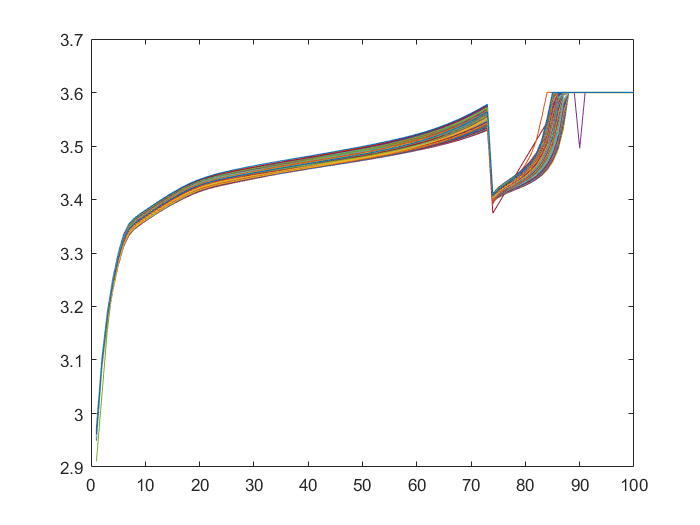

    figure
    plot(Vc')

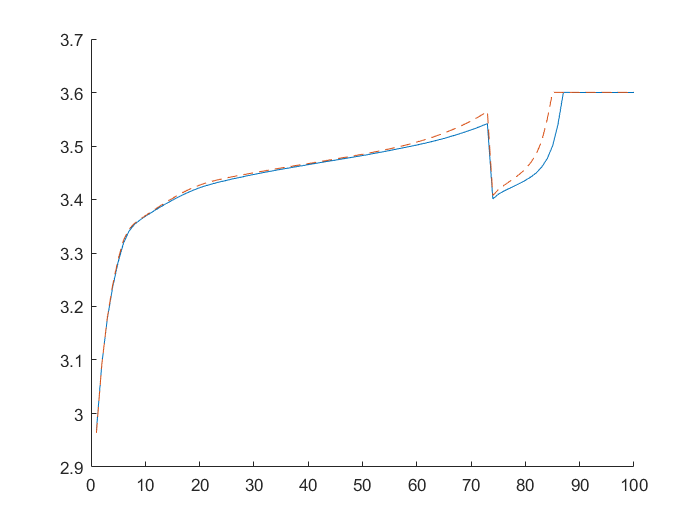

    
    
    Vc_start = Vc(1,:);
    Vc_end = Vc(end,:);
    figure, hold on 
    plot(Vc_start)
    plot(Vc_end,'--')
    hold off

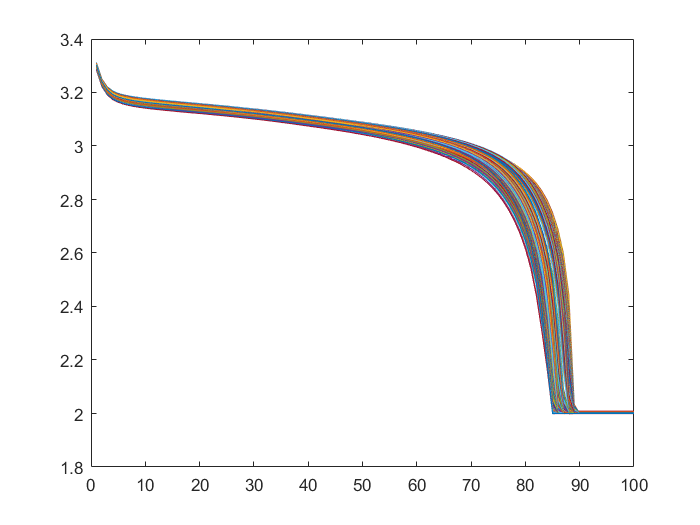

    figure
    plot(Vd')

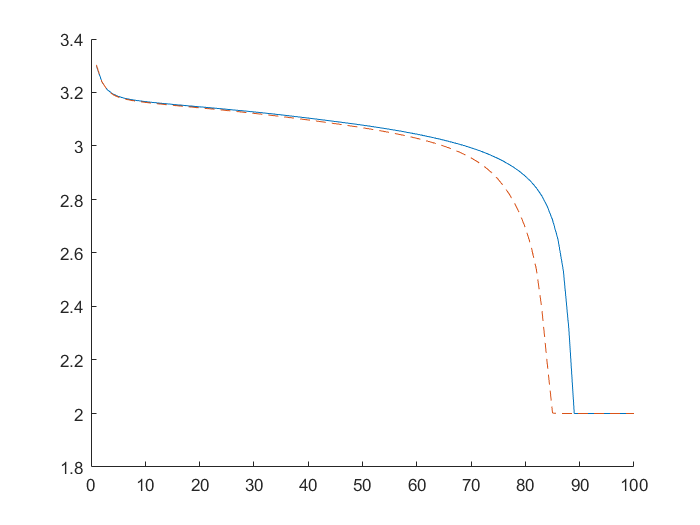


    Vd_start = Vd(1,:);
    Vd_end = Vd(end,:);
    
    figure, hold on 
    plot(Vd_start)
    plot(Vd_end,'--')
    hold off

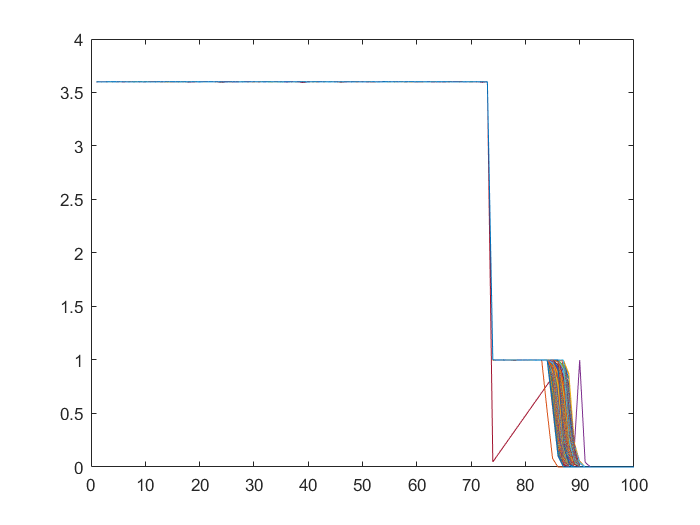

    
    
    figure
    plot(Ic')

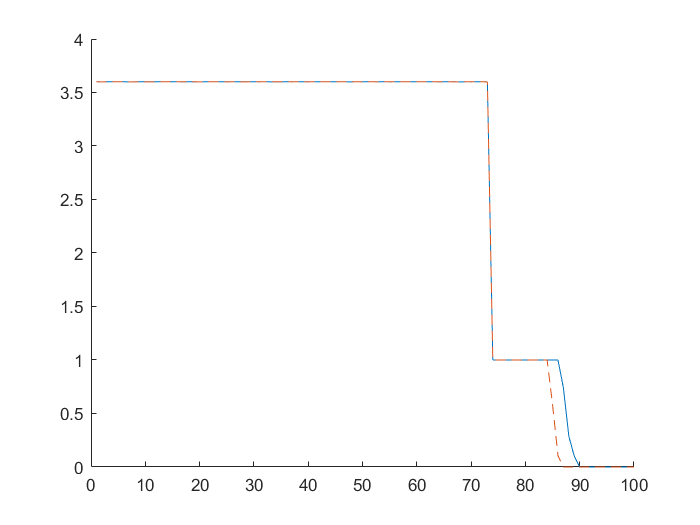

    
    
    Ic_start = Ic(1,:);
    Ic_end = Ic(end,:);
    figure, hold on 
    plot(Ic_start)
    plot(Ic_end,'--')
    hold off

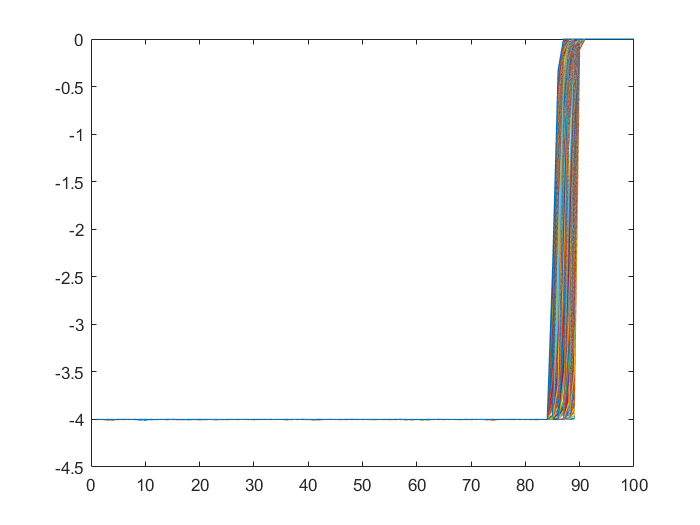

    figure
    plot(Id')

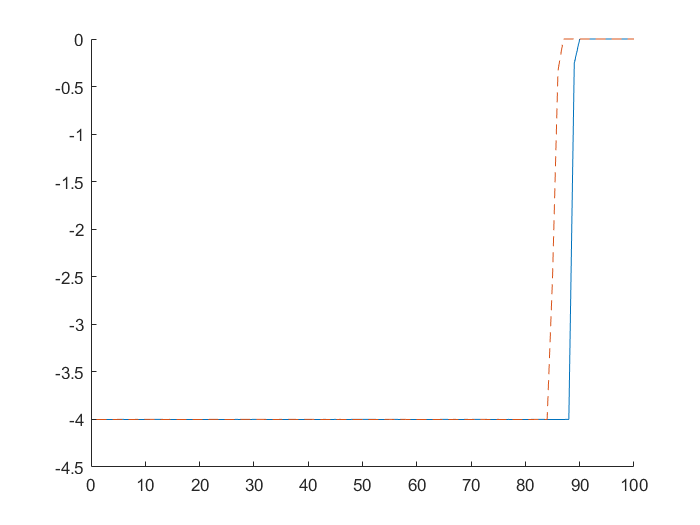


    Id_start = Id(1,:);
    Id_end = Id(end,:);
    
    figure, hold on 
    plot(Id_start)
    plot(Id_end,'--')
    hold off

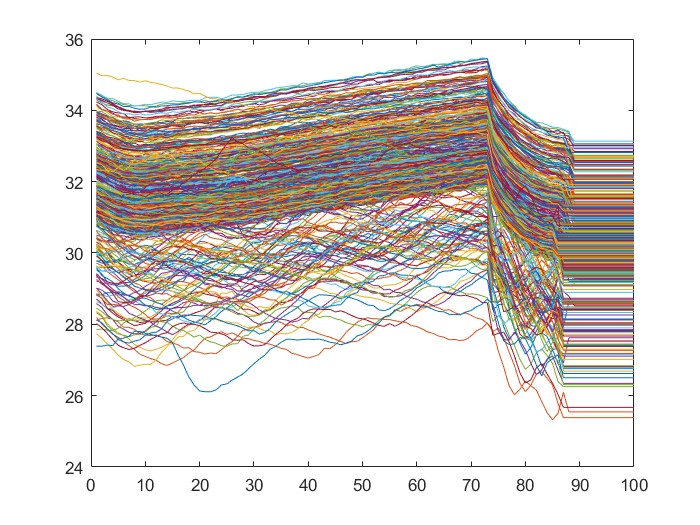

	
    figure
    plot(Tc')

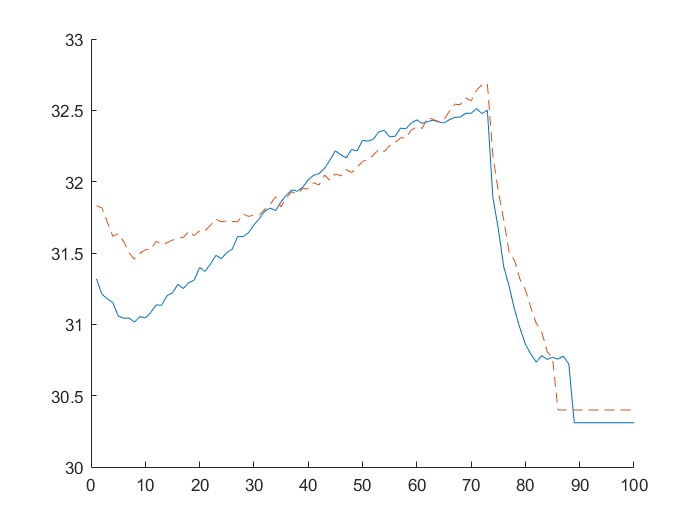

    
    
    Tc_start = Tc(1,:);
    Tc_end = Tc(end,:);
    figure, hold on 
    plot(Tc_start)
    plot(Tc_end,'--')
    hold off

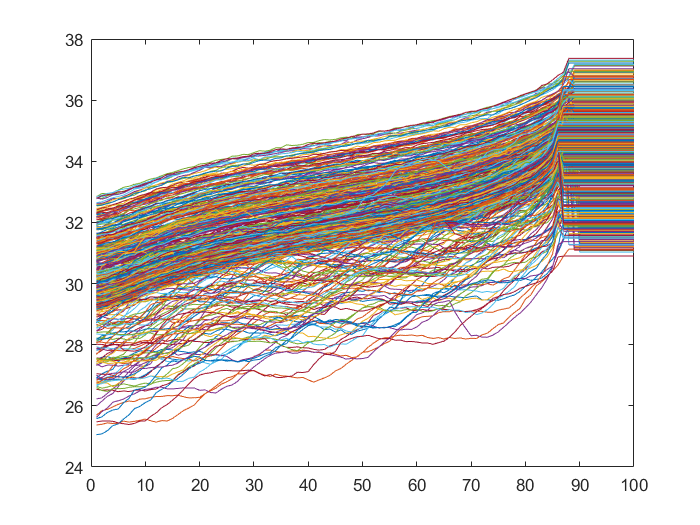

    figure
    plot(Td')

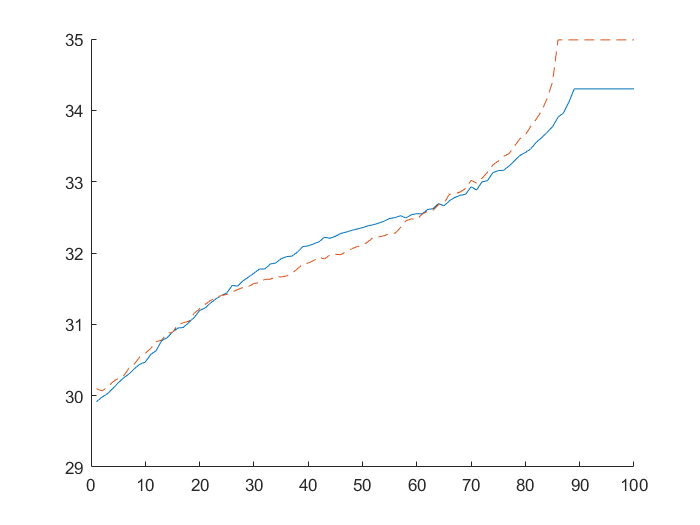


    Td_start = Td(1,:);
    Td_end = Td(end,:);
    
    figure, hold on 
    plot(Td_start)
    plot(Td_end,'--')
    hold off

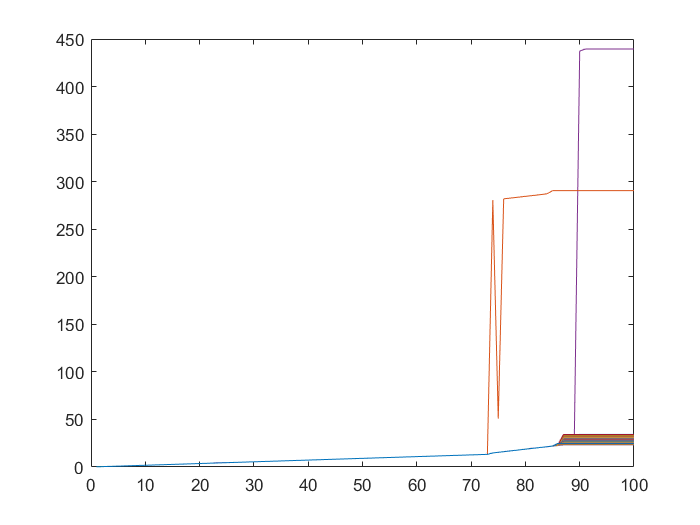

    
	figure
    plot(Time_c')

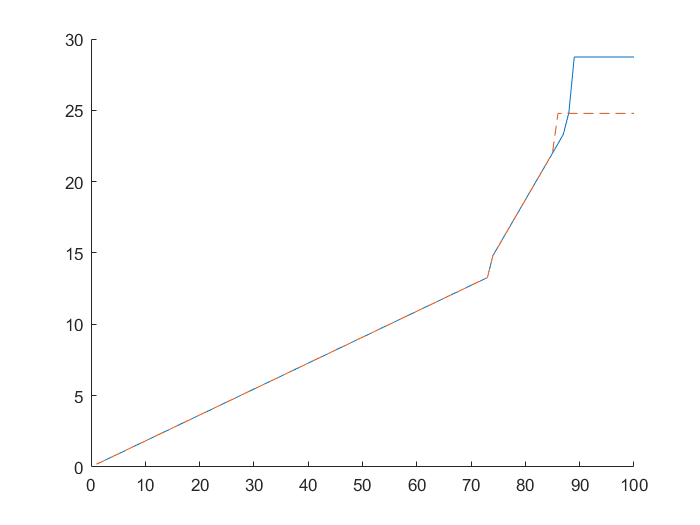

    
    
    Time_c_start = Time_c(1,:);
    Time_c_end = Time_c(end,:);
    figure, hold on 
    plot(Time_c_start)
    plot(Time_c_end,'--')
    hold off

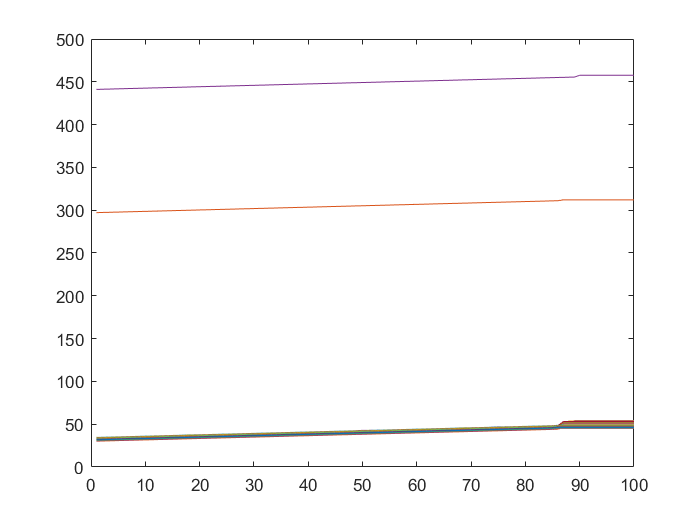

	
    figure
    plot(Time_d')

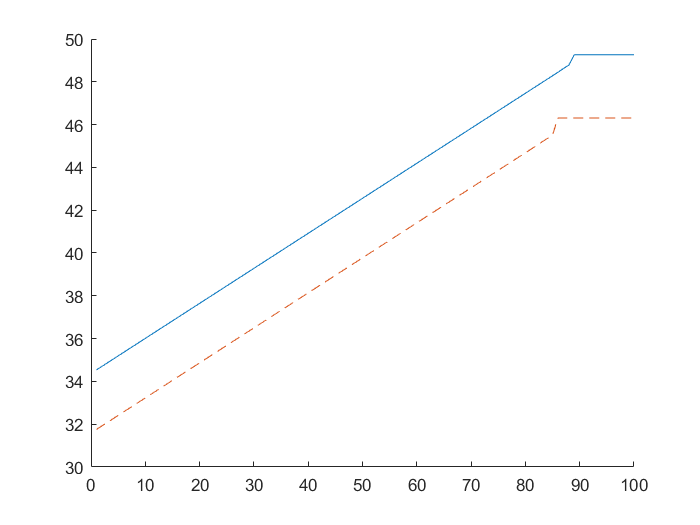


    Time_d_start = Time_d(1,:);
    Time_d_end = Time_d(end,:);
    
    figure, hold on 
    plot(Time_d_start)
    plot(Time_d_end,'--')
    hold off

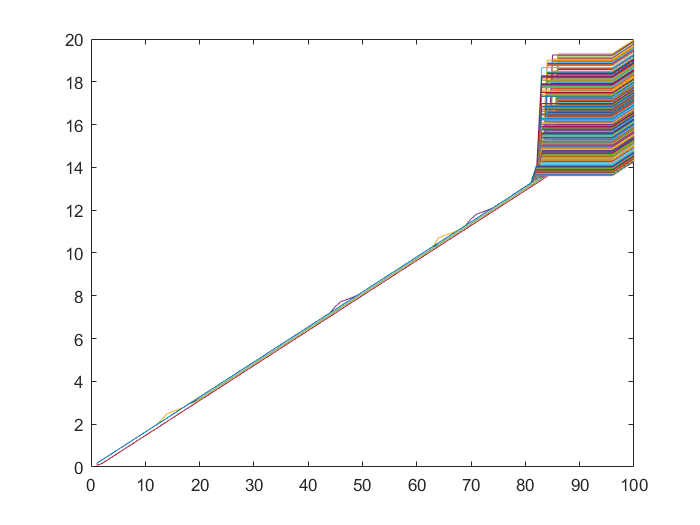

figure
plot(Time_d1')

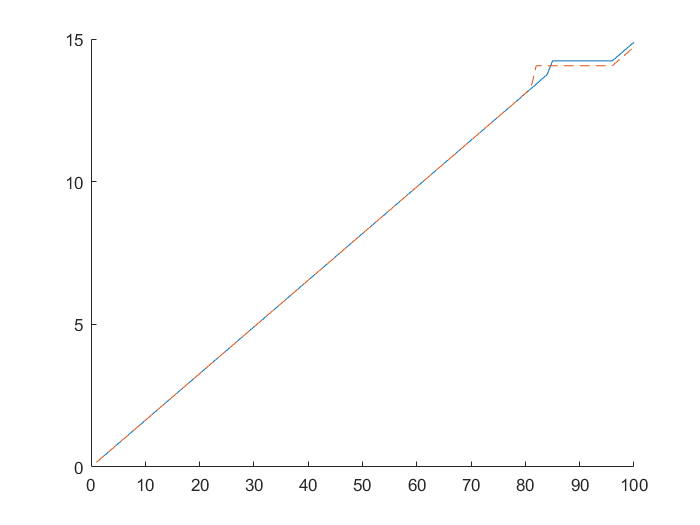


Time_d1_start = Time_d1(1,:);
Time_d1_end = Time_d1(end,:);

figure, hold on 
plot(Time_d1_start)
plot(Time_d1_end,'--')
hold off

new_index = 1;
ryan4_battery_dataset_raw = zeros();
% 이 코드가 중요함. ryan4_battery_dataset_raw 이 structure를 가짐을 알려주어야 함.
ryan4_battery_dataset_raw = ryan4_extract_feature(1,1,trainData(1));


plot_Vc = ryan4_battery_dataset_raw.Vc(1,:)

plot_Vc =     2.9614    3.0917    3.1744    3.2342    3.2805    3.3162    3.3385    3.3510    3.3592    3.3659    3.3724    3.3786    3.3846    3.3905    3.3961    3.4015    3.4064    3.4111    3.4154    3.4192    3.4226    3.4258    3.4285    3.4309    3.4334    3.4356    3.4379    3.4401    3.4420    3.4441    3.4463    3.4481    3.4501    3.4518    3.4539    3.4556    3.4574    3.4591    3.4607    3.4624    3.4642    3.4658    3.4676    3.4692    3.4707    3.4724    3.4741    3.4759    3.4775    3.4793


plot_Vd = ryan4_battery_dataset_raw.Vd(1,:)

plot_Vd =     3.3015    3.2417    3.2128    3.1973    3.1883    3.1824    3.1782    3.1746    3.1718    3.1693    3.1669    3.1649    3.1629    3.1609    3.1590    3.1571    3.1553    3.1536    3.1517    3.1500    3.1482    3.1465    3.1446    3.1426    3.1408    3.1389    3.1370    3.1350    3.1330    3.1309    3.1290    3.1268    3.1246    3.1225    3.1202    3.1178    3.1154    3.1131    3.1107    3.1082    3.1057    3.1031    3.1007    3.0981    3.0955    3.0929    3.0904    3.0876    3.0849    3.0822


plot_Ic = ryan4_battery_dataset_raw.Ic(1,:)

plot_Ic =     3.6006    3.6000    3.6007    3.5998    3.6002    3.6000    3.6001    3.6000    3.5999    3.6002    3.5998    3.6003    3.5998    3.5998    3.5999    3.6001    3.6000    3.6004    3.6000    3.5996    3.6001    3.5993    3.5997    3.6000    3.6000    3.5999    3.6000    3.5997    3.6002    3.5999    3.6000    3.6001    3.6001    3.5998    3.6005    3.5998    3.5999    3.6000    3.6002    3.6000    3.5986    3.6001    3.6000    3.5998    3.6002    3.6000    3.5999    3.6002    3.6001    3.6002


plot_Id = ryan4_battery_dataset_raw.Id(1,:)

plot_Id =    -3.9994   -3.9998   -4.0001   -3.9997   -4.0001   -4.0000   -3.9996   -4.0002   -3.9996   -4.0000   -3.9998   -3.9998   -3.9986   -3.9998   -3.9997   -3.9999   -3.9998   -4.0001   -4.0001   -4.0005   -3.9998   -4.0001   -3.9997   -4.0000   -4.0000   -3.9997   -4.0001   -3.9999   -4.0000   -4.0000   -4.0000   -3.9998   -4.0004   -3.9999   -4.0003   -4.0003   -4.0000   -4.0004   -3.9997   -4.0001   -4.0001   -4.0000   -3.9999   -4.0000   -4.0000   -4.0003   -3.9993   -3.9999   -3.9998   -4.0000


plot_Tc = ryan4_battery_dataset_raw.Tc(1,:)

plot_Tc =    31.5128   31.3851   31.3264   31.2188   31.1925   31.1319   31.1057   31.0883   31.1052   31.1046   31.1118   31.1885   31.2268   31.2806   31.2942   31.3416   31.3683   31.3818   31.4045   31.4979   31.5139   31.5489   31.5424   31.5477   31.5975   31.6222   31.6886   31.6998   31.7557   31.7526   31.8188   31.8757   31.8896   31.9507   32.0120   32.0467   32.0951   32.0943   32.1217   32.2300   32.2624   32.2854   32.3191   32.3410   32.4391   32.4413   32.4489   32.5016   32.5357   32.5690


plot_Td = ryan4_battery_dataset_raw.Td(1,:)

plot_Td =    29.5938   29.6737   29.7374   29.7769   29.8665   29.9510   30.0257   30.1461   30.2459   30.3182   30.3734   30.4998   30.5604   30.6877   30.7627   30.8632   30.9005   30.9886   31.0254   31.1077   31.1780   31.2434   31.3376   31.3556   31.4359   31.4509   31.5246   31.6365   31.6474   31.7804   31.7973   31.8151   31.8518   31.9481   31.9452   32.0266   32.0649   32.0911   32.1450   32.1958   32.2218   32.2625   32.3346   32.3630   32.3953   32.3810   32.4795   32.5114   32.5785   32.5754


plot_Time_c = ryan4_battery_dataset_raw.Time_c(1,:)

plot_Time_c =     0.1875    0.3673    0.5470    0.7272    0.9078    1.0872    1.2674    1.4477    1.6271    1.8074    1.9875    2.1675    2.3481    2.5276    2.7079    2.8877    3.0673    3.2474    3.4275    3.6075    3.7876    3.9673    4.1482    4.3278    4.5077    4.6875    4.8680    5.0484    5.2278    5.4077    5.5880    5.7678    5.9478    6.1282    6.3079    6.4879    6.6679    6.8477    7.0277    7.2084    7.3883    7.5681    7.7497    7.9284    8.1088    8.2879    8.4684    8.6478    8.8281    9.0081


plot_Time_d = ryan4_battery_dataset_raw.Time_d(1,:)

plot_Time_d =    34.5245   34.6866   34.8483   35.0105   35.1723   35.3345   35.4964   35.6583   35.8206   35.9825   36.1446   36.3064   36.4684   36.6307   36.7927   36.9543   37.1169   37.2786   37.4405   37.6026   37.7647   37.9268   38.0885   38.2508   38.4125   38.5747   38.7376   38.8987   39.0607   39.2229   39.3845   39.5467   39.7089   39.8709   40.0326   40.1951   40.3567   40.5187   40.6813   40.8430   41.0048   41.1670   41.3289   41.4915   41.6531   41.8149   41.9772   42.1394   42.3009   42.4633


plot_Time_d1 = ryan4_battery_dataset_raw.Time_d1(1,:)

plot_Time_d1 =     0.1621    0.3242    0.4862    0.6480    0.8104    0.9723    1.1343    1.2962    1.4582    1.6204    1.7824    1.9441    2.1067    2.2683    2.4303    2.5923    2.7545    2.9166    3.0782    3.2406    3.4023    3.5645    3.7273    3.8885    4.0504    4.2127    4.3743    4.5365    4.6987    4.8607    5.0224    5.1849    5.3465    5.5085    5.6711    5.8328    5.9945    6.1568    6.3186    6.4813    6.6428    6.8047    6.9669    7.1291    7.2907    7.4530    7.6150    7.7769    7.9388    8.1010


plot_discharge_dQdV = ryan4_battery_dataset_raw.discharge_dQdV(1,:)

plot_discharge_dQdV =    -0.0127   -0.0127   -0.0127   -0.0683   -0.1101   -0.1106   -0.1314   -0.1221   -0.1121   -0.1258   -0.1415   -0.0960   -0.1153   -0.1846   -0.1495   -0.1722   -0.2065   -0.2591   -0.3399   -0.4832   -0.8346   -1.9803   -4.7125   -6.4830   -6.2119   -5.4671   -4.9171   -4.6158   -4.2289   -3.5973   -3.0791   -2.6159   -2.2920   -1.9732   -1.7053   -1.4693   -1.2648   -1.0908   -0.9540   -0.8349   -0.7318   -0.6371   -0.5600   -0.4922   -0.4283   -0.3810   -0.3414   -0.3015   -0.2720   -0.2498


plot_Qdlin = ryan4_battery_dataset_raw.Qdlin(1,:)

plot_Qdlin =    -0.0004   -0.0000    0.0002    0.0006    0.0011    0.0016    0.0022    0.0030    0.0039    0.0049    0.0061    0.0075    0.0091    0.0109    0.0130    0.0156    0.0185    0.0223    0.0271    0.0338    0.0445    0.0654    0.1163    0.2059    0.3037    0.3918    0.4679    0.5384    0.6046    0.6626    0.7116    0.7539    0.7905    0.8219    0.8491    0.8725    0.8925    0.9096    0.9241    0.9374    0.9487    0.9584    0.9669    0.9746    0.9811    0.9870    0.9923    0.9968    1.0010    1.0049


plot_Tdlin = ryan4_battery_dataset_raw.Tdlin(1,:)

plot_Tdlin =    29.5859   29.5859   29.5859   29.5859   29.5857   29.5906   29.5941   29.5941   29.5941   29.5974   29.6011   29.6017   29.5943   29.5932   29.6029   29.6177   29.6203   29.6375   29.6826   29.6940   29.7600   29.8997   30.3039   30.9352   31.4386   31.8732   32.1569   32.3850   32.6078   32.7656   32.9152   33.0822   33.2401   33.3898   33.5389   33.6668   33.8072   33.9003   34.0105   34.1214   34.2351   34.2614   34.3793   34.3928   34.5020   34.5520   34.5891   34.6683   34.6892   34.7266


plot_Vdlin = ryan4_battery_dataset_raw.Vdlin

plot_Vdlin =     3.5000
    3.4850
    3.4700
    3.4550
    3.4399
    3.4249
    3.4099
    3.3949
    3.3799
    3.3649


# SOC 측정 함수 테스트 = Ah = Current * Time   

# SOC = cumsum () 

# SOCmax = sum(SOC) 

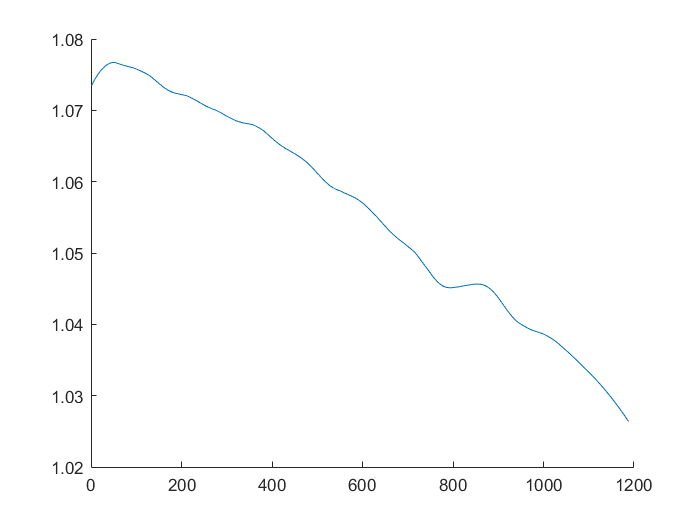


% Ah측정
%ryan4_battery_dataset_raw = ryan4_battery_dataset_raw;
figure, hold on
%for i=1:length(ryan4_battery_dataset_raw.cycle_life)
plot(ryan4_battery_dataset_raw.QDischargeSmooth)
%end
hold off

ryan4_battery_dataset_raw.Time_c(1,1)

ans = 0.1875

ryan4_battery_dataset_raw.Time_c(1,end)

ans = 32.5287

ryan4_battery_dataset_raw.Time_c(2,1)

ans = 0.1970

ryan4_battery_dataset_raw.Time_c(2,end)

ans = 31.8239

ryan4_battery_dataset_raw.Time_c(3,end) 

ans = 31.2480


ryan4_battery_dataset_raw.Time_c(1,end) + ryan4_battery_dataset_raw.Time_c(2,end)

ans = 64.3526


ryan4_battery_dataset_raw.Time_c(1,end) + ryan4_battery_dataset_raw.Time_c(2,end)

ans = 64.3526


ryan4_battery_dataset_raw.Time_c(1,end) + ryan4_battery_dataset_raw.Time_c(2,end) + ryan4_battery_dataset_raw.Time_c(3,end)

ans = 95.6006

ryan4_battery_dataset_raw.Time_c(:,end)

ans =    32.5287
   31.8239
   31.2480
   30.6203
   30.1927
   29.8190
   29.6268
   29.4320
   29.4171
   29.2149



Time_c_end = cumsum(ryan4_battery_dataset_raw.Time_c(:,end))

Time_c_end = 	1.0e+04 *

    0.0033
    0.0064
    0.0096
    0.0126
    0.0156
    0.0186
    0.0216
    0.0245
    0.0275
    0.0304


Time_c_start = cumsum(ryan4_battery_dataset_raw.Time_c(:,end)) - ryan4_battery_dataset_raw.Time_c(1,end)

Time_c_start = 	1.0e+04 *

         0
    0.0032
    0.0063
    0.0094
    0.0124
    0.0154
    0.0183
    0.0213
    0.0242
    0.0271



index = 1

index = 1

cycle1_time = ryan4_battery_dataset_raw.Time_c(index,:)

cycle1_time =     0.1875    0.3673    0.5470    0.7272    0.9078    1.0872    1.2674    1.4477    1.6271    1.8074    1.9875    2.1675    2.3481    2.5276    2.7079    2.8877    3.0673    3.2474    3.4275    3.6075    3.7876    3.9673    4.1482    4.3278    4.5077    4.6875    4.8680    5.0484    5.2278    5.4077    5.5880    5.7678    5.9478    6.1282    6.3079    6.4879    6.6679    6.8477    7.0277    7.2084    7.3883    7.5681    7.7497    7.9284    8.1088    8.2879    8.4684    8.6478    8.8281    9.0081


cycle1_time_diff = diff(cycle1_time);
%cycle1_time_diff = [0  cycle1_time_diff]
cycle1_time_diff = [ cycle1_time_diff cycle1_time_diff(end)]

cycle1_time_diff =     0.1798    0.1797    0.1802    0.1805    0.1794    0.1802    0.1803    0.1794    0.1803    0.1801    0.1800    0.1806    0.1795    0.1802    0.1798    0.1797    0.1801    0.1801    0.1801    0.1801    0.1797    0.1809    0.1795    0.1800    0.1798    0.1805    0.1803    0.1794    0.1799    0.1803    0.1798    0.1800    0.1804    0.1797    0.1801    0.1800    0.1798    0.1801    0.1806    0.1799    0.1798    0.1816    0.1786    0.1804    0.1791    0.1805    0.1794    0.1803    0.1800    0.1801


offset = 1.0283

offset = 1.0283

calcAh = ryan4_battery_dataset_raw.Ic(index,:) .* cycle1_time_diff .*offset

calcAh =     0.6657    0.6651    0.6674    0.6682    0.6643    0.6671    0.6675    0.6640    0.6674    0.6669    0.6665    0.6685    0.6644    0.6672    0.6656    0.6651    0.6666    0.6667    0.6665    0.6666    0.6651    0.6697    0.6645    0.6662    0.6656    0.6682    0.6676    0.6641    0.6661    0.6673    0.6656    0.6665    0.6678    0.6650    0.6667    0.6662    0.6655    0.6666    0.6687    0.6660    0.6654    0.6723    0.6612    0.6678    0.6631    0.6684    0.6640    0.6674    0.6663    0.6667



calcAhSum = sum(calcAh) + calcAh(end) % minute

calcAhSum = 63.1400

calcAhSumHour = calcAhSum / 60

calcAhSumHour = 1.0523

ryan4_battery_dataset_raw.QCharge(index)

ans = 1.0710


[SOC_c, soc_max_c] = ryan4_calc_SOC_cali(ryan4_battery_dataset_raw.Ic(index,:), ryan4_battery_dataset_raw.Time_c(index,:), false)

SOC_c =     0.0113    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0109    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0109    0.0107    0.0108    0.0107    0.0108    0.0108    0.0108    0.0108


soc_max_c = 0.9737

ryan4_battery_dataset_raw.QCharge(index)

ans = 1.0710

ryan4_battery_dataset_raw.QCharge(index) - soc_max_c

ans = 0.0974

ryan4_battery_dataset_raw.QCharge(index) / soc_max_c

ans = 1.1000



[SOC_d, soc_max_d] = ryan4_calc_SOC_cali(ryan4_battery_dataset_raw.Id(index,:), ryan4_battery_dataset_raw.Time_d(index,:), true)

SOC_d =     2.3013    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0109    0.0107    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108    0.0108


soc_max_d = 3.2511

ryan4_battery_dataset_raw.QDischarge(index)

ans = 1.0707

ryan4_battery_dataset_raw.QDischarge(index) - soc_max_d

ans = -2.1804

ryan4_battery_dataset_raw.QDischarge(index) / soc_max_d

ans = 0.3293

[SOC_c, soc_max_c] = ryan4_calc_SOC_with_offset(ryan4_battery_dataset_raw.Ic(index,:), ryan4_battery_dataset_raw.Time_c(index,:), false, 1.1004, 0.3292)

SOC_c =     0.0124    0.0119    0.0119    0.0119    0.0119    0.0118    0.0119    0.0119    0.0118    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0118    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0120    0.0118    0.0119    0.0118    0.0119    0.0118    0.0119    0.0119


soc_max_c = 1.0714

[SOC_d, soc_max_d] = ryan4_calc_SOC_with_offset(ryan4_battery_dataset_raw.Id(index,:), ryan4_battery_dataset_raw.Time_d(index,:), true, 1.1004, 0.3292)

SOC_d =     0.7576    0.0036    0.0035    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0035    0.0036    0.0035    0.0036    0.0036    0.0036    0.0036    0.0035    0.0036    0.0035    0.0036    0.0036    0.0035    0.0036    0.0036    0.0035    0.0036    0.0036    0.0036    0.0035    0.0036    0.0035    0.0036    0.0036    0.0035    0.0036    0.0036    0.0036    0.0036    0.0035    0.0036    0.0036    0.0036    0.0035    0.0036


soc_max_d = 1.0703

%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%
modeDischarge = false;
modeCharge = true;

[Ah_ds_c, Ah_c, SOC_c, SOH_c] = ryan4_calc_SOC_new(ryan4_battery_dataset_raw.Ic(index,:), ryan4_battery_dataset_raw.Time_c(index,:), ryan4_battery_dataset_raw.QChargeSmooth(index))

Ah_ds_c =     0.0124    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0120    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0120    0.0118    0.0119    0.0118    0.0119    0.0119    0.0119    0.0119


Ah_c =     0.0124    0.0243    0.0362    0.0481    0.0600    0.0719    0.0838    0.0957    0.1076    0.1195    0.1314    0.1433    0.1553    0.1671    0.1791    0.1910    0.2028    0.2147    0.2267    0.2386    0.2505    0.2623    0.2743    0.2862    0.2981    0.3100    0.3219    0.3338    0.3457    0.3576    0.3695    0.3814    0.3933    0.4052    0.4171    0.4290    0.4409    0.4528    0.4647    0.4767    0.4886    0.5004    0.5125    0.5243    0.5362    0.5480    0.5600    0.5718    0.5838    0.5957


SOC_c =     0.0116    0.0226    0.0337    0.0448    0.0559    0.0670    0.0781    0.0892    0.1003    0.1114    0.1225    0.1336    0.1447    0.1558    0.1669    0.1779    0.1890    0.2001    0.2112    0.2223    0.2334    0.2445    0.2556    0.2667    0.2778    0.2889    0.3000    0.3111    0.3221    0.3332    0.3443    0.3554    0.3665    0.3776    0.3887    0.3998    0.4109    0.4220    0.4331    0.4442    0.4553    0.4664    0.4776    0.4886    0.4997    0.5107    0.5218    0.5329    0.5440    0.5551


SOH_c = 0.9755

Ah_c(end) 

ans = 1.0731

SOC_c(end)

ans = 1.0000


[Ah_ds_d, Ah_d, SOC_d, SOH_d] = ryan4_calc_SOC_new(ryan4_battery_dataset_raw.Id(index,:), ryan4_battery_dataset_raw.Time_d(index,:), ryan4_battery_dataset_raw.QDischargeSmooth(index))

Ah_ds_d =     0.7598    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0035    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036


Ah_d =     0.7598    0.7634    0.7669    0.7705    0.7741    0.7776    0.7812    0.7848    0.7883    0.7919    0.7955    0.7990    0.8026    0.8062    0.8097    0.8133    0.8169    0.8204    0.8240    0.8276    0.8311    0.8347    0.8383    0.8418    0.8454    0.8490    0.8526    0.8561    0.8597    0.8632    0.8668    0.8704    0.8739    0.8775    0.8811    0.8846    0.8882    0.8918    0.8953    0.8989    0.9025    0.9060    0.9096    0.9132    0.9167    0.9203    0.9239    0.9274    0.9310    0.9346


SOC_d =     0.7078    0.7112    0.7145    0.7178    0.7211    0.7245    0.7278    0.7311    0.7344    0.7377    0.7411    0.7444    0.7477    0.7510    0.7544    0.7577    0.7610    0.7643    0.7676    0.7710    0.7743    0.7776    0.7809    0.7843    0.7876    0.7909    0.7942    0.7975    0.8009    0.8042    0.8075    0.8108    0.8142    0.8175    0.8208    0.8241    0.8274    0.8308    0.8341    0.8374    0.8407    0.8441    0.8474    0.8507    0.8540    0.8573    0.8607    0.8640    0.8673    0.8706


SOH_d = 0.9758

Ah_d(end)

ans = 1.0734

SOC_d(end)

ans = 1.0000






x_axis_ah = linspace(0,1.2,102)

x_axis_ah =          0    0.0119    0.0238    0.0356    0.0475    0.0594    0.0713    0.0832    0.0950    0.1069    0.1188    0.1307    0.1426    0.1545    0.1663    0.1782    0.1901    0.2020    0.2139    0.2257    0.2376    0.2495    0.2614    0.2733    0.2851    0.2970    0.3089    0.3208    0.3327    0.3446    0.3564    0.3683    0.3802    0.3921    0.4040    0.4158    0.4277    0.4396    0.4515    0.4634    0.4752    0.4871    0.4990    0.5109    0.5228    0.5347    0.5465    0.5584    0.5703    0.5822


x_axis_ah = x_axis_ah(2:end-1)

x_axis_ah =     0.0119    0.0238    0.0356    0.0475    0.0594    0.0713    0.0832    0.0950    0.1069    0.1188    0.1307    0.1426    0.1545    0.1663    0.1782    0.1901    0.2020    0.2139    0.2257    0.2376    0.2495    0.2614    0.2733    0.2851    0.2970    0.3089    0.3208    0.3327    0.3446    0.3564    0.3683    0.3802    0.3921    0.4040    0.4158    0.4277    0.4396    0.4515    0.4634    0.4752    0.4871    0.4990    0.5109    0.5228    0.5347    0.5465    0.5584    0.5703    0.5822    0.5941



x_axis_vdlin = linspace(2,3.5,100)

x_axis_vdlin =     2.0000    2.0152    2.0303    2.0455    2.0606    2.0758    2.0909    2.1061    2.1212    2.1364    2.1515    2.1667    2.1818    2.1970    2.2121    2.2273    2.2424    2.2576    2.2727    2.2879    2.3030    2.3182    2.3333    2.3485    2.3636    2.3788    2.3939    2.4091    2.4242    2.4394    2.4545    2.4697    2.4848    2.5000    2.5152    2.5303    2.5455    2.5606    2.5758    2.5909    2.6061    2.6212    2.6364    2.6515    2.6667    2.6818    2.6970    2.7121    2.7273    2.7424


# 기본 데이타 분석

i=3 

i = 3

policy = trainData(i).policy 

policy = '3_6C-80PER_3_6C'

policy_readable = trainData(i).policy_readable 

policy_readable = '3.6C(80%)-3.6C'

channel_id = trainData(i).channel_id

channel_id = "3"

cycle_life = trainData(i).cycle_life

cycle_life = 1177

chargetime = trainData(i).summary.chargetime

chargetime =          0
   13.3414
   13.3415
   13.4258
   13.3412
   13.3413
   13.4257
   13.4256
   13.3414
   13.3413


cycle = trainData(i).summary.cycle

cycle =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


IR = trainData(i).summary.IR

IR =          0
    0.0169
    0.0168
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167


QCharge = trainData(i).summary.QCharge

QCharge =          0
    1.0798
    1.0811
    1.0819
    1.0825
    1.0828
    1.0831
    1.0834
    1.0835
    1.0836


QDischarge = trainData(i).summary.QDischarge

QDischarge =          0
    1.0799
    1.0813
    1.0822
    1.0827
    1.0830
    1.0833
    1.0837
    1.0837
    1.0838


Vdlin = trainData(i).Vdlin

Vdlin =     3.5000
    3.4985
    3.4970
    3.4955
    3.4940
    3.4925
    3.4910
    3.4895
    3.4880
    3.4865


trainData(i).Vdlin

ans =     3.5000
    3.4985
    3.4970
    3.4955
    3.4940
    3.4925
    3.4910
    3.4895
    3.4880
    3.4865


cycleNum = 2

cycleNum = 2

cycleNum1 = 100

cycleNum1 = 100

size ( trainData(3).cycles(2).t )

ans =         1124           1


trainData(3).cycles(2).t 

ans =          0
    0.0025
    0.0029
    0.0032
    0.0036
    0.0040
    0.0043
    0.0045
    0.0048
    0.0051


% trainData(3).cycles(1).t(2:3,:)
 
trainData(3).cycles(cycleNum).t 

ans =          0
    0.0025
    0.0029
    0.0032
    0.0036
    0.0040
    0.0043
    0.0045
    0.0048
    0.0051


# 그래프로 확인

# 전체 전류 ( 충/방전 )

#### 테스트 환경 설정

test_bat = 6 ;
cycle_div = 500;

# 측정 포인트 대비 시간 - 1:1 이 아니다.

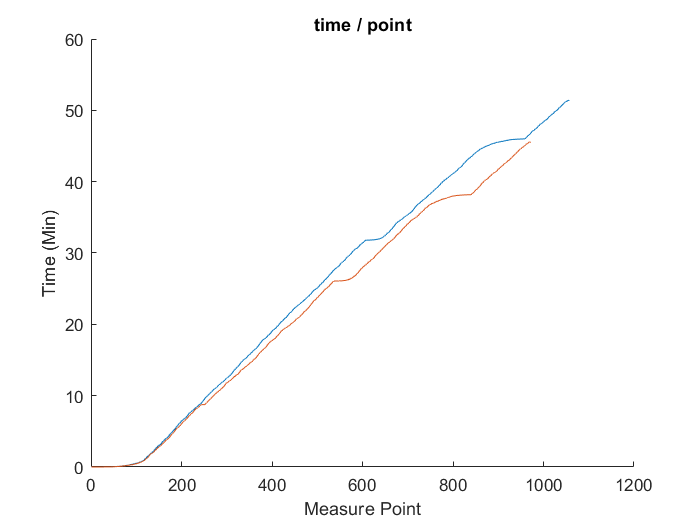

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t)
    end
end
hold off , xlabel 'Measure Point' , ylabel 'Time (Min)' , title 'time / point'

#### Charge Q / Meature Point

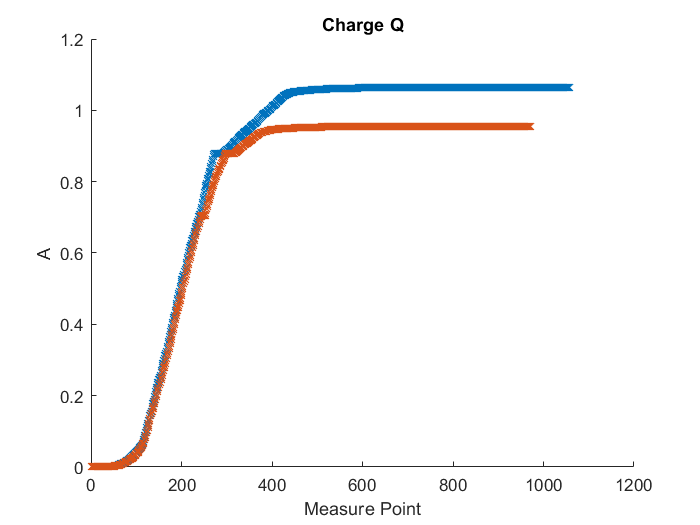


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,'x')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Q'

#### Charge Q / Time

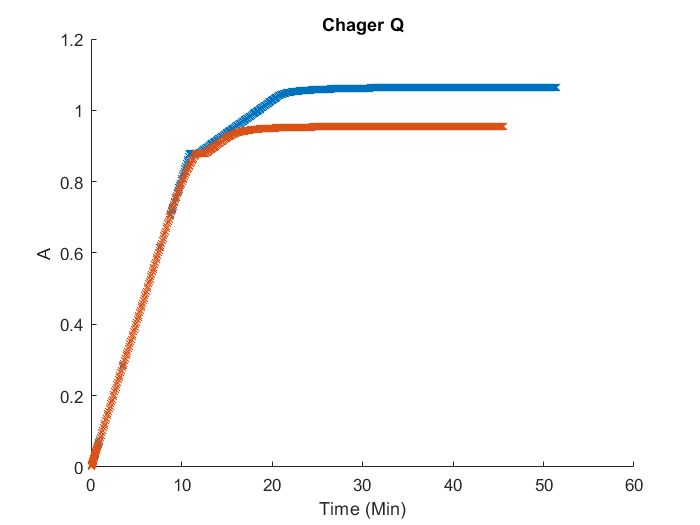

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Chager Q'

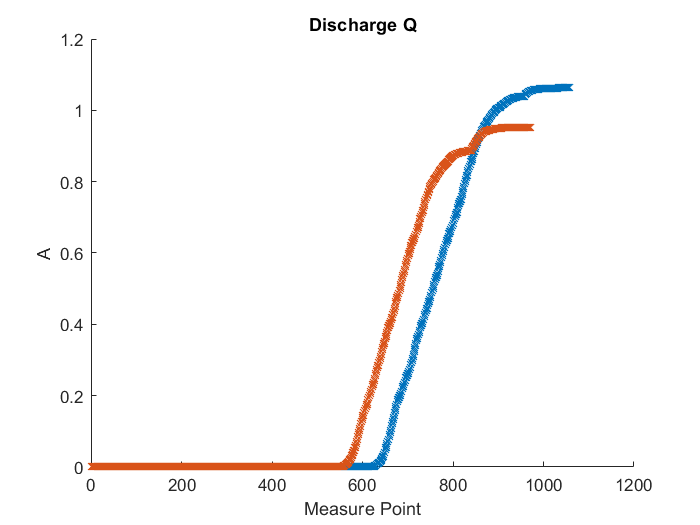

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,'x')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Discharge Q'

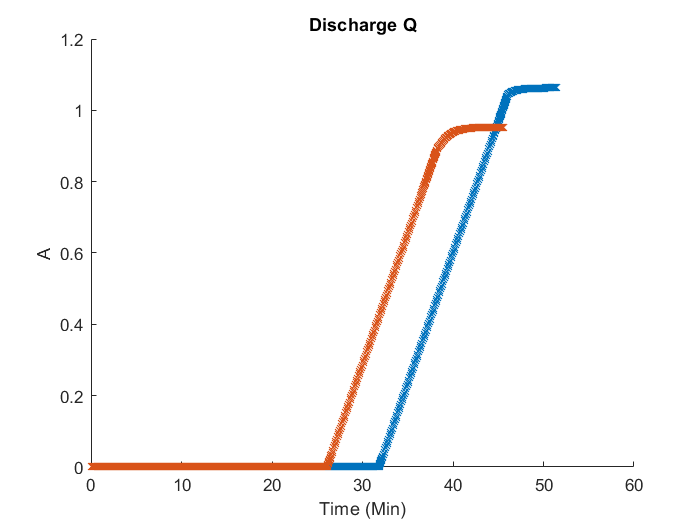


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'x')
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Discharge Q'

#### Qc 와 Qd 를 보면 이를 통해 충전 사이클과 방전 사이클을 확인할 수 있다.

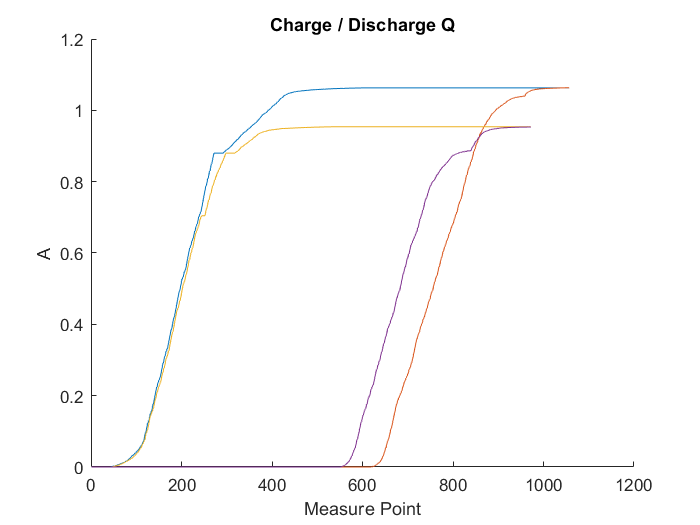

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc)
        plot(trainData(test_bat).cycles(i).Qd,'-')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge / Discharge Q'

# 충전 전류 분석

#### I는 충방전 전체 사이클에 대한 정보이다.

#### 충전시와 방전시로 분리하자.

#### Measure Point 는 Cycle 이 증가할 수로 줄어든다.

#### Measure Time 는 Cycle 이 증가할 수로 줄어든다.

#### x 축의 마지막 값이 cycle 에 따라 달라지면 이를 이용하기 힘들다.

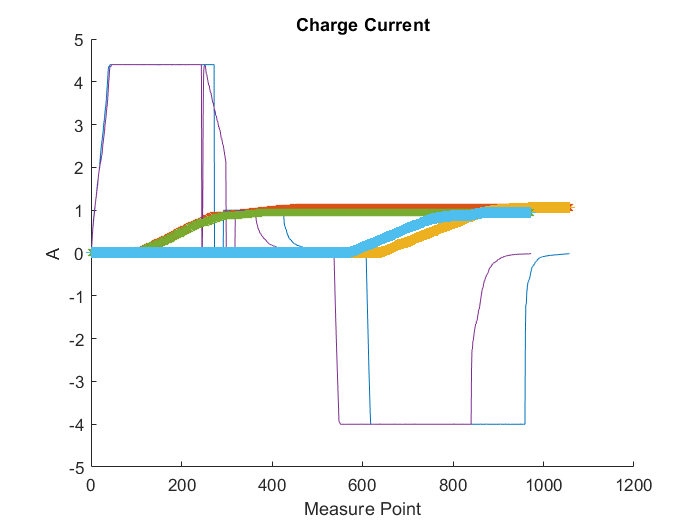

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).I)
        plot(trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).Qd,'+')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Current'

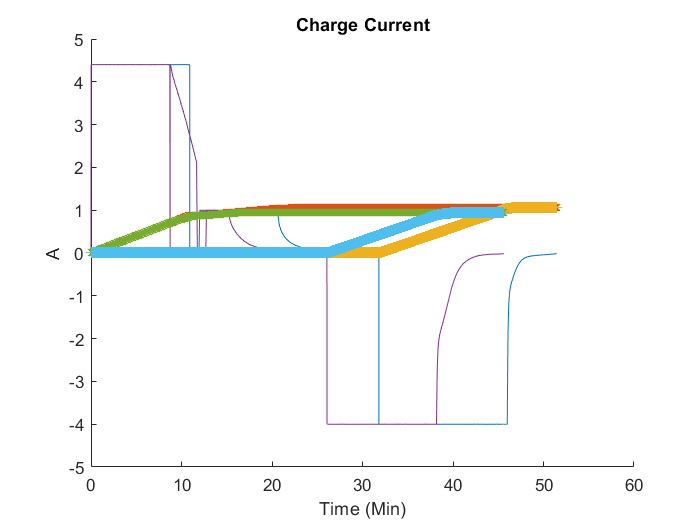

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).I)
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'+')        
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Charge Current'

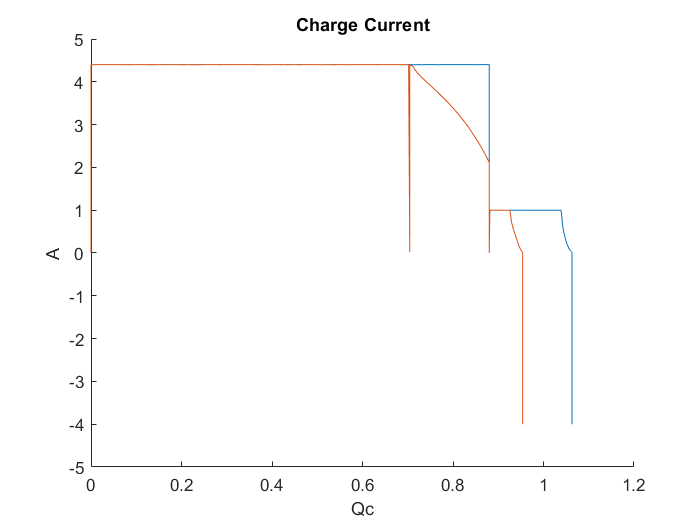


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,trainData(test_bat).cycles(i).I)     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current'

#### 아래 그래프에서 이상치가 있어 smooth함수를 사용했지만 큰 개선은 없다.

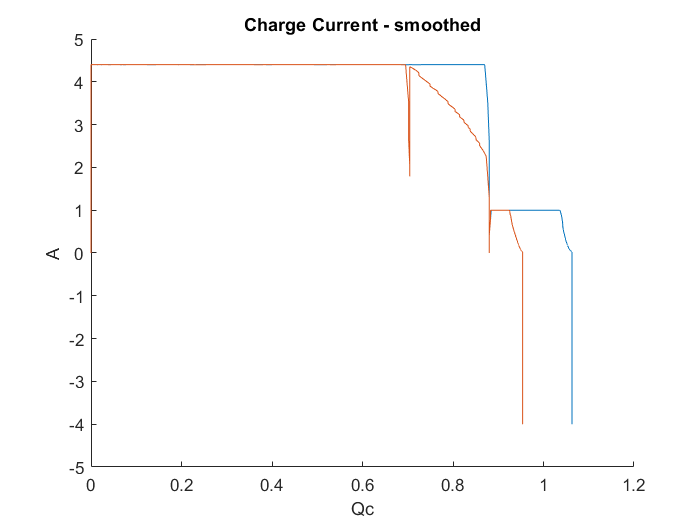

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,smooth(trainData(test_bat).cycles(i).I))     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current - smoothed'

#### x축의 단위를 용량기준으로 0 부터 1.2까지의 100개의 포인트로 전환하자. 

#### 변환에서 중요한 것은 Qc에 해당하는 I를 구하는 것이다.   

#### uniq함수에서  first 인자를 사용하면 동일한 용량값 여려개 있을때 첫번째를 선정하고

#### last 인자를 사용하면 동일한 용량값 여러개 있을대 제일 마지막 것을 선정한다.

#### 아래 그림에서 Ic를 얻기 위해서는 동일 Qc 의 첫번째 것을 선택해야 하고

#### Id를 얻기위해서는 Qd의 마지막 것을 선택해야 한다.

#### 그러나 실험결과 first 든 last 든 큰 차이가 없다.

#### .

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc)
        plot(trainData(test_bat).cycles(i).Qd,'-')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge / Discharge Q'

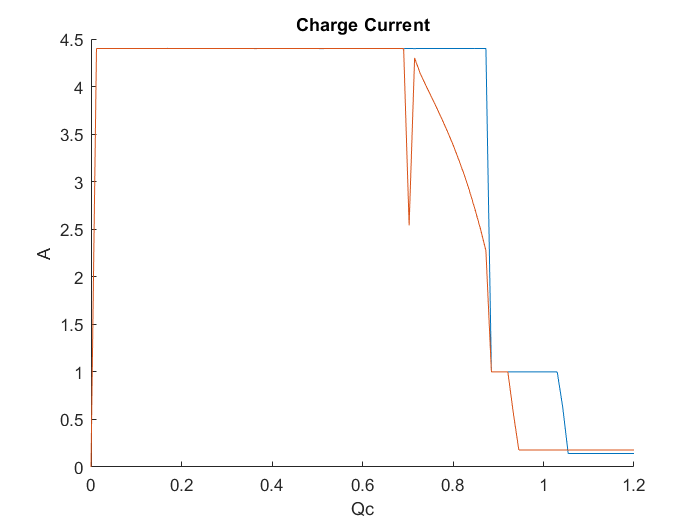


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
    [x_c, index] = unique(trainData(test_bat).cycles(i).Qc,"first");
    %[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
    y_c = trainData(test_bat).cycles(i).I(index);
    new_x_c = linspace(0,1.2,100);
    new_y_c = interp1(x_c,y_c,new_x_c,'linear');
    new_y_c = fillmissing(new_y_c,'nearest');
    plot(new_x_c,new_y_c);  
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current'


length(new_x_c)

ans = 100

index_first = index

index_first =      1
     2
    25
    48
    53
    57
    60
    64
    66
    69


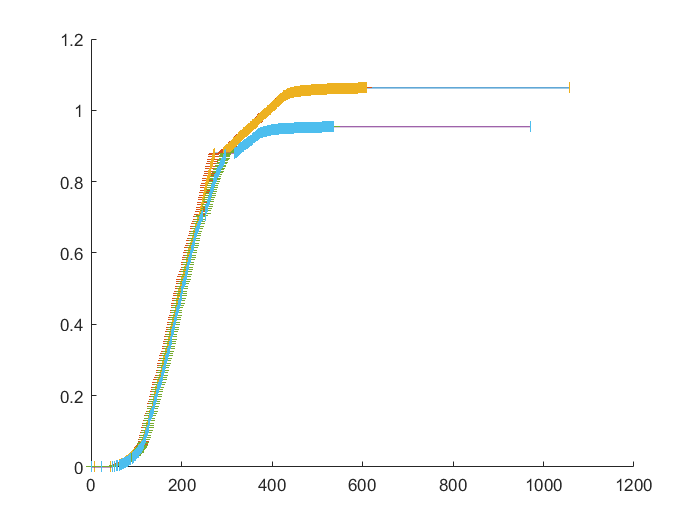

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
    [x_c_first, index_first] = unique(trainData(test_bat).cycles(i).Qc,"first");
    [x_c_last, index_last] = unique(trainData(test_bat).cycles(i).Qc,"last");
    plot(trainData(test_bat).cycles(i).Qc)
    plot(index_first,x_c_first,'_')
    plot(index_last,x_c_last,'|')
    end
end
hold off


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
    [x_c, index] = unique(trainData(test_bat).cycles(i).Qc,"last");
    %[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
    y_c = trainData(test_bat).cycles(i).I(index);
    new_x_c = linspace(0,1.2,100);
    new_y_c = interp1(x_c,y_c,new_x_c,'linear');
    new_y_c = fillmissing(new_y_c,'nearest');
    plot(new_x_c,new_y_c);  
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current'

length(new_x_c)

ans = 100

index_last = index

index_last =      1
    24
    47
    52
    56
    59
    63
    65
    68
    70



indexs = [index_first index_last]

indexs =      1     1
     2    24
    25    47
    48    52
    53    56
    57    59
    60    63
    64    65
    66    68
    69    70


indexs_gap = index_last - index_first

indexs_gap =      0
    22
    22
     4
     3
     2
     3
     1
     2
     1


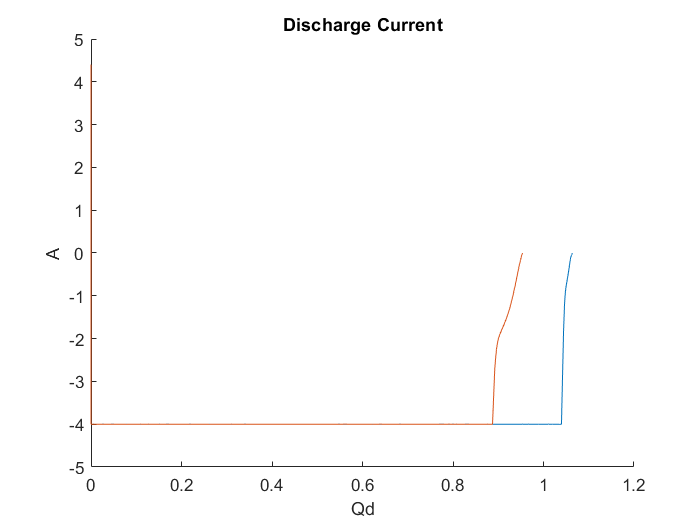


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,trainData(test_bat).cycles(i).I)     
    end
end
hold off , xlabel 'Qd' , ylabel 'A' , title 'Discharge Current'

# 테스트 한것들 

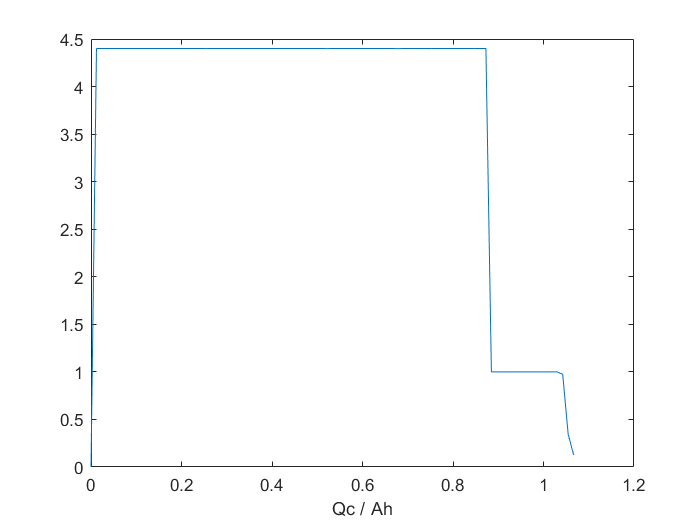


[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
y_c = trainData(test_bat).cycles(cycleNum).I(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("Qc / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


idxNon = isnan(new_y_c )

idxNon = 1×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =          0    4.4001    4.4000    4.4001    4.4001    4.3999    4.4000    4.4001    4.3998    4.4001    4.4001    4.4001    4.4000    4.4000    4.3998    4.3997    4.3999    4.4000    4.3998    4.4003    4.3997    4.3994    4.3999    4.3999    4.4001    4.4000    4.3997    4.3998    4.3998    4.4002    4.4001    4.4000    4.4000    4.4001    4.3999    4.3998    4.3999    4.4002    4.3999    4.3999    4.4001    4.4000    4.4004    4.3990    4.4002    4.4002    4.4001    4.4000    4.3999    4.3999


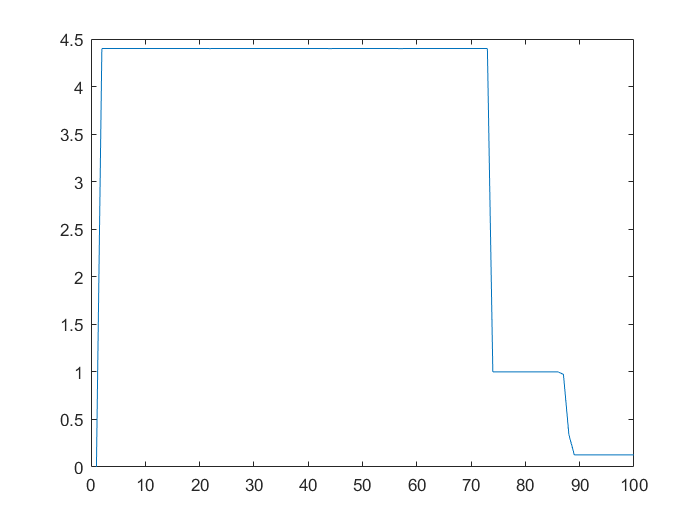

plot(new_y_c_fix)

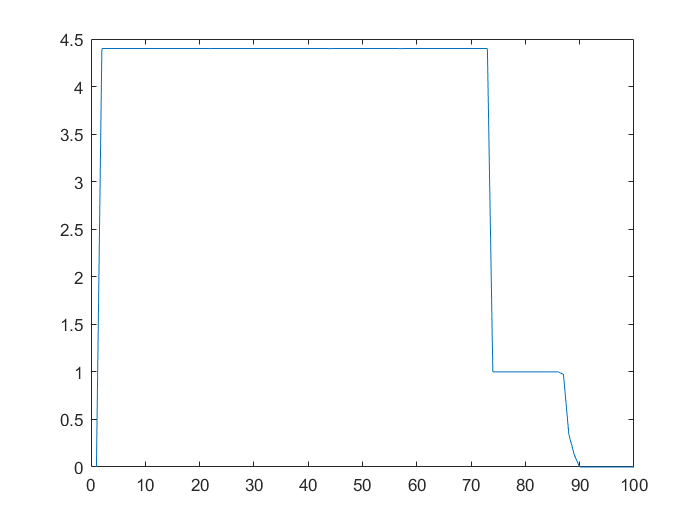

% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

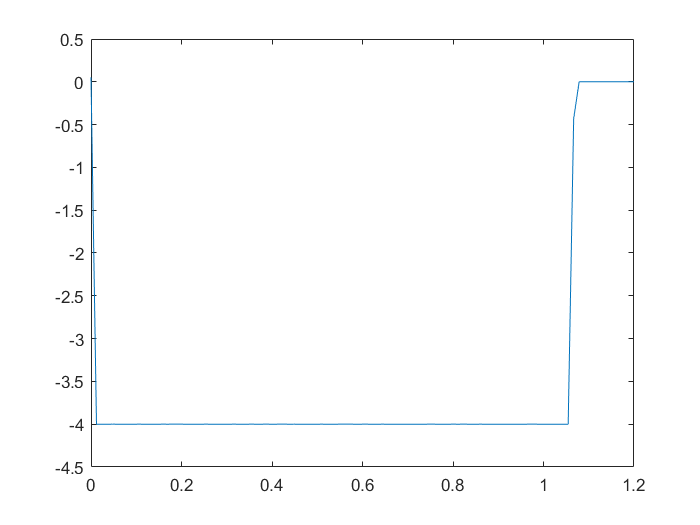

%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd,"last");

y_d = trainData(test_bat).cycles(cycleNum).I(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

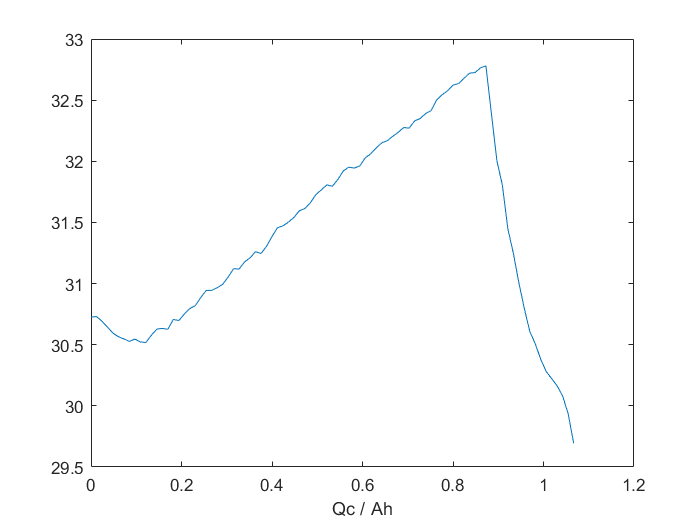

[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
y_c = trainData(test_bat).cycles(cycleNum).T(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("Qc / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix = 1×100
   30.7258   30.7306   30.6922   30.6439   30.5951   30.5652   30.5472   30.5274   30.5463   30.5230   30.5182   30.5774   30.6280   30.6334   30.6259   30.7066   30.6976   30.7497   30.7953   30.8187   30.8856   30.9434   30.9449   30.9660   30.9935   31.0532   31.1220   31.1186   31.1772   31.2099


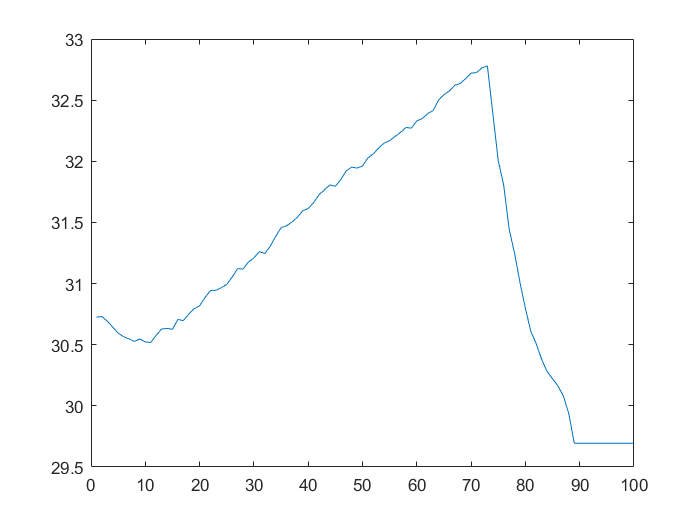

plot(new_y_c_fix)

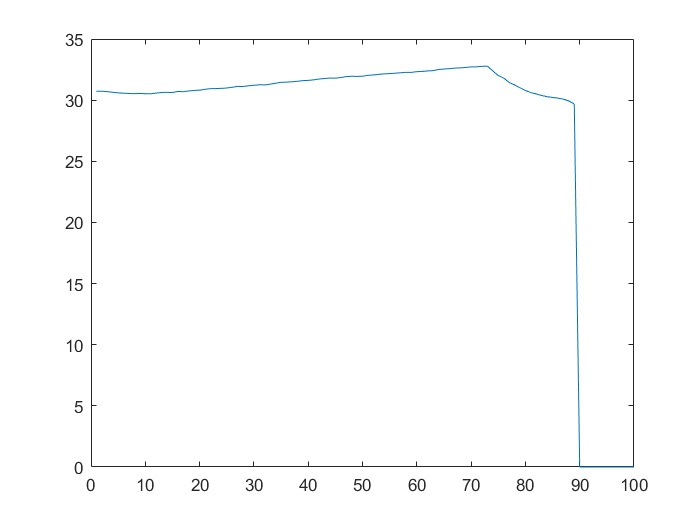

% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

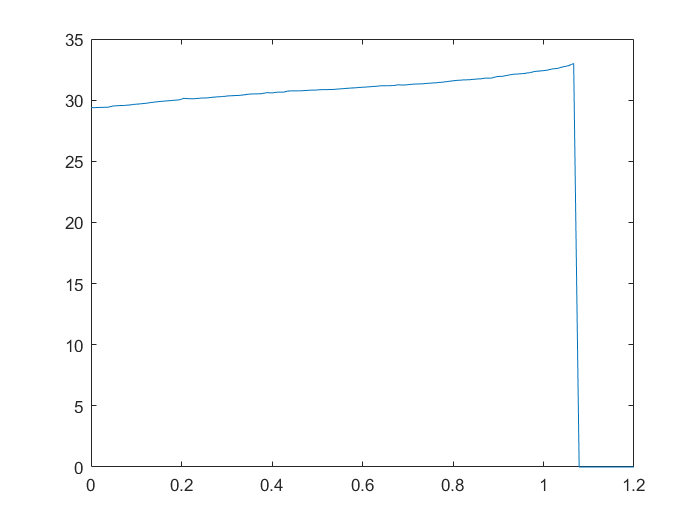

%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd,"last");

y_d = trainData(test_bat).cycles(cycleNum).T(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

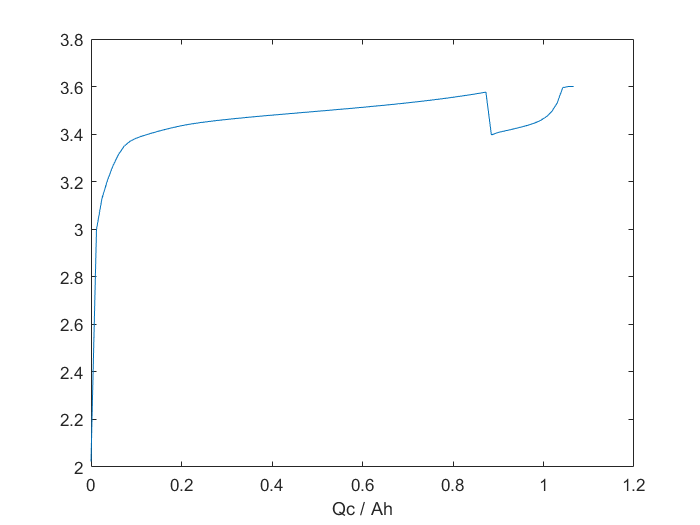

[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
y_c = trainData(test_bat).cycles(cycleNum).V(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("Qc / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
% https://kr.mathworks.com/matlabcentral/answers/29481-last-non-nan-observation
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix = 1×100
    2.0230    2.9983    3.1292    3.2055    3.2669    3.3139    3.3482    3.3681    3.3802    3.3894    3.3969    3.4037    3.4103    3.4165    3.4224    3.4278    3.4329    3.4375    3.4416    3.4452    3.4486    3.4516    3.4545    3.4573    3.4598    3.4622    3.4646    3.4668    3.4692    3.4714


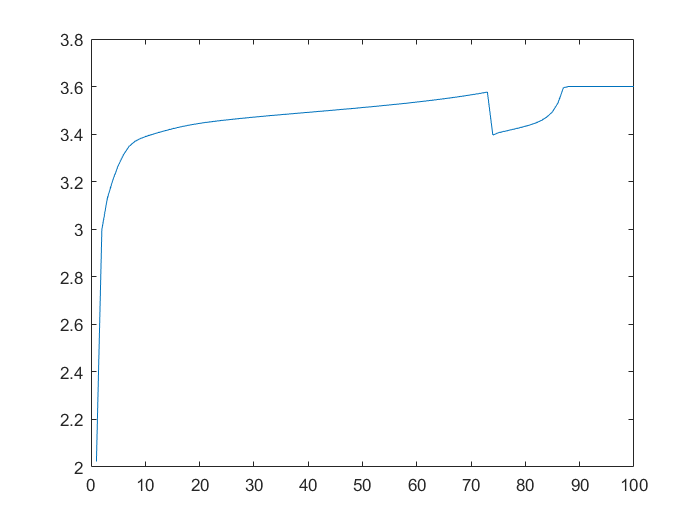

plot(new_y_c_fix)

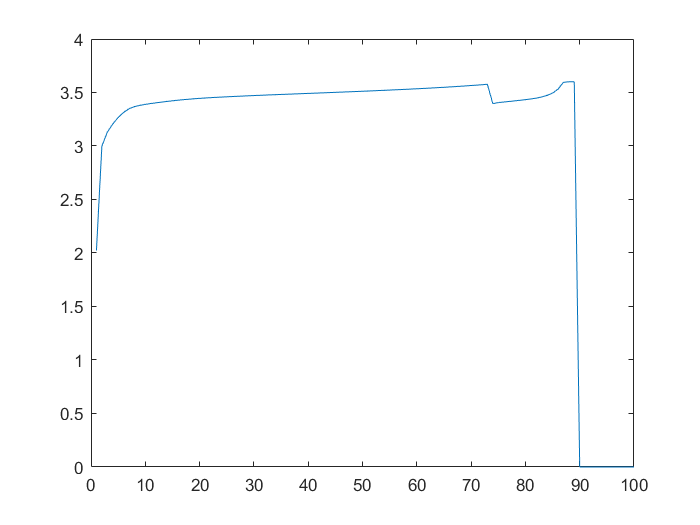


% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

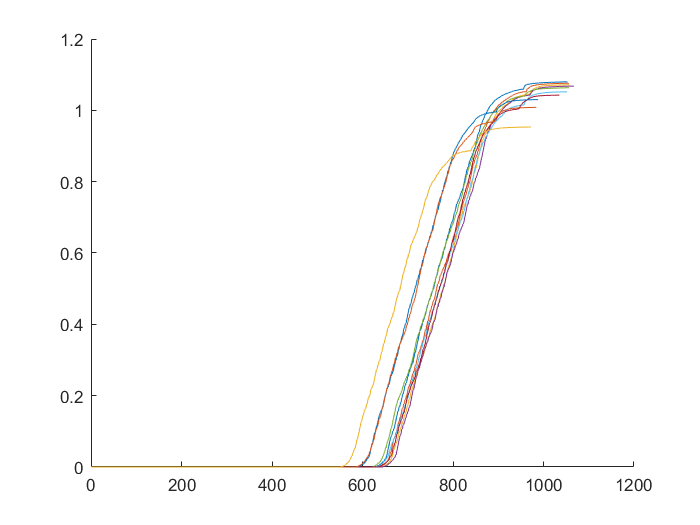

figure
hold on
for i=1:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
        plot(trainData(test_bat).cycles(i).Qd)
    end
end 
hold off 

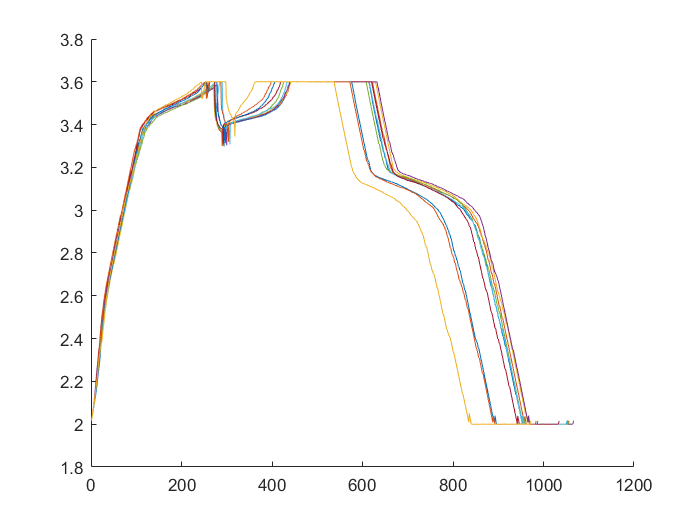

figure
hold on
for i=1:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    plot(trainData(test_bat).cycles(i).V')
    end
end 
hold off 

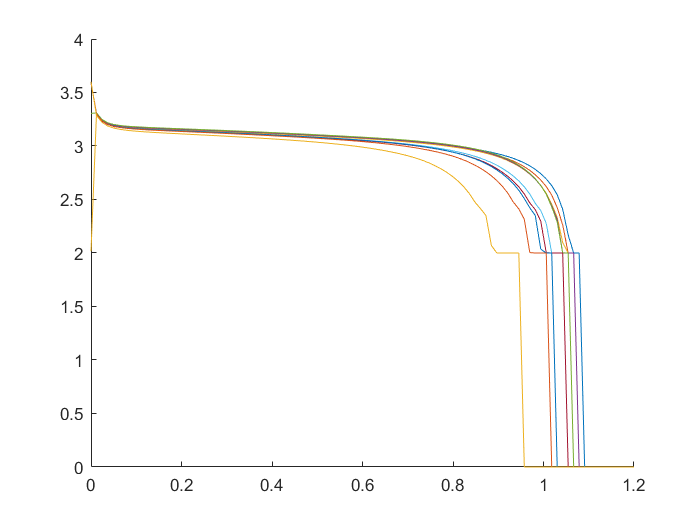

figure
hold on

for i=3:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    %[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
    [x_d, index] = unique(trainData(test_bat).cycles(i).Qd,"last");
    
    y_d = trainData(test_bat).cycles(i).V(index);
    new_x_d = linspace(0,1.2,100);
    new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
    new_y_d(isnan(new_y_d)) = 0;
    plot(new_x_d,new_y_d);
    end
end 
hold off

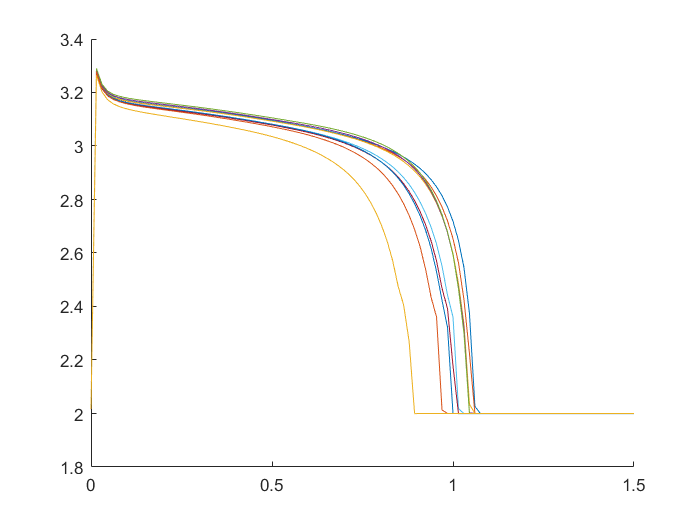

figure
hold on

for i=3:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    Qd_tmp = trainData(test_bat).cycles(i).Qd;
    Qd_tmp(Qd_tmp<0) = 0;
    %[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
    [xq, index] = unique(Qd_tmp,"first");
    
    yV = trainData(test_bat).cycles(i).V(index);
    xq_new = linspace(0,1.5,100);
    yV = interp1(xq,yV,xq_new,'linear'); 
    yV = fillmissing(yV,'nearest');
    %new_y_d(isnan(new_y_d)) = 0;
    plot(xq_new,yV);
    end
end 
hold off

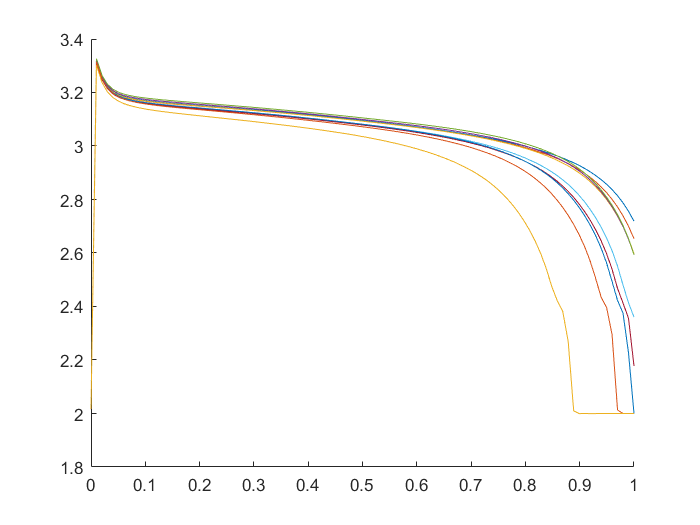

figure
hold on

for i=3:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    Qd_tmp = trainData(test_bat).cycles(i).Qd;
    Qd_tmp(Qd_tmp<0) = 0;
    %[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
    [xq, index] = unique(Qd_tmp,"first");
    
    yV = trainData(test_bat).cycles(i).V(index);
    xq_new = linspace(0,1.0,100);
    yV = interp1(xq,yV,xq_new,'linear'); 
    yV = fillmissing(yV,'nearest');
    %new_y_d(isnan(new_y_d)) = 0;
    plot(xq_new,yV);
    end
end 
hold off

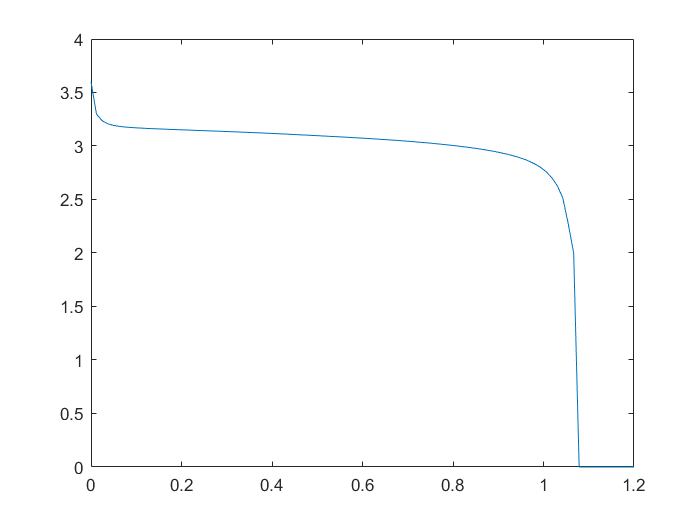


%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd,"last");

y_d = trainData(test_bat).cycles(cycleNum).V(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

%{
x_indexs = find(trainData(test_bat).cycles(2).Qd')
x_index = x_indexs(1)
x = trainData(test_bat).cycles(2).Qd';
x = x(x_index : end)
y = trainData(test_bat).cycles(2).V';
y = y(x_index : end)
new_x = linspace(0,1.2,100);
new_y = interp1(x,y,new_x,'linear'); 
plot(new_y)
%}   

# 다시 실험 시작 - 전류는 했으니 전압과 온도에 대해서 하자.

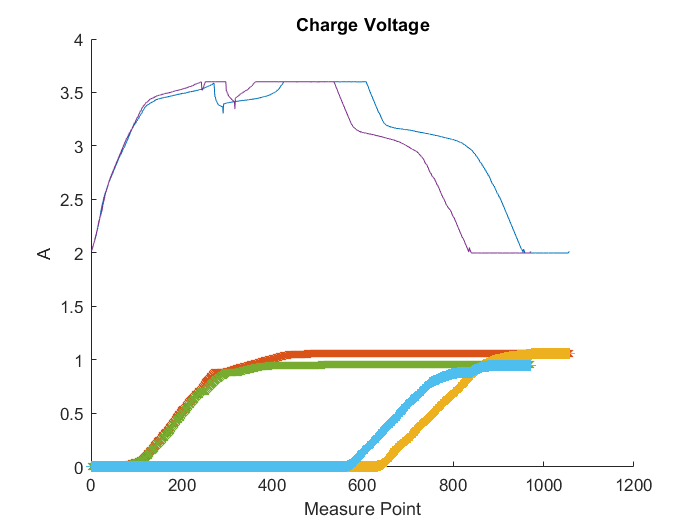

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).V)
        plot(trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).Qd,'+')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Voltage'

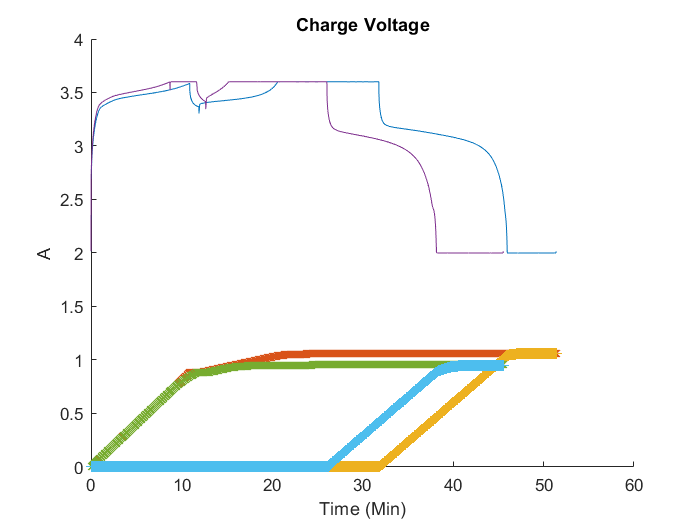

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).V)
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'+')        
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Charge Voltage'

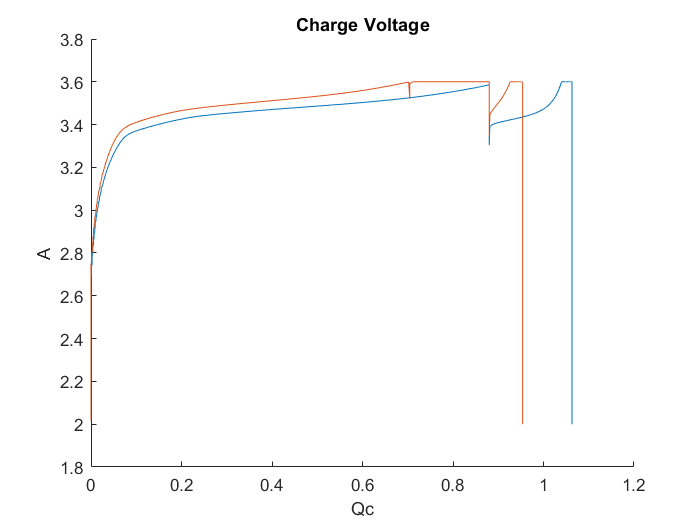


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,trainData(test_bat).cycles(i).V)     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Voltage'

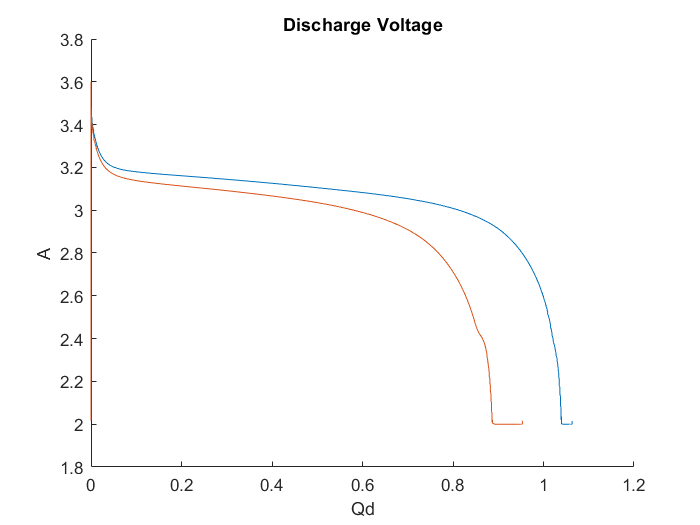


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,trainData(test_bat).cycles(i).V)     
    end
end
hold off , xlabel 'Qd' , ylabel 'A' , title 'Discharge Voltage'

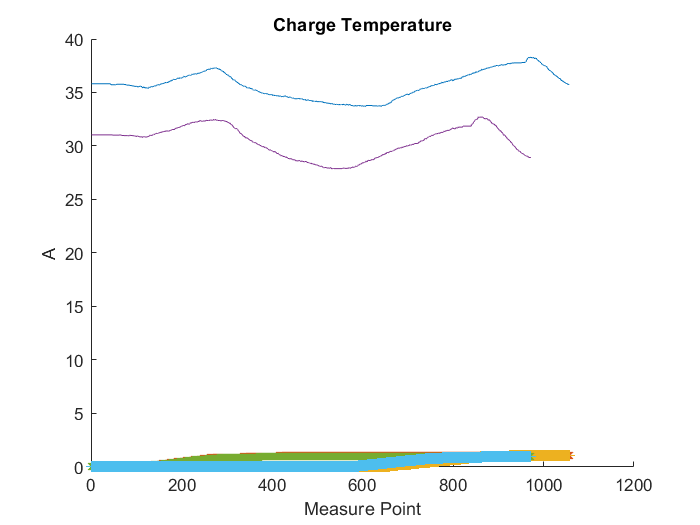

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).T)
        plot(trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).Qd,'+')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Temperature'

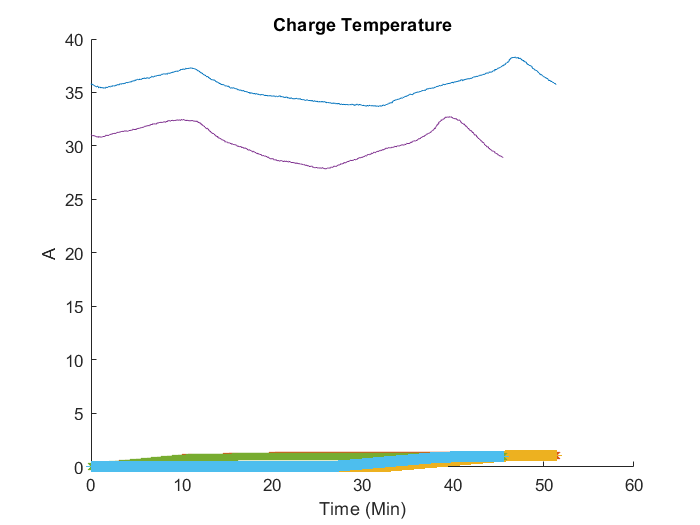

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).T)
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'+')        
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Charge Temperature'

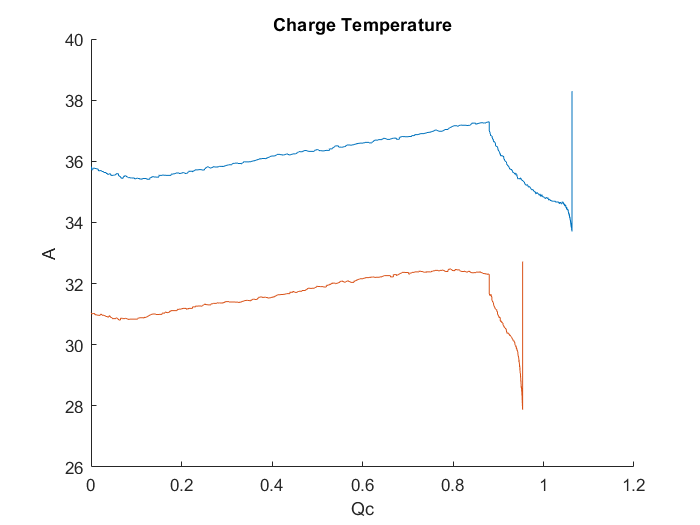


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,trainData(test_bat).cycles(i).T)     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Temperature'

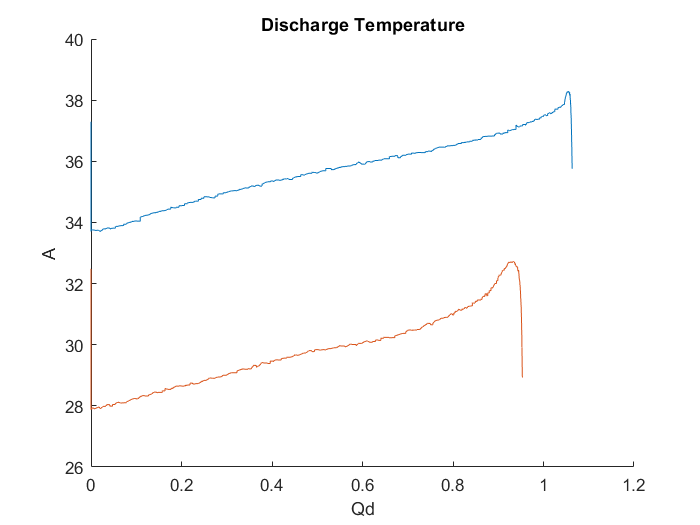


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,trainData(test_bat).cycles(i).T)     
    end
end
hold off , xlabel 'Qd' , ylabel 'A' , title 'Discharge Temperature'

데이타중 첫번째 batch에서 하나를 선택해서 데이타 확인



%batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"]
%batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"]
% src = trainData(1); % src has invaild item on index 1
% dest = trainData2(8); % dest has vaild item on index 1
% merge = merge_struct(trainData(1),trainData2(8));

src = trainData(1); % src has invaild item on index 1
dest = trainData2(8); % dest has vaild item on index 1

특정데이타는 다른 batch에 나눠져 있는 경우가 있어서 이를 합쳐야 한다.

merge = merge_struct(trainData(1),trainData2(8));

% verify
src.cycle_life

ans = 1190

dest.cycle_life

ans = 663

src.cycle_life + dest.cycle_life - 1

ans = 1852

merge.cycle_life

ans = 1852

length(src.summary.QDischarge)

ans = 1189

length(dest.summary.QDischarge)

ans = 662

length(merge.summary.QDischarge)

ans = 1851

%%%%%%%%%%%
src.summary.QDischarge(1)

ans = 0

src.summary.QDischarge(2)

ans = 1.0707

src.summary.QDischarge(end-1)

ans = 1.0267

src.summary.QDischarge(end)

ans = 1.0262

%%%%
dest.summary.QDischarge(1)

ans = 1.0219

dest.summary.QDischarge(2)

ans = 1.0233

dest.summary.QDischarge(end-1)

ans = 0.8843

dest.summary.QDischarge(end)

ans = 0.8828

%%%%
merge.summary.QDischarge(1)

ans = 0

merge.summary.QDischarge(2)

ans = 1.0707

merge.summary.QDischarge(length(src.summary.QDischarge)-1)

ans = 1.0267

merge.summary.QDischarge(length(src.summary.QDischarge))

ans = 1.0262

merge.summary.QDischarge(length(src.summary.QDischarge)+1)

ans = 1.0219

merge.summary.QDischarge(length(src.summary.QDischarge)+2)

ans = 1.0233

merge.summary.QDischarge(end-1)

ans = 0.8843

merge.summary.QDischarge(end)

ans = 0.8828

test = zeros();
test = ryan4_extract_feature(1,1,merge);

#batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))

batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))

#remove batteries that do not reach 80% capacity

del batch1['b1c8']

del batch1['b1c10']

del batch1['b1c12']

del batch1['b1c13']

del batch1['b1c22']

///////////

# There are four cells from batch1 that carried into batch2, we'll remove the data from batch2

# and put it with the correct cell from batch1

batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']

batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']

add_len = [662, 981, 1060, 208, 482];

for i, bk in enumerate(batch1_keys):

    batch1[bk]['cycle_life'] = batch1[bk]['cycle_life'] + add_len[i]

    for j in batch1[bk]['summary'].keys():

        if j == 'cycle':

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j] + len(batch1[bk]['summary'][j])))

        else:

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j]))

    last_cycle = len(batch1[bk]['cycles'].keys())

    for j, jk in enumerate(batch2[batch2_keys[i]]['cycles'].keys()):

        batch1[bk]['cycles'][str(last_cycle + j)] = batch2[batch2_keys[i]]['cycles'][jk]

del batch2['b2c7']

del batch2['b2c8']

del batch2['b2c9']

del batch2['b2c15']

del batch2['b2c16']

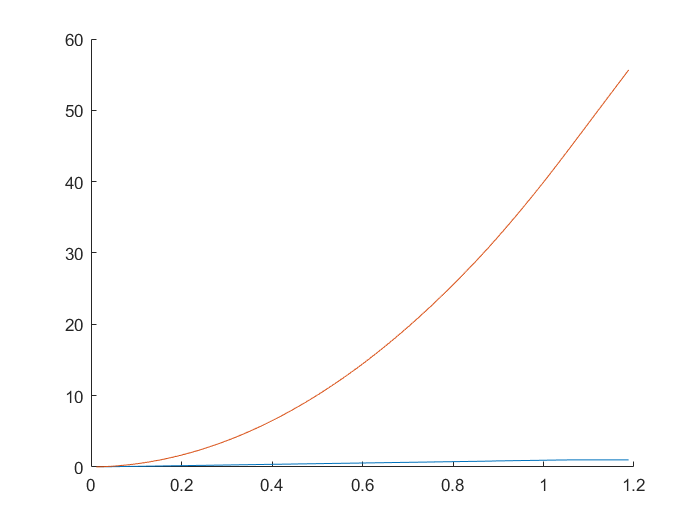


figure, hold on
plot(x_axis_ah,SOC_c)
plot(x_axis_ah,cumsum(SOC_c))
hold off 

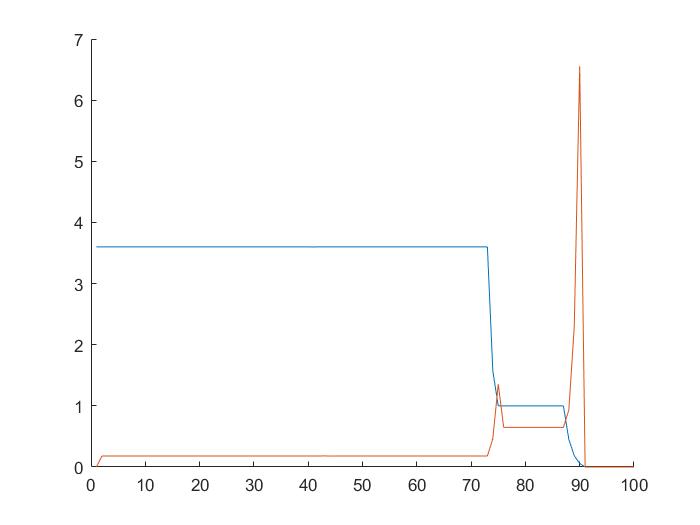

index = 1;
figure, hold on
plot(ryan4_battery_dataset_raw.Ic(index,:))
plot([ 0 diff(ryan4_battery_dataset_raw.Time_c(index,:))])
hold off

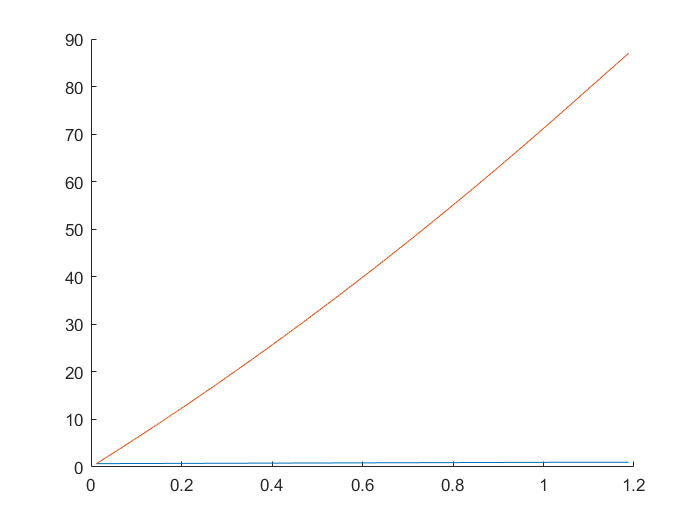




figure, hold on
plot(x_axis_ah,SOC_d)
plot(x_axis_ah,cumsum(SOC_d))
hold off 

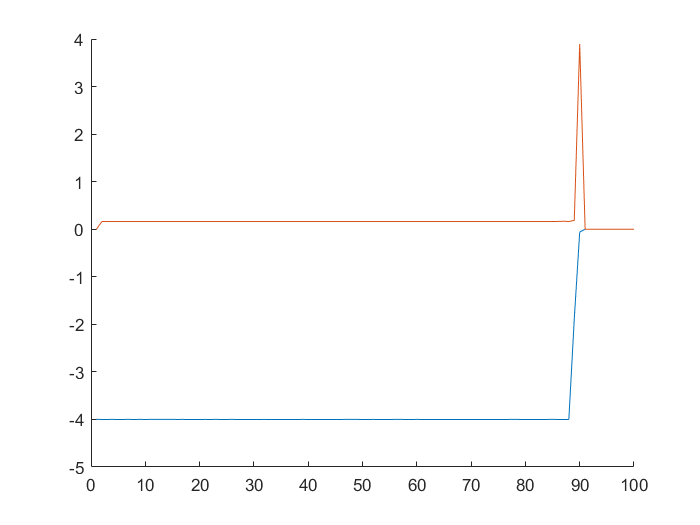


figure, hold on
plot(ryan4_battery_dataset_raw.Id(index,:))
plot([ 0 diff(ryan4_battery_dataset_raw.Time_d(index,:))])
hold off

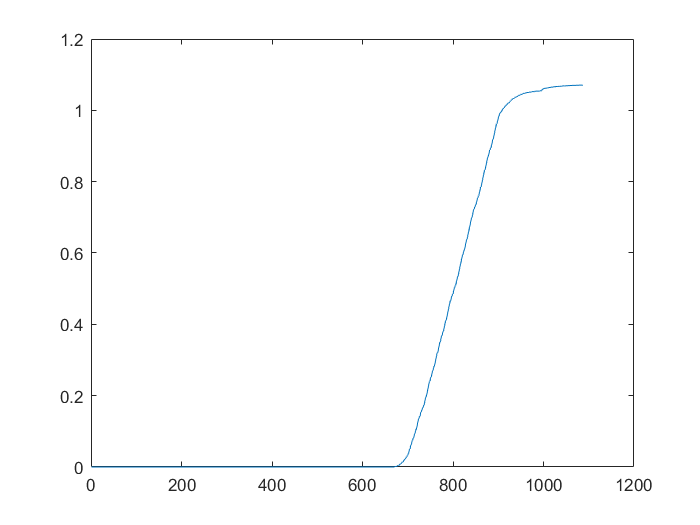

figure
plot(trainData(1).cycles(2).Qd)

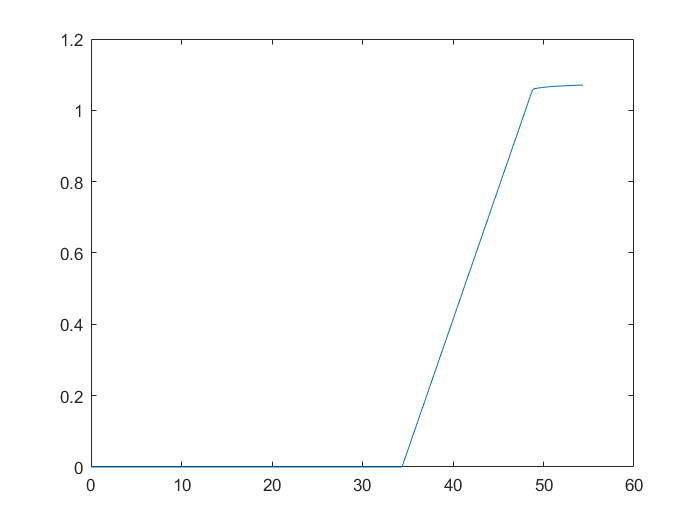

figure
plot(trainData(1).cycles(2).t, trainData(1).cycles(2).Qd)

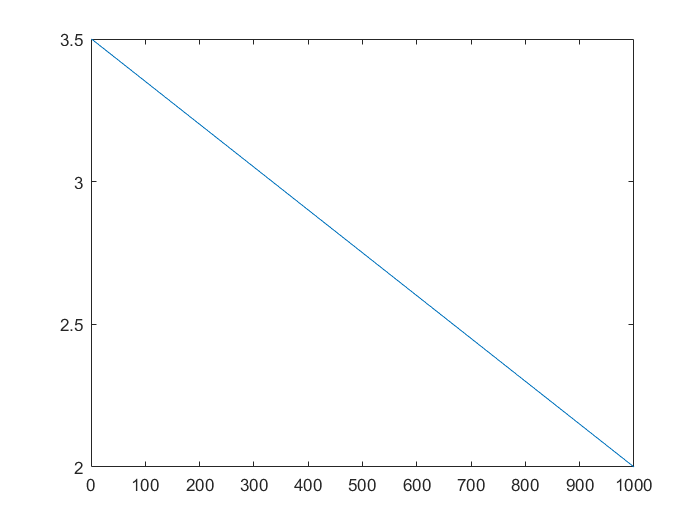


figure
plot(trainData(1).Vdlin)

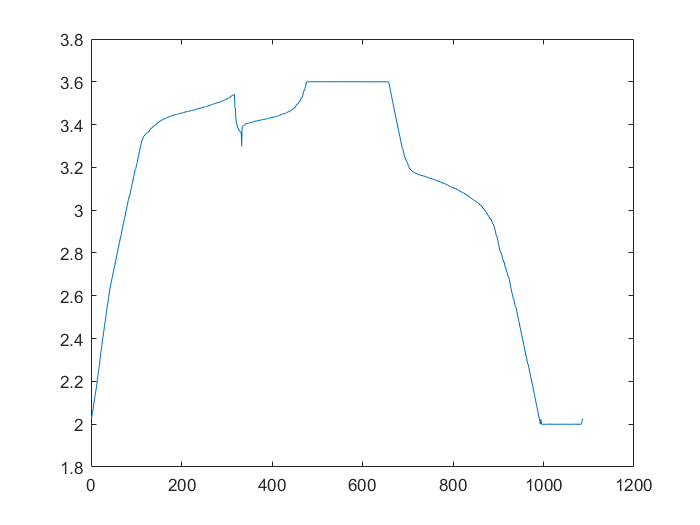

figure
plot(trainData(1).cycles(2).V)

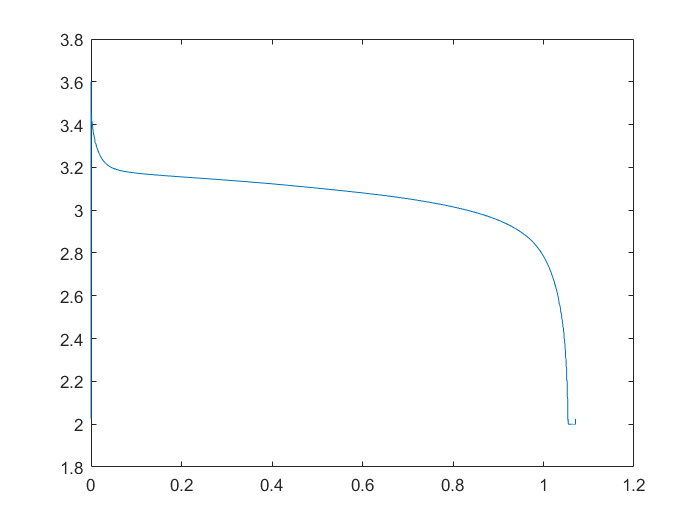

figure
plot(trainData(1).cycles(2).Qd, trainData(1).cycles(2).V)

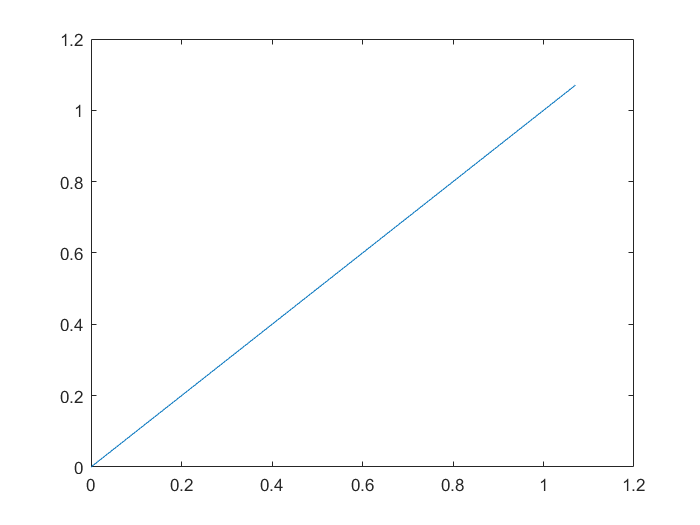



figure
plot(trainData(1).cycles(2).Qd, trainData(1).cycles(2).Qd)

% https://github.com/lanmei1211/Battery_Cycle_Life_Prediction_Pytorch/blob/a5c4705111feb14a8739595c50be4cac0eca3157/data_preprocessing.py#L121

%{
figure
base = trainData(1).Vdlin';
base(base<0) = 0;
%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[xq, index] = unique(base,"first");

yQd = trainData(1).cycles(2).Qd(index);
xq_new = linspace(0,999,1000);
yQd = interp1(xq,yQd,xq_new,'linear'); 
yQd = fillmissing(yQd,'nearest');
%new_y_d(isnan(new_y_d)) = 0;
plot(xq_new,yQd);
%}

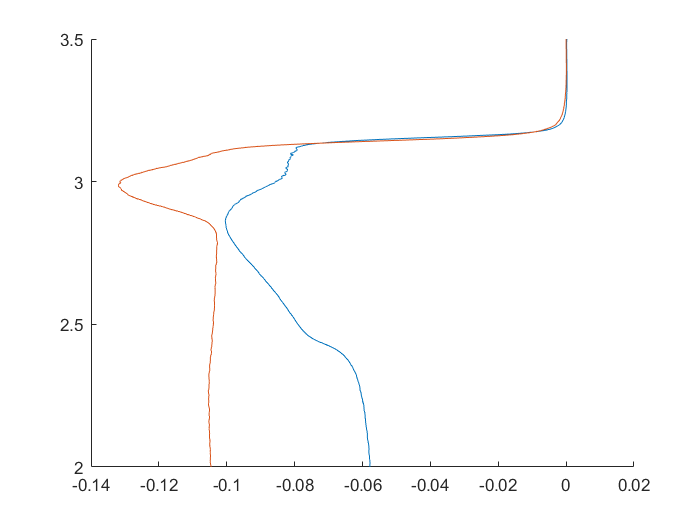


figure
hold on
plot((trainData2(1).cycles(100).Qdlin - trainData2(1).cycles(2).Qdlin), trainData2(1).Vdlin )
plot((trainData2(2).cycles(100).Qdlin - trainData2(2).cycles(2).Qdlin), trainData2(2).Vdlin )
hold off

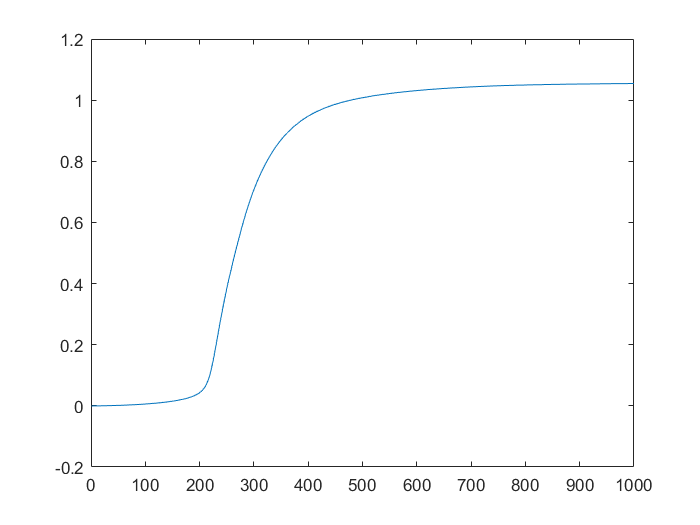


figure
plot(trainData(1).cycles(2).Qdlin)

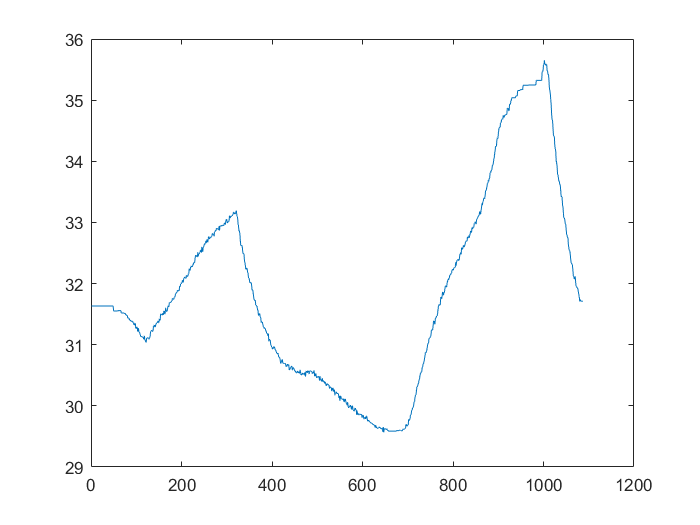


figure
plot(trainData(1).cycles(2).T)

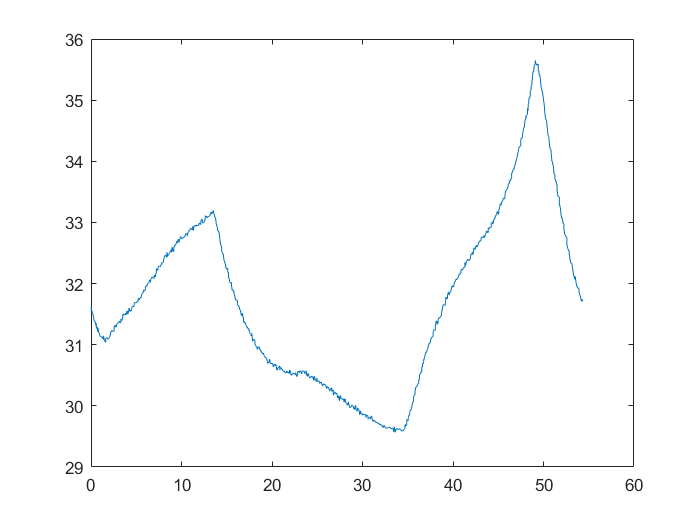

figure 
plot(trainData(1).cycles(2).t, trainData(1).cycles(2).T)

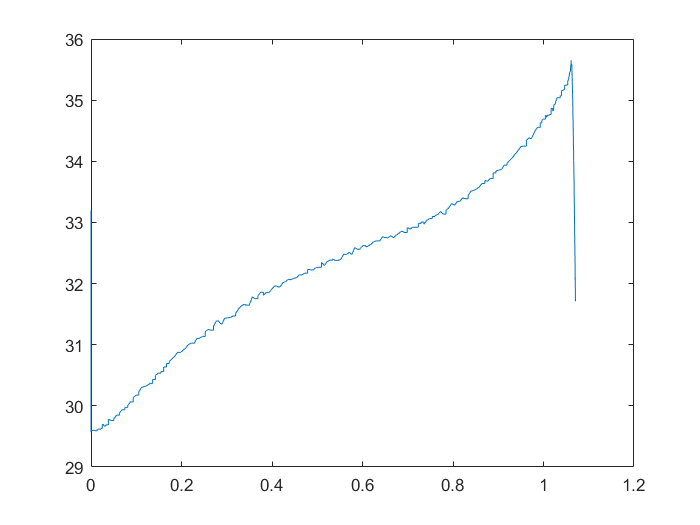


figure 
plot(trainData(1).cycles(2).Qd, trainData(1).cycles(2).T)

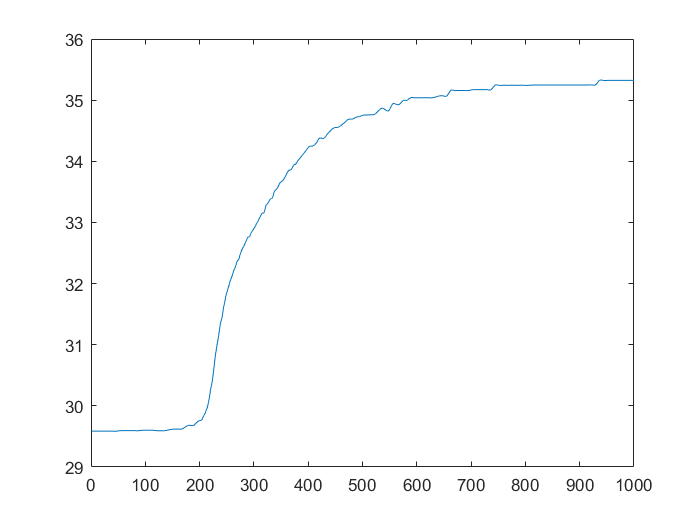


figure
plot(trainData(1).cycles(2).Tdlin)

%{
new_time = 0.0;
for i=2:length(ryan4_battery_dataset_raw.cycle_life) 
    time = ryan4_battery_dataset_raw.Time_c(i,end)  
    new_time = [ new_time 
end
%}

ryan4_battery_dataset_raw = zeros();
% 이 코드가 중요함. ryan4_battery_dataset_raw 이 structure를 가짐을 알려주어야 함.
ryan4_battery_dataset_raw = ryan4_extract_feature(1,1,trainData(1));

% 1.1 * 0.8 = 0.88 Ah = EOL
% batch 2 = get data under 0.88 Ah - to remove this data under EOL
test2 = ryan4_extract_feature(2,1,trainData2(1));
test1 = ryan4_extract_feature(1,1,trainData(1));
test3 = ryan4_extract_feature(3,1,trainData3(1));
skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index

% # There are four cells from batch1 that carried into batch2, we'll remove the data from batch2
% # and put it with the correct cell from batch1
% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

skip_bat2 = [7 8 9 15 16 ]; % base 0 index
skip_bat2 = skip_bat2 +1; % to 1 index

batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"];
batch2_fix = [8 9 10 16 17];
batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"];
batch1_fix = [1 2 3 4 5];

batchNum =1;
for batNum = 1:size(trainData,2)
    if numel(trainData(batNum).summary.cycle) == numel(unique(trainData(batNum).summary.cycle))
        if ismember(batNum,skip_bat1) 
            batNum;
        elseif ismember(batNum,batch1_fix) 
            %ismember(batNum,batch1_fix) % true or fale
            idx = find(batch1_fix==batNum);
            % find(strcmp
%             batch1_fix(idx)
%             batch2_fix(idx)
            src = trainData(batch1_fix(idx));
            dest = trainData2(batch2_fix(idx));
            merge = merge_struct(trainData(batch1_fix(idx)),trainData2(batch2_fix(idx)));
            ryan4_battery_dataset_raw(new_index) = ryan4_extract_feature(batchNum,batNum,merge);
            batNum;      
        else
            ryan4_battery_dataset_raw(new_index) = ryan4_extract_feature(batchNum,batNum,trainData(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

%%%%%%%%%%%%%
batchNum = 2;
for batNum = 1:size(trainData2,2)
    if numel(trainData2(batNum).summary.cycle) == numel(unique(trainData2(batNum).summary.cycle))
        if ismember(batNum,batch2_fix) 
            batNum;
        else
            ryan4_battery_dataset_raw(new_index) = ryan4_extract_feature(batchNum,batNum,trainData2(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end


%%%%%%%%%%%%%%%
batchNum = 3;
skip_bat3 = [37 2 23 32 42 43 ]; % base 0 index
skip_bat3 = skip_bat3 +1; % to 1 index

% # remove noisy channels from batch3
% del batch3['b3c37']
% del batch3['b3c2']
% del batch3['b3c23']
% del batch3['b3c32']
% del batch3['b3c42']
% del batch3['b3c43']

for batNum = 1:size(trainData3,2)
    if numel(trainData3(batNum).summary.cycle) == numel(unique(trainData3(batNum).summary.cycle))
        if ismember(batNum,skip_bat3) 
            batNum;
        else
            ryan4_battery_dataset_raw(new_index) = ryan4_extract_feature(batchNum,batNum,trainData3(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

# 첫번째 정제된 데이타

ryan4_gen_data_raw_org_desc = 'ryan4_gen_data_raw_org_desc';
%save('ryan4_data_raw_org.mat','ryan4_gen_data_raw_org_desc');
save('ryan4_data_raw_org.mat','ryan4_battery_dataset_raw' ,'-append')

ryan4_battery_dataset_raw_sample1 = ryan4_battery_dataset_raw(1);
ryan4_battery_dataset_raw_sample2 = ryan4_battery_dataset_raw(2);
ryan4_battery_dataset_raw_sample3 = ryan4_battery_dataset_raw(3);


save('ryan4_battery_dataset_raw_sample1.mat','ryan4_battery_dataset_raw_sample1' )
save('ryan4_battery_dataset_raw_sample2.mat','ryan4_battery_dataset_raw_sample2' )
save('ryan4_battery_dataset_raw_sample3.mat','ryan4_battery_dataset_raw_sample3' )




%{
clear trainData
clear trainData2
clear trainData3
clear merge
clear src
clear dest


save('ryan4_data_raw_org.mat', 'plot_Vc'                             ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Vd'                             ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Ic'                             ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Id'                             ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Tc'                             ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Td'                             ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Time_c'                         ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Time_d'                        ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_discharge_dQdV'                 ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Qdlin'                          ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Tdlin'                          ,'-append')'
save('ryan4_data_raw_org.mat', 'plot_Vdlin'                          ,'-append')'
%}

# 시작  Ah을 고정하자. 이보다 큰 데이타는 모두 지우자.

# 먼저 데이타 하나로 테스트

data_conversion_param = zeros();
data_conversion_param = [0 0 0 0 0 0];

idxAll = (1:length(ryan4_battery_dataset_raw))

idxAll = 1×119
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


idx = idxAll

idx = 1×119
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


i=1 

i = 1

j = idx(i)

j = 1

ryan4_battery_dataset_raw(i).QDischargeSmooth(1) 

ans = 1.0795



ryan4_battery_dataset = zeros()

ryan4_battery_dataset = 0

ryan4_battery_dataset = ryan4_battery_dataset_raw(1)

ryan4_battery_dataset = struct with fields:
               policy: '4_4C-80PER_4_4C'
      policy_readable: '4.4C(80%)-4.4C'
           channel_id: "7"
           cycle_life: 1072
                  key: "b1c6"
             batchNum: 1
               batNum: 6
           chargetime: [1072×1 double]
                cycle: [1072×1 double]
                   IR: [1072×1 double]
              QCharge: [1072×1 double]
           QDischarge: [1072×1 double]
                 Tavg: [1072×1 double]
                 Tmin: [1072×1 double]
                 Tmax: [1072×1 double]
                Vdlin: [100×1 double]
                   Vc: [1072×100 double]
                   Tc: [1072×100 double]
                   Vd: [1072×100 double]
                   Td: [1072×100 double]
              VT_leng: 102
                   Ic: [1072×100 double]
                   Id: [1072×100 double]
               Time_c: [1072×100 double]
               Time_d: [1072×100 double]
              Time_d1: [1072×100 do

i=1;
for ii = 1:1000
    if ryan4_battery_dataset_raw(i).QDischargeSmooth(ii) <= 1.048
        % skip count 
        break
    end
end
ii

ii = 644

ryan4_battery_dataset(i) = ryan4_battery_dataset_raw(i);
ryan4_battery_dataset(i).cycle_life = ryan4_battery_dataset_raw(i).cycle_life - ii;
ryan4_battery_dataset_raw(i).cycle_life

ans = 1072

ryan4_battery_dataset(i).cycle_life

ans = 428

ryan4_battery_dataset(i).chargetime([1:ii],:) = [] ;

size(ryan4_battery_dataset_raw(i).chargetime)

ans = 1×2
        1072           1


size(ryan4_battery_dataset(i).chargetime)

ans = 1×2
   428     1


ryan4_battery_dataset(i).cycle = [] ;
ryan4_battery_dataset(i).cycle = ryan4_battery_dataset_raw(i).cycle(1:end-ii,:);
ryan4_battery_dataset(i).IR([1:ii],:) = [] ;
ryan4_battery_dataset(i).QCharge([1:ii],:) = [] ;
ryan4_battery_dataset(i).QDischarge([1:ii],:) = [] ;
ryan4_battery_dataset(i).SOH_c([1:ii],:) = [] ;
ryan4_battery_dataset(i).SOH_d([1:ii],:) = [] ;
ryan4_battery_dataset(i).Time_c([1:ii],:) = [] ;
ryan4_battery_dataset(i).Time_d([1:ii],:) = [] ;
ryan4_battery_dataset(i).Time_d1([1:ii],:) = [] ;
ryan4_battery_dataset(i).Tavg([1:ii],:) = [] ;
ryan4_battery_dataset(i).Tmin([1:ii],:) = [] ;
ryan4_battery_dataset(i).Tmax([1:ii],:) = [] ;
ryan4_battery_dataset(i).Vc([1:ii],:) = [] ;
ryan4_battery_dataset(i).Vd([1:ii],:) = [] ;
ryan4_battery_dataset(i).Tc([1:ii],:) = [] ;
ryan4_battery_dataset(i).Td([1:ii],:) = [] ;
ryan4_battery_dataset(i).Ic([1:ii],:) = [] ;
ryan4_battery_dataset(i).Id([1:ii],:) = [] ;

ryan4_battery_dataset(i).discharge_dQdV([1:ii],:) = [] ;
ryan4_battery_dataset(i).Qdlin([1:ii],:) = [] ;
ryan4_battery_dataset(i).Tdlin([1:ii],:) = [] ;

ryan4_battery_dataset(i).QChargeSmooth([1:ii],:) = [] ;
ryan4_battery_dataset(i).QDischargeSmooth([1:ii],:) = [] ;
ryan4_battery_dataset(i).QDischargePolyMdl = [];
ryan4_battery_dataset(i).QDischargePolyMdl = polyfit(ryan4_battery_dataset(i).cycle, ryan4_battery_dataset(i).QDischargeSmooth,4);
ryan4_battery_dataset(i).QDischargePolyfit = [];
ryan4_battery_dataset(i).QDischargePolyfit = polyval(ryan4_battery_dataset.QDischargePolyMdl,ryan4_battery_dataset.cycle')';

# 전체 데이타에 대해 특정 Ah보다 큰 것은 모두 지우자 

%%%%%%%%%%%%%%%%%%
% get first capacity
for i = 1:length(idxAll)
    %j = idx(i);
    initC = ryan4_battery_dataset_raw(i).QDischargeSmooth(1) ;

    for ii = 1:ryan4_battery_dataset_raw(i).cycle_life
        if ryan4_battery_dataset_raw(i).QDischargeSmooth(ii) <= 1.048
            % skip count 
            break
        end
        if ii == ryan4_battery_dataset_raw(i).cycle_life
            error_is = true;
        end
    end
    %              bat_num        new_start_index  
    
    ryan4_battery_dataset(i) = ryan4_battery_dataset_raw(i);
    ryan4_battery_dataset(i).cycle_life = ryan4_battery_dataset_raw(i).cycle_life - ii;
    %ryan4_battery_dataset_raw(i).cycle_life
    %ryan4_battery_dataset(i).cycle_life
    ryan4_battery_dataset(i).chargetime([1:ii],:) = [] ;

    data_conversion_param(i,:) = [ i      initC  ii   ryan4_battery_dataset_raw(i).QDischargeSmooth(ii)   ryan4_battery_dataset_raw(i).cycle_life ryan4_battery_dataset(i).cycle_life    ];
    
    %size(ryan4_battery_dataset_raw(i).chargetime)
    %size(ryan4_battery_dataset(i).chargetime)
    ryan4_battery_dataset(i).cycle = [] ;
    ryan4_battery_dataset(i).cycle = ryan4_battery_dataset_raw(i).cycle(1:end-ii,:);
    ryan4_battery_dataset(i).IR([1:ii],:) = [] ;
    ryan4_battery_dataset(i).QCharge([1:ii],:) = [] ;
    ryan4_battery_dataset(i).QDischarge([1:ii],:) = [] ;
    ryan4_battery_dataset(i).SOH_c([1:ii],:) = [] ;
    ryan4_battery_dataset(i).SOH_d([1:ii],:) = [] ;  
    ryan4_battery_dataset(i).Time_c([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Time_d([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Time_d1([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Tavg([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Tmin([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Tmax([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Vc([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Vd([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Ic([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Id([1:ii],:) = [] ;    
    ryan4_battery_dataset(i).Tc([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Td([1:ii],:) = [] ;

    
    ryan4_battery_dataset(i).discharge_dQdV([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Qdlin([1:ii],:) = [] ;
    ryan4_battery_dataset(i).Tdlin([1:ii],:) = [] ;

    ryan4_battery_dataset(i).QChargeSmooth([1:ii],:) = [] ;    
    ryan4_battery_dataset(i).QDischargeSmooth([1:ii],:) = [] ;
    ryan4_battery_dataset(i).QDischargePolyMdl = [];
    ryan4_battery_dataset(i).QDischargePolyMdl = polyfit(ryan4_battery_dataset(i).cycle, ryan4_battery_dataset(i).QDischargeSmooth,4);
    ryan4_battery_dataset(i).QDischargePolyfit = [];
    ryan4_battery_dataset(i).QDischargePolyfit = polyval(ryan4_battery_dataset(i).QDischargePolyMdl,ryan4_battery_dataset(i).cycle')';


end
data_conversion_param 

data_conversion_param = 119×6
	1.0e+03 *

    0.0010    0.0011    0.6440    0.0010    1.0720    0.4280
    0.0020    0.0011    0.4050    0.0010    0.6340    0.2290
    0.0030    0.0011    0.6150    0.0010    0.8680    0.2530
    0.0040    0.0011    0.7140    0.0010    1.0520    0.3380
    0.0050    0.0011    0.3700    0.0010    0.7860    0.4160
    0.0060    0.0011    0.5470    0.0010    0.8780    0.3310
    0.0070    0.0011    0.4390    0.0010    0.7170    0.2780
    0.0080    0.0011    0.6250    0.0010    0.8600    0.2350
    0.0090    0.0011    0.5710    0.0010    0.8550    0.2840
    0.0100    0.0011    0.2270    0.0010    0.6890    0.4620


max(data_conversion_param(:,2))

ans = 1.0982

min(data_conversion_param(:,2))

ans = 1.0480

length(ryan4_battery_dataset)

ans = 119

size(ryan4_battery_dataset)

ans = 1×2
     1   119


[ryan4_battery_dataset.key]

ans = 1×119 string array
    "b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b3c8"    "b3c9"    "b3c10"    "b3c11"    "b3c12"   

{[ryan4_battery_dataset.key]}

ans = 1×1 cell array
    {["b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b3c8"    "b3c9"    "b3c10"    "b3c11"    "b3c12"    "

contains([ryan4_battery_dataset.key],'b1','IgnoreCase',true)

ans = 1×119 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


contains([ryan4_battery_dataset.key],'b2','IgnoreCase',true)

ans = 1×119 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


contains([ryan4_battery_dataset.key],'b3','IgnoreCase',true)

ans = 1×119 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


idx1 = find(contains([ryan4_battery_dataset.key],'b1','IgnoreCase',true))

idx1 = 1×36
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


idx2 = find(contains([ryan4_battery_dataset.key],'b2','IgnoreCase',true))

idx2 = 1×43
    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66


idx3 = find(contains([ryan4_battery_dataset.key],'b3','IgnoreCase',true))

idx3 = 1×40
    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109


idx12 = [idx1 idx2]

idx12 = 1×79
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


idx13 = [idx1 idx3]

idx13 = 1×76
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


idx23 = [idx2 idx3]

idx23 = 1×83
    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66


idxAll = (1:length(ryan4_battery_dataset))

idxAll = 1×119
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


idx123 = [idx1 idx2 idx3]

idx123 = 1×119
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30



key1 = [ryan4_battery_dataset(idx1).key]'

key1 = 36×1 string array
    "b1c6"
    "b1c7"
    "b1c8"
    "b1c10"
    "b1c12"
    "b1c15"
    "b1c16"
    "b1c17"
    "b1c18"
    "b1c19"
    "b1c20"
    "b1c21"
    "b1c22"
    "b1c24"
    "b1c25"
    "b1c26"
    "b1c27"
    "b1c28"
    "b1c29"
    "b1c30"
    "b1c31"
    "b1c32"
    "b1c33"
    "b1c34"
    "b1c35"
    "b1c36"
    "b1c37"
    "b1c38"
    "b1c39"
    "b1c40"


key2 = [ryan4_battery_dataset(idx2).key]'

key2 = 43×1 string array
    "b2c1"
    "b2c2"
    "b2c3"
    "b2c4"
    "b2c5"
    "b2c6"
    "b2c7"
    "b2c11"
    "b2c12"
    "b2c13"
    "b2c14"
    "b2c15"
    "b2c18"
    "b2c19"
    "b2c20"
    "b2c21"
    "b2c22"
    "b2c23"
    "b2c24"
    "b2c25"
    "b2c26"
    "b2c27"
    "b2c28"
    "b2c29"
    "b2c30"
    "b2c31"
    "b2c32"
    "b2c33"
    "b2c34"
    "b2c35"


key3 = [ryan4_battery_dataset(idx3).key]'

key3 = 40×1 string array
    "b3c1"
    "b3c2"
    "b3c4"
    "b3c5"
    "b3c6"
    "b3c7"
    "b3c8"
    "b3c9"
    "b3c10"
    "b3c11"
    "b3c12"
    "b3c13"
    "b3c14"
    "b3c15"
    "b3c16"
    "b3c17"
    "b3c18"
    "b3c19"
    "b3c20"
    "b3c21"
    "b3c22"
    "b3c23"
    "b3c25"
    "b3c26"
    "b3c27"
    "b3c28"
    "b3c29"
    "b3c30"
    "b3c31"
    "b3c32"


cycle_life = [ryan4_battery_dataset(idxAll).cycle_life]'

cycle_life = 119×1
   428
   229
   253
   338
   416
   331
   278
   235
   284
   462


bat_index = [1:length(idxAll)]'

bat_index = 119×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


index_cyclelife = [ bat_index, cycle_life]

index_cyclelife = 119×2
     1   428
     2   229
     3   253
     4   338
     5   416
     6   331
     7   278
     8   235
     9   284
    10   462


% https://kr.mathworks.com/help/matlab/ref/double.sortrows.html#bt8bz9j-3
index_cyclelife_table = table(bat_index,cycle_life)

index_cyclelife_table = 119×2 table
    bat_index    cycle_life
    _________    __________

        1           428    
        2           229    
        3           253    
        4           338    
        5           416    
        6           331    
        7           278    
        8           235    
        9           284    
       10           462    
       11           269    
       12           379    
       13           300    
       14           354    
       15           405    
       16           316    


[index_cyclelife_table_sort,index] = sortrows(index_cyclelife_table,{'cycle_life'},{'ascend'})

index_cyclelife_table_sort = 119×2 table
    bat_index    cycle_life
    _________    __________

       38           109    
       78           115    
       71           118    
       69           129    
       65           137    
       76           140    
       61           146    
       74           146    
       73           152    
       66           153    
       70           153    
       64           154    
       68           155    
       75           157    
       63           161    
       48           168    


index = 119×1
    38
    78
    71
    69
    65
    76
    61
    74
    73
    66



%%%%%%%%%%%%%%%%
total_index = length(idxAll)

total_index = 119

	
index_cyclelife_table_sort.Variables

ans = 119×2
    38   109
    78   115
    71   118
    69   129
    65   137
    76   140
    61   146
    74   146
    73   152
    66   153


index_cyclelife_table_sort.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'bat_index'  'cycle_life'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


[~, maxrow] = max(index_cyclelife_table_sort.bat_index)

maxrow = 116

%maxrowname = index_cyclelife_table_sort.Properties.RowNames(1:maxrow-1)
%index_cyclelife_table_sort.Properties.RowNames

index_vec = [1:total_index]

index_vec = 1×119
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


idxVal_ = index_vec(5:10:end)

idxVal_ = 1×12
     5    15    25    35    45    55    65    75    85    95   105   115


idxTest_ = index_vec(6:10:end)

idxTest_ = 1×12
     6    16    26    36    46    56    66    76    86    96   106   116


idxTrain_ = setdiff(index_vec,idxVal_);
idxTrain_ = setdiff(idxTrain_,idxTest_)

idxTrain_ = 1×95
     1     2     3     4     7     8     9    10    11    12    13    14    17    18    19    20    21    22    23    24    27    28    29    30    31    32    33    34    37    38


idxTestTable = index_cyclelife_table_sort(idxTest_,{'bat_index'})

idxTestTable = 12×1 table
    bat_index
    _________

        76   
        48   
        62   
        28   
        26   
        47   
        16   
        99   
        92   
       106   
        84   
       119   


idxTrainTable = index_cyclelife_table_sort(idxTrain_,{'bat_index'})

idxTrainTable = 95×1 table
    bat_index
    _________

       38    
       78    
       71    
       69    
       61    
       74    
       73    
       66    
       70    
       64    
       68    
       75    
       52    
       60    
       30    
       36    


idxValTable = index_cyclelife_table_sort(idxVal_,{'bat_index'})

idxValTable = 12×1 table
    bat_index
    _________

        65   
        63   
        56   
        59   
        40   
        11   
        46   
        14   
        94   
        10   
       100   
       115   


idxTest = idxTestTable.Variables'

idxTest = 1×12
    76    48    62    28    26    47    16    99    92   106    84   119


idxValid = idxValTable.Variables'

idxValid = 1×12
    65    63    56    59    40    11    46    14    94    10   100   115


idxTrain = idxTrainTable.Variables'

idxTrain = 1×95
    38    78    71    69    61    74    73    66    70    64    68    75    52    60    30    36    39    54    67    77    35    42    72    21    29    37    58    49    24    25


idxAll

idxAll = 1×119
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


idxTrainSort = sort(idxTrain)

idxTrainSort = 1×95
     1     2     3     4     5     6     7     8     9    12    13    15    17    18    19    20    21    22    23    24    25    27    29    30    31    32    33    34    35    36


idxValidSort = sort(idxValid)

idxValidSort = 1×12
    10    11    14    40    46    56    59    63    65    94   100   115


idxTestSort = sort(idxTest)

idxTestSort = 1×12
    16    26    28    47    48    62    76    84    92    99   106   119



%https://kr.mathworks.com/matlabcentral/answers/101996-how-can-i-sort-a-vector-in-a-random-manner-in-matlab

idxTestRand =  idxTest(randperm(length(idxTest)))

idxTestRand = 1×12
    47    62    84    16    99    26    76    48    28    92   106   119


idxTrainRand =  idxTrain(randperm(length(idxTrain)))

idxTrainRand = 1×95
   112    77    49    64    42    89    81    72    34    82    20    69    31    79    17    86    54    53    90     9    88    43   108    93     4   114    55    35   116    96


idxValidRand =  idxValid(randperm(length(idxValid)))

idxValidRand = 1×12
   115    40    14    11    59    10    65    63    56    94    46   100



%sortrows(idxValTable,{'cycle_life'},{'ascend'})
input_size = 100;


# 시작 Ah 를 동일하게 맞춘 데이타 

ryan4_gen_data_raw_desc = 'ryan4_gen_data_raw_desc';
%save('ryan4_data_raw.mat','ryan4_gen_data_raw_desc');
save('ryan4_data_raw.mat','ryan4_battery_dataset' ,'-append')

cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

a = ryan4_battery_dataset(idxTest(1)).QDischargeSmooth;
b = ryan4_battery_dataset(idxTest(end)).QDischargeSmooth;
a1 = ryan4_battery_dataset(idxTest(2)).QDischargeSmooth;
b1 = ryan4_battery_dataset(idxTest(end-1)).QDischargeSmooth;

%https://kr.mathworks.com/matlabcentral/answers/146685-find-index-where-value-exceeds-threshold
[idxFirst] = find(a >= 1,1,'last')

idxFirst = 73

[idxLast] = find(b >= 1,1,'last' )

idxLast = 669

idxLast = idxLast + 1

idxLast = 670

a(idxFirst-1)

ans = 1.0019

a(idxFirst)

ans = 1.0007

a(idxFirst+1)

ans = 0.9995


b(idxLast-1)

ans = 1.0001

b(idxLast)

ans = 1.0000

b(idxLast+1)

ans = 0.9998

[idxFirst] = find(a1 >= 1,1,'last')

idxFirst = 91

[idxLast] = find(b1 >= 1,1,'last' )

idxLast = 462

idxLast = idxLast + 1

idxLast = 463

a1(idxFirst-1)

ans = 1.0013

a1(idxFirst)

ans = 1.0004

a1(idxFirst+1)

ans = 0.9995


b1(idxLast-1)

ans = 1.0000

b1(idxLast)

ans = 0.9998

b1(idxLast+1)

ans = 0.9995

idxTestCount = length(idxTest)

idxTestCount = 12

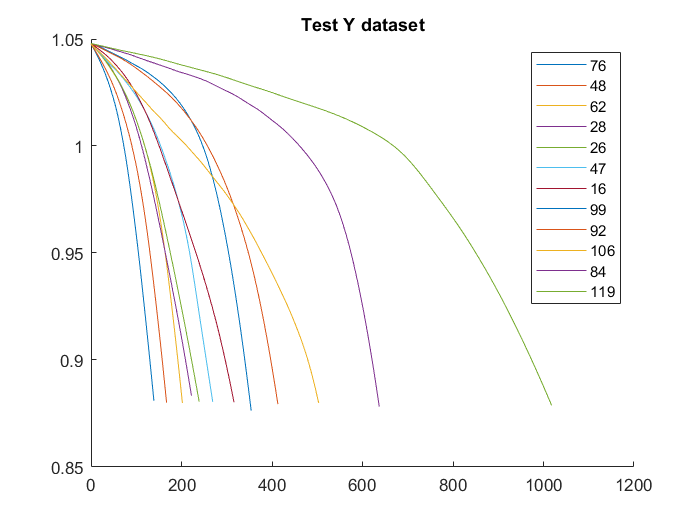


nLines = length(idxTest);
legend_str = cell(nLines,1);

figure
hold on 
for j = 1 : idxTestCount
    i = idxTest(j);
    plot(ryan4_battery_dataset(i).cycle,ryan4_battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i ryan4_battery_dataset(i).cycle_life];
    legend_str{j} = num2str(i);
end
hold off
title 'Test Y dataset'
legend(legend_str)

cycle_life_list

cycle_life_list = 12×3
     1    76   140
     2    48   168
     3    62   203
     4    28   222
     5    26   239
     6    47   270
     7    16   316
     8    99   355
     9    92   414
    10   106   504


battery_testset_org = zeros();
battery_testset_org = ryan4_battery_dataset(idxTest(1));
idxTestCount = length(idxTest)

idxTestCount = 12

idxTestStopCount = idxTestCount / 2 

idxTestStopCount = 6

idxTestReverse = idxTestCount

idxTestReverse = 12

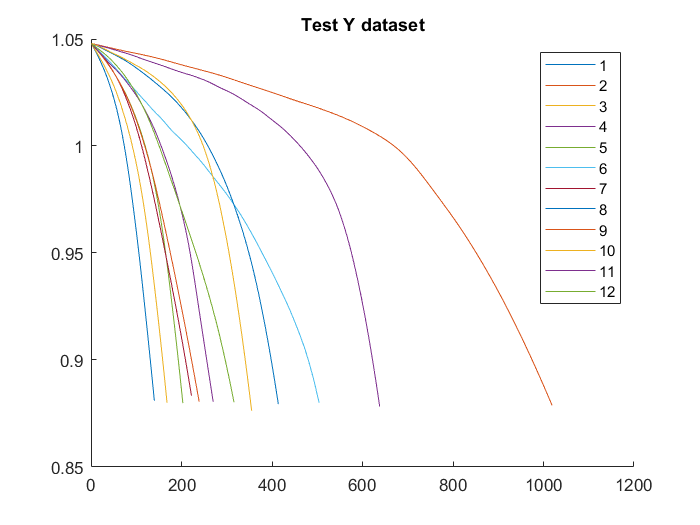

k = 1;
kk = idxTestCount;
for j = 1 : idxTestStopCount
    pre = idxTest(j);
    post = idxTest(idxTestReverse);
    idxTestReverse = idxTestReverse - 1;
    battery_testset_org(k,:) = ryan4_battery_dataset(pre);
    k=k+1;
    battery_testset_org(k,:) = ryan4_battery_dataset(post);
    k=k+1;
end

cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

nLines = size(battery_testset_org,1);
legend_str = cell(nLines,1);
figure
hold on 
for i = 1 : nLines
    %plot(battery_testset(i).cycle,battery_testset(i).QDischargeSmooth)
    plot(battery_testset_org(i).QDischargeSmooth)
    cycle_life_list(i,:) = [i i battery_testset_org(i).cycle_life];
    legend_str{i} = num2str(i);
end

hold off
title 'Test Y dataset'
legend(legend_str)

cycle_life_list_org = cycle_life_list

cycle_life_list_org = 12×3
           1           1         140
           2           2        1019
           3           3         168
           4           4         638
           5           5         203
           6           6         504
           7           7         222
           8           8         414
           9           9         239
          10          10         355


battery_testset = zeros();
battery_testset = ryan4_battery_dataset(idxTest(1));
%bat_pre = ryan4_battery_dataset(idxTest(1))
%bat_post = ryan4_battery_dataset(idxTest(12))
%battery_testset = bat_pre

idxTestCount = length(idxTest)

idxTestCount = 12

idxTestStopCount = idxTestCount / 2 

idxTestStopCount = 6

idxTestReverse = idxTestCount

idxTestReverse = 12

k = 1;
kk = idxTestCount;
for j = 1 : idxTestStopCount
    pre = idxTest(j);
    post = idxTest(idxTestReverse);
    idxTestReverse = idxTestReverse - 1;
    
    %ryan4_battery_dataset(pre).QDischargeSmooth
    %cycle_life_list(j,:) = [j pre ryan4_battery_dataset(pre).cycle_life];
    %legend_str{j} = num2str(pre);
    
    [idxPre] = find(ryan4_battery_dataset(pre).QDischargeSmooth >= 1,1,'last');
    [idxPost] = find(ryan4_battery_dataset(post).QDischargeSmooth >= 1,1,'last' );
    idxPost = idxPost + 1;
    idxPreAfter = idxPre + 1;
    idxPreBefore = idxPre ;
    idxPostBefore = idxPost -1;
    idxPostAfter = idxPost ;
    
    battery_testset(k,:) = ryan4_battery_dataset(pre);
    
    battery_testset(k).IR([idxPreAfter:end],:) = [] ;
    battery_testset(k).QCharge([idxPreAfter:end],:) = [] ;
    battery_testset(k).QDischarge([idxPreAfter:end],:) = [] ;
    battery_testset(k).SOH_c([idxPreAfter:end],:) = [] ;
    battery_testset(k).SOH_d([idxPreAfter:end],:) = [] ;
    battery_testset(k).Time_c([idxPreAfter:end],:) = [] ;
    battery_testset(k).Time_d([idxPreAfter:end],:) = [] ;
    battery_testset(k).Time_d1([idxPreAfter:end],:) = [] ;    
    battery_testset(k).Tavg([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tmin([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tmax([idxPreAfter:end],:) = [] ;

    battery_testset(k).Vc([idxPreAfter:end],:) = [] ;
    battery_testset(k).Vd([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tc([idxPreAfter:end],:) = [] ;
    battery_testset(k).Td([idxPreAfter:end],:) = [] ;
    battery_testset(k).Ic([idxPreAfter:end],:) = [] ;
    battery_testset(k).Id([idxPreAfter:end],:) = [] ;
    
    battery_testset(k).discharge_dQdV([idxPreAfter:end],:) = [] ;
    battery_testset(k).Qdlin([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tdlin([idxPreAfter:end],:) = [] ;
    
    battery_testset(k).chargetime([idxPreAfter:end],:) = [] ;
    battery_testset(k).QDischargeSmooth([idxPreAfter:end],:) = [] ;
    
    battery_testset(k).IR = vertcat(battery_testset(k).IR,ryan4_battery_dataset(post).IR([idxPost:end],:)) ;
    battery_testset(k).QCharge = vertcat(battery_testset(k).QCharge,ryan4_battery_dataset(post).QCharge([idxPost:end],:)) ;
    battery_testset(k).QDischarge = vertcat(battery_testset(k).QDischarge,ryan4_battery_dataset(post).QDischarge([idxPost:end],:)) ;
    battery_testset(k).SOH_c = vertcat(battery_testset(k).SOH_c,ryan4_battery_dataset(post).SOH_c([idxPost:end],:)) ;
    battery_testset(k).SOH_d = vertcat(battery_testset(k).SOH_d,ryan4_battery_dataset(post).SOH_d([idxPost:end],:)) ;
    battery_testset(k).Time_c = vertcat(battery_testset(k).Time_c,ryan4_battery_dataset(post).Time_c([idxPost:end],:)) ;
    battery_testset(k).Time_d = vertcat(battery_testset(k).Time_d,ryan4_battery_dataset(post).Time_d([idxPost:end],:)) ;
    battery_testset(k).Time_d1 = vertcat(battery_testset(k).Time_d1,ryan4_battery_dataset(post).Time_d1([idxPost:end],:)) ;
    battery_testset(k).Tavg = vertcat(battery_testset(k).Tavg,ryan4_battery_dataset(post).Tavg([idxPost:end],:)) ;
    battery_testset(k).Tmin = vertcat(battery_testset(k).Tmin,ryan4_battery_dataset(post).Tmin([idxPost:end],:)) ;
    battery_testset(k).Tmax = vertcat(battery_testset(k).Tmax,ryan4_battery_dataset(post).Tmax([idxPost:end],:)) ;
    battery_testset(k).Vc = vertcat(battery_testset(k).Vc,ryan4_battery_dataset(post).Vc([idxPost:end],:)) ;
    battery_testset(k).Vd = vertcat(battery_testset(k).Vd,ryan4_battery_dataset(post).Vd([idxPost:end],:)) ;
    battery_testset(k).Tc = vertcat(battery_testset(k).Tc,ryan4_battery_dataset(post).Tc([idxPost:end],:)) ;
    battery_testset(k).Td = vertcat(battery_testset(k).Td,ryan4_battery_dataset(post).Td([idxPost:end],:)) ;
    battery_testset(k).Ic = vertcat(battery_testset(k).Ic,ryan4_battery_dataset(post).Ic([idxPost:end],:)) ;
    battery_testset(k).Id = vertcat(battery_testset(k).Id,ryan4_battery_dataset(post).Id([idxPost:end],:)) ;
    
    battery_testset(k).discharge_dQdV = vertcat(battery_testset(k).discharge_dQdV,ryan4_battery_dataset(post).discharge_dQdV([idxPost:end],:)) ;
    battery_testset(k).Qdlin = vertcat(battery_testset(k).Qdlin,ryan4_battery_dataset(post).Qdlin([idxPost:end],:)) ;
    battery_testset(k).Tdlin = vertcat(battery_testset(k).Tdlin,ryan4_battery_dataset(post).Tdlin([idxPost:end],:)) ;
    
    battery_testset(k).chargetime = vertcat(battery_testset(k).chargetime,ryan4_battery_dataset(post).chargetime([idxPost:end],:)) ;
    battery_testset(k).QDischargeSmooth = vertcat(battery_testset(k).QDischargeSmooth,ryan4_battery_dataset(post).QDischargeSmooth([idxPost:end],:)) ;
    
    battery_testset(k).cycle_life = idxPre +  (ryan4_battery_dataset(post).cycle_life - idxPost  ) + 1 ;
    battery_testset(k).cycle = [];
    battery_testset(k).cycle = linspace(1,battery_testset(k).cycle_life,battery_testset(k).cycle_life) ;

    battery_testset(k).QDischargePolyMdl = [];
%    battery_testset(k).QDischargePolyMdl = polyfit(battery_testset(k).cycle, battery_testset(k).QDischargeSmooth,4);
    battery_testset(k).QDischargePolyfit = [];
%    battery_testset(k).QDischargePolyfit = polyval(battery_testset.QDischargePolyMdl,battery_testset.cycle')';

%%%%%%%%%%%%%%%
    k = k+1;
    battery_testset(k,:) = ryan4_battery_dataset(post);
    
    battery_testset(k).IR([idxPostAfter:end],:) = [] ;
    battery_testset(k).QCharge([idxPostAfter:end],:) = [] ;
    battery_testset(k).QDischarge([idxPostAfter:end],:) = [] ;
    battery_testset(k).SOH_c([idxPostAfter:end],:) = [] ;
    battery_testset(k).SOH_d([idxPostAfter:end],:) = [] ;
    battery_testset(k).Time_c([idxPostAfter:end],:) = [] ;
    battery_testset(k).Time_d([idxPostAfter:end],:) = [] ;
    battery_testset(k).Time_d1([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tavg([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tavg([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tmin([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tmax([idxPostAfter:end],:) = [] ;
    battery_testset(k).Vc([idxPostAfter:end],:) = [] ;
    battery_testset(k).Vd([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tc([idxPostAfter:end],:) = [] ;
    battery_testset(k).Td([idxPostAfter:end],:) = [] ;
    battery_testset(k).Ic([idxPostAfter:end],:) = [] ;
    battery_testset(k).Id([idxPostAfter:end],:) = [] ;
    
    battery_testset(k).discharge_dQdV([idxPostAfter:end],:) = [] ;
    battery_testset(k).Qdlin([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tdlin([idxPostAfter:end],:) = [] ;
    
    battery_testset(k).chargetime([idxPostAfter:end],:) = [] ;
    battery_testset(k).QDischargeSmooth([idxPostAfter:end],:) = [] ;
    
    battery_testset(k).IR = vertcat(battery_testset(k).IR,ryan4_battery_dataset(pre).IR([idxPreAfter:end],:)) ;
    battery_testset(k).QCharge = vertcat(battery_testset(k).QCharge,ryan4_battery_dataset(pre).QCharge([idxPreAfter:end],:)) ;
    battery_testset(k).QDischarge = vertcat(battery_testset(k).QDischarge,ryan4_battery_dataset(pre).QDischarge([idxPreAfter:end],:)) ;
    battery_testset(k).SOH_c = vertcat(battery_testset(k).SOH_c,ryan4_battery_dataset(pre).SOH_c([idxPreAfter:end],:)) ;
    battery_testset(k).SOH_d = vertcat(battery_testset(k).SOH_d,ryan4_battery_dataset(pre).SOH_d([idxPreAfter:end],:)) ;
    battery_testset(k).Time_c = vertcat(battery_testset(k).Time_c,ryan4_battery_dataset(pre).Time_c([idxPreAfter:end],:)) ;
    battery_testset(k).Time_d = vertcat(battery_testset(k).Time_d,ryan4_battery_dataset(pre).Time_d([idxPreAfter:end],:)) ;
    battery_testset(k).Time_d1 = vertcat(battery_testset(k).Time_d1,ryan4_battery_dataset(pre).Time_d1([idxPreAfter:end],:)) ;
    battery_testset(k).Tavg = vertcat(battery_testset(k).Tavg,ryan4_battery_dataset(pre).Tavg([idxPreAfter:end],:)) ;
    battery_testset(k).Tmin = vertcat(battery_testset(k).Tmin,ryan4_battery_dataset(pre).Tmin([idxPreAfter:end],:)) ;
    battery_testset(k).Tmax = vertcat(battery_testset(k).Tmax,ryan4_battery_dataset(pre).Tmax([idxPreAfter:end],:)) ;
    battery_testset(k).Vc = vertcat(battery_testset(k).Vc,ryan4_battery_dataset(pre).Vc([idxPreAfter:end],:)) ;
    battery_testset(k).Vd = vertcat(battery_testset(k).Vd,ryan4_battery_dataset(pre).Vd([idxPreAfter:end],:)) ;
    battery_testset(k).Tc = vertcat(battery_testset(k).Tc,ryan4_battery_dataset(pre).Tc([idxPreAfter:end],:)) ;
    battery_testset(k).Td = vertcat(battery_testset(k).Td,ryan4_battery_dataset(pre).Td([idxPreAfter:end],:)) ;
    battery_testset(k).Ic = vertcat(battery_testset(k).Ic,ryan4_battery_dataset(pre).Ic([idxPreAfter:end],:)) ;
    battery_testset(k).Id = vertcat(battery_testset(k).Id,ryan4_battery_dataset(pre).Id([idxPreAfter:end],:)) ;
    
    battery_testset(k).discharge_dQdV = vertcat(battery_testset(k).discharge_dQdV,ryan4_battery_dataset(pre).discharge_dQdV([idxPreAfter:end],:)) ;
    battery_testset(k).Qdlin = vertcat(battery_testset(k).Qdlin,ryan4_battery_dataset(pre).Qdlin([idxPreAfter:end],:)) ;
    battery_testset(k).Tdlin = vertcat(battery_testset(k).Tdlin,ryan4_battery_dataset(pre).Tdlin([idxPreAfter:end],:)) ;   
     
    battery_testset(k).chargetime = vertcat(battery_testset(k).chargetime,ryan4_battery_dataset(pre).chargetime([idxPreAfter:end],:)) ;
    battery_testset(k).QDischargeSmooth = vertcat(battery_testset(k).QDischargeSmooth,ryan4_battery_dataset(pre).QDischargeSmooth([idxPreAfter:end],:)) ;
    
    battery_testset(k).cycle_life = idxPost +  (ryan4_battery_dataset(pre).cycle_life - idxPre  ) + 1 ;
    battery_testset(k).cycle = [];
    battery_testset(k).cycle = linspace(1,battery_testset(k).cycle_life,battery_testset(k).cycle_life) ;

    battery_testset(k).QDischargePolyMdl = [];
%    battery_testset(k).QDischargePolyMdl = polyfit(battery_testset(k).cycle, battery_testset(k).QDischargeSmooth,4);
    battery_testset(k).QDischargePolyfit = [];
%    battery_testset(k).QDischargePolyfit = polyval(battery_testset.QDischargePolyMdl,battery_testset.cycle')';
    k = k +1;
end
%battery_testset



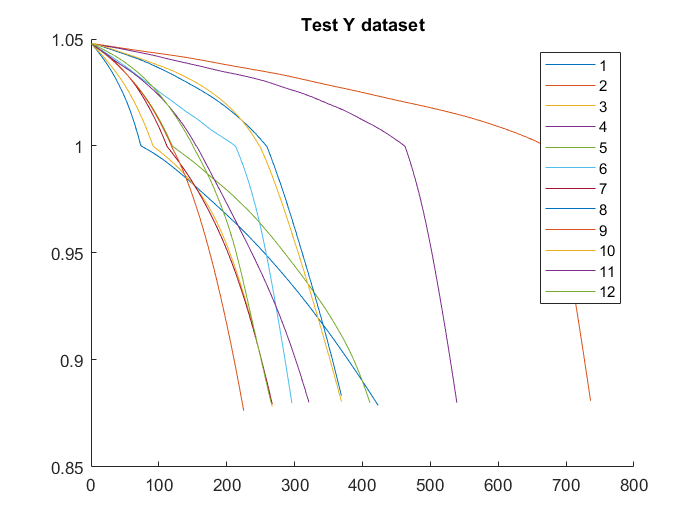


cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

nLines = size(battery_testset,1);
legend_str = cell(nLines,1);
figure
hold on 
for i = 1 : nLines
    %plot(battery_testset(i).cycle,battery_testset(i).QDischargeSmooth)
    plot(battery_testset(i).QDischargeSmooth)
    cycle_life_list(i,:) = [i i battery_testset(i).cycle_life];
    legend_str{i} = num2str(i);
end

hold off
title 'Test Y dataset'
legend(legend_str)

cycle_life_list_change = cycle_life_list

cycle_life_list_change =      1     1   423
     2     2   738
     3     3   267
     4     4   541
     5     5   411
     6     6   298
     7     7   267
     8     8   371
     9     9   225
    10    10   371


%{
cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

nLines = length(idxTestSort);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTestSort)
    i = idxTestSort(j);
    plot(ryan4_battery_dataset(i).cycle,ryan4_battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i ryan4_battery_dataset(i).cycle_life];
    legend_str{j} = num2str(i);
end

hold off
title 'Test Y dataset'
legend(legend_str)
cycle_life_list
%}


save('ryan4_data.mat','battery_testset' )
save('ryan4_data.mat','battery_testset_org' ,'-append')

% load ryan4_gen_data.mat

첫번째 cycle의 충전전류를 얻는다.

idx = 1; % idxAll; 

ryan4_battery_dataset(idx).Ic

ans =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999
    4.4001    4.3999    4.4002    4.3998    4.4002    4.3995    4.4002    4.4000    4.4004    4.4002    4.3999    4.3991    4.3999    4.4001    4.4000    4.4001    4.4000    4.3999    4.4002    4.4003    4.4003    4.3999    4.4002    4.3999    4.4000    4.4001    4.4000    4.4000    4.4000    4.3999    4.4000    4.4000    4.4000    4.4001    4.4002    4.3998    4.3999    4.3997    4.4005    4.3995    4.4000    4.4001    4.4000    4.3998    4.4000    4.3999    4.4000    4.4001    4.4002   

ryan4_battery_dataset(idx).Ic(1,:)

ans =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999


% 열벡터로 바꾼다.
Ic1 = ryan4_battery_dataset(idx).Ic(1,:)'

Ic1 =     4.4001
    4.3999
    4.4005
    4.4008
    4.3997
    4.3999
    4.4003
    4.4000
    4.3999
    4.4007


% 전체 데이타에 대해서 
IcFirstFull = zeros()

IcFirstFull = 0

IcFirstFull = ryan4_battery_dataset(1).Ic(1,:)

IcFirstFull =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999



VdFirstFull = zeros()

VdFirstFull = 0

VdFirstFull = ryan4_battery_dataset(1).Vd(1,:)

VdFirstFull =     3.2974    3.2346    3.2033    3.1864    3.1762    3.1695    3.1647    3.1611    3.1577    3.1550    3.1523    3.1500    3.1480    3.1458    3.1436    3.1417    3.1397    3.1376    3.1356    3.1336    3.1315    3.1295    3.1275    3.1253    3.1232    3.1209    3.1188    3.1165    3.1142    3.1117    3.1093    3.1069    3.1044    3.1020    3.0993    3.0968    3.0942    3.0915    3.0888    3.0860    3.0832    3.0804    3.0775    3.0746    3.0716    3.0684    3.0652    3.0619    3.0584    3.0549



%IcFirstFull = ryan4_battery_dataset(2).Ic(1,:)
for i=1:length(ryan4_battery_dataset)
    IcFirstFull(i,:) = ryan4_battery_dataset(i).Ic(1,:);
    VdFirstFull(i,:) = ryan4_battery_dataset(i).Vd(1,:);
end
IcFirstFull

IcFirstFull =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999
    4.8000    4.8000    4.8000    4.7999    4.8001    4.8000    4.8001    4.8001    4.8001    4.8001    4.7998    4.8003    4.8000    4.8000    4.8001    4.8000    4.7998    4.8000    4.7999    4.7998    4.8000    4.7998    4.8001    4.8001    4.8000    4.7998    4.8000    4.8003    4.8001    4.8000    4.8001    4.8001    4.7999    4.8001    4.8000    4.8000    4.8003    4.8001    4.8000    4.8000    4.7999    4.7998    4.8001    4.8000    4.8003    4.8001    4.8001    4.8002    4

VdFirstFull

VdFirstFull =     3.2974    3.2346    3.2033    3.1864    3.1762    3.1695    3.1647    3.1611    3.1577    3.1550    3.1523    3.1500    3.1480    3.1458    3.1436    3.1417    3.1397    3.1376    3.1356    3.1336    3.1315    3.1295    3.1275    3.1253    3.1232    3.1209    3.1188    3.1165    3.1142    3.1117    3.1093    3.1069    3.1044    3.1020    3.0993    3.0968    3.0942    3.0915    3.0888    3.0860    3.0832    3.0804    3.0775    3.0746    3.0716    3.0684    3.0652    3.0619    3.0584    3.0549
    3.2991    3.2361    3.2046    3.1877    3.1774    3.1708    3.1659    3.1620    3.1587    3.1559    3.1532    3.1508    3.1485    3.1464    3.1442    3.1421    3.1399    3.1379    3.1358    3.1337    3.1316    3.1295    3.1272    3.1251    3.1227    3.1205    3.1182    3.1157    3.1133    3.1109    3.1085    3.1058    3.1033    3.1006    3.0980    3.0953    3.0925    3.0898    3.0870    3.0843    3.0812    3.0782    3.0753    3.0723    3.0690    3.0659    3.0626    3.0591    3

%IcFirstFull = IcFirstFull'
RulFirst = [ryan4_battery_dataset(idxAll).cycle_life ]'

RulFirst =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))


IcFirst = blockproc(IcFirstFull, blockSize, meanFilterFunction)

IcFirst =     4.4002    4.4002    4.4000    4.4002    4.4000    4.3999    4.3999    4.4000    4.3999    4.4001    4.4000    4.4000    4.3998    4.4001    2.8830    0.9999    1.0000    0.2486         0         0
    4.8000    4.8001    4.8000    4.7999    4.8000    4.8000    4.8000    4.8001    4.8000    4.8001    4.8000    4.8001    4.8001    4.4818    3.3432    1.0001    0.9999    0.1944         0         0
    4.8000    4.8000    4.7999    4.8000    4.8000    4.8000    4.8000    4.8000    4.8001    4.8000    4.7999    4.7999    4.7999    4.5428    3.2030    1.0000    1.0000    0.1975         0         0
    5.4000    5.3999    5.3998    5.3999    5.4002    5.4000    5.3997    4.3203    3.6000    3.6001    3.6000    3.6000    3.5999    3.6000    2.4843    1.0001    1.0000    0.2434         0         0
    5.3991    5.4004    5.3996    5.4003    5.3998    5.4004    5.4000    5.4001    5.4001    3.4802    2.9999    3.0000    3.0000    3.0000    2.1265    1.0001    1.0000    0.2224      

VdFirst = blockproc(VdFirstFull, blockSize, meanFilterFunction)

VdFirst =     3.2196    3.1616    3.1480    3.1376    3.1274    3.1164    3.1044    3.0915    3.0775    3.0618    3.0430    3.0193    2.9873    2.9403    2.8626    2.7141    2.3617    1.9999    1.9999    1.9999
    3.2210    3.1627    3.1486    3.1379    3.1272    3.1157    3.1032    3.0898    3.0752    3.0590    3.0393    3.0143    2.9807    2.9318    2.8535    2.7101    2.4012    1.9997    1.9997    1.9997
    3.2243    3.1647    3.1502    3.1395    3.1291    3.1180    3.1061    3.0930    3.0786    3.0623    3.0428    3.0180    2.9838    2.9316    2.8403    2.6536    2.2249    2.0000    2.0001    2.0001
    3.2252    3.1664    3.1529    3.1429    3.1330    3.1224    3.1109    3.0982    3.0845    3.0694    3.0516    3.0291    2.9986    2.9527    2.8755    2.7216    2.3358    1.9997    1.9997    1.9997
    3.2307    3.1771    3.1643    3.1540    3.1438    3.1328    3.1208    3.1078    3.0941    3.0795    3.0627    3.0419    3.0150    2.9765    2.9134    2.7898    2.4864    2.0033    2.

%RulFirst = cycleLife;
%clear cycleLife


[ynorm_IcFirst_RUL,ymax_IcFirst_RUL,ymin_IcFirst_RUL,yrate_IcFirst_RUL,xnorm_IcFirstFull_RUL,xmax_IcFirst_RUL,xmin_IcFirst_RUL,xrate_IcFirst_RUL] = ...
minmax_norm_new(RulFirst,IcFirstFull);
[ynorm_IcFirst_RUL1,xnorm_IcFirst_RUL] = minmax_norm_new_with_param(RulFirst,IcFirst,ymin_IcFirst_RUL,yrate_IcFirst_RUL,xmin_IcFirst_RUL,xrate_IcFirst_RUL);
% https://stackoverflow.com/questions/40053450/compare-if-two-vectors-are-the-same
returnsTrue = all(ynorm_IcFirst_RUL == ynorm_IcFirst_RUL1)

returnsTrue = logical
   1


[ynorm_VdFirst_RUL,ymax_VdFirst_RUL,ymin_VdFirst_RUL,yrate_VdFirst_RUL,xnorm_VdFirst_RUL,xmax_VdFirst_RUL,xmin_VdFirst_RUL,xrate_VdFirst_RUL] = ...
minmax_norm_new(RulFirst,VdFirst);

all(ynorm_IcFirst_RUL == ynorm_VdFirst_RUL)

ans = logical
   1


all(ymax_IcFirst_RUL == ymax_VdFirst_RUL)

ans = logical
   1


all(ymin_IcFirst_RUL == ymin_VdFirst_RUL)

ans = logical
   1


all(yrate_IcFirst_RUL == yrate_VdFirst_RUL)

ans = logical
   1



ynorm_First_RUL = ynorm_IcFirst_RUL

ynorm_First_RUL =     0.3004
    0.1130
    0.1356
    0.2156
    0.2891
    0.2090
    0.1591
    0.1186
    0.1648
    0.3324


ymax_First_RUL = ymax_IcFirst_RUL

ymax_First_RUL = 1171

ymin_First_RUL = ymin_IcFirst_RUL

ymin_First_RUL = 109

yrate_First_RUL = yrate_IcFirst_RUL

yrate_First_RUL = 1062

x_trainValid_IcFirstFull_RUL = xnorm_IcFirstFull_RUL([idxTrain idxValid],:);
x_test_IcFirstFull_RUL = xnorm_IcFirstFull_RUL([idxTest],:);
x_trainValid_IcFirst_RUL = xnorm_IcFirst_RUL([idxTrain idxValid],:);
x_test_IcFirst_RUL = xnorm_IcFirst_RUL([idxTest],:);

y_trainValid_IcFirst_RUL = ynorm_IcFirst_RUL([idxTrain idxValid]);
y_test_IcFirst_RUL = ynorm_IcFirst_RUL([idxTest]);
Y_trainValid_IcFirst_RUL = RulFirst([idxTrain idxValid]);
Y_test_IcFirst_RUL = RulFirst([idxTest]);


x_trainValid_VdFirst_RUL = xnorm_VdFirst_RUL([idxTrain idxValid],:);
x_test_VdFirst_RUL = xnorm_VdFirst_RUL([idxTest],:);

y_trainValid_VdFirst_RUL = ynorm_VdFirst_RUL([idxTrain idxValid]);
y_test_VdFirst_RUL = ynorm_VdFirst_RUL([idxTest]);
Y_trainValid_VdFirst_RUL = RulFirst([idxTrain idxValid]);
Y_test_VdFirst_RUL = RulFirst([idxTest]);

all(y_trainValid_IcFirst_RUL == y_trainValid_VdFirst_RUL)

ans = logical
   1


all(y_test_IcFirst_RUL == y_test_VdFirst_RUL)

ans = logical
   1


all(Y_trainValid_IcFirst_RUL == Y_trainValid_VdFirst_RUL)

ans = logical
   1


all(Y_test_IcFirst_RUL == Y_test_VdFirst_RUL)

ans = logical
   1



y_trainValid_First_RUL = y_trainValid_IcFirst_RUL ;
y_test_First_RUL = y_test_IcFirst_RUL ;
Y_trainValid_First_RUL = Y_trainValid_IcFirst_RUL ;
Y_test_First_RUL = Y_test_IcFirst_RUL ;


# 변수 추출

Cap = zeros();
%SOH = zeros();
% = zeeros();
VdFull = zeros();
%VdFull = [1:100];
ryan4_battery_dataset(1).QDischargeSmooth

ans =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


ryan4_battery_dataset(1).Vd

ans =     3.2974    3.2346    3.2033    3.1864    3.1762    3.1695    3.1647    3.1611    3.1577    3.1550    3.1523    3.1500    3.1480    3.1458    3.1436    3.1417    3.1397    3.1376    3.1356    3.1336    3.1315    3.1295    3.1275    3.1253    3.1232    3.1209    3.1188    3.1165    3.1142    3.1117    3.1093    3.1069    3.1044    3.1020    3.0993    3.0968    3.0942    3.0915    3.0888    3.0860    3.0832    3.0804    3.0775    3.0746    3.0716    3.0684    3.0652    3.0619    3.0584    3.0549
    3.2967    3.2340    3.2026    3.1858    3.1756    3.1692    3.1643    3.1604    3.1574    3.1545    3.1520    3.1497    3.1475    3.1453    3.1433    3.1413    3.1392    3.1373    3.1353    3.1333    3.1313    3.1293    3.1272    3.1249    3.1229    3.1205    3.1184    3.1162    3.1137    3.1115    3.1091    3.1067    3.1042    3.1017    3.0990    3.0965    3.0939    3.0913    3.0885    3.0858    3.0831    3.0802    3.0772    3.0743    3.0712    3.0682    3.0649    3.0617    3.0581   

size(ryan4_battery_dataset(1).QDischargeSmooth)

ans =    428     1


length(ryan4_battery_dataset(1).QDischargeSmooth)

ans = 428


idxAll = (1:length(ryan4_battery_dataset));
idxTrainValid = [ idxTrain idxValid ];
idxTrainAll = []; %zeros();
idxValidAll = []; %zeros();
idxTestAll = []; %zeros();
idxTrainAll_batIndex = []; %zeros();
idxValidAll_batIndex = []; %zeros();
idxTestAll_batIndex = []; %zeros();

j =1;
startIndx = j ;
GenerateFrameList = @(A,S,N) A+S*(0:N-1);

for i = 1: length(idxAll)
        
    cap_temp = ryan4_battery_dataset(i).QDischargeSmooth;
    %SOH_temp = max(cap_temp);
    RUL_temp = linspace(ryan4_battery_dataset(i).cycle_life,1,ryan4_battery_dataset(i).cycle_life)';
    leng = length(cap_temp);
    %startIndx = j ;
    % https://kr.mathworks.com/matlabcentral/answers/478553-how-can-i-have-a-starting-number-a-step-size-then-the-number-of-numbers-i-need-in-a-1d-array
    append_index = GenerateFrameList(startIndx,1,leng);
    
    Vd_temp = ryan4_battery_dataset(i).Vd ;
    Ic_temp = ryan4_battery_dataset(i).Ic ;
    batIndex_temp(1:leng, 1) = i;
    %VdFull = [VdFull ; Vd_temp];
    if  i == 1
        VdFull = Vd_temp;
        Cap = cap_temp; 
        IcFull = Ic_temp;
        RUL = RUL_temp;
        %SOH =
    else
        VdFull = vertcat(VdFull,Vd_temp);
        Cap = vertcat(Cap,cap_temp);
        IcFull = vertcat(IcFull,Ic_temp);
        RUL = vertcat(RUL,RUL_temp);
    end
       
    
    if any(idxTrain(:) == i) 
       % https://kr.mathworks.com/matlabcentral/answers/283821-add-single-element-to-array-or-vector
       idxTrainAll =  [idxTrainAll append_index ] ;
       idxTrainAll_batIndex = [idxTrainAll_batIndex batIndex_temp'];
    end
    if any(idxValid(:) == i) 
       idxValidAll =  [idxValidAll append_index ] ;
       idxValidAll_batIndex = [idxValidAll_batIndex batIndex_temp'];
    end
    if any(idxTest(:) == i) 
       idxTestAll =  [idxTestAll append_index ] ;
       idxTestAll_batIndex = [idxTestAll_batIndex batIndex_temp'];
    end
    %VdFull(i) = Vd_temp;
    
    startIndx = startIndx + leng;
end


idxTrainAll

idxTrainAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxValidAll

idxValidAll =         2793        2794        2795        2796        2797        2798        2799        2800        2801        2802        2803        2804        2805        2806        2807        2808        2809        2810        2811        2812        2813        2814        2815        2816        2817        2818        2819        2820        2821        2822        2823        2824        2825        2826        2827        2828        2829        2830        2831        2832        2833        2834        2835        2836        2837        2838        2839        2840        2841        2842


idxTestAll

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


Cap

Cap =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


VdFull

VdFull =     3.2974    3.2346    3.2033    3.1864    3.1762    3.1695    3.1647    3.1611    3.1577    3.1550    3.1523    3.1500    3.1480    3.1458    3.1436    3.1417    3.1397    3.1376    3.1356    3.1336    3.1315    3.1295    3.1275    3.1253    3.1232    3.1209    3.1188    3.1165    3.1142    3.1117    3.1093    3.1069    3.1044    3.1020    3.0993    3.0968    3.0942    3.0915    3.0888    3.0860    3.0832    3.0804    3.0775    3.0746    3.0716    3.0684    3.0652    3.0619    3.0584    3.0549
    3.2967    3.2340    3.2026    3.1858    3.1756    3.1692    3.1643    3.1604    3.1574    3.1545    3.1520    3.1497    3.1475    3.1453    3.1433    3.1413    3.1392    3.1373    3.1353    3.1333    3.1313    3.1293    3.1272    3.1249    3.1229    3.1205    3.1184    3.1162    3.1137    3.1115    3.1091    3.1067    3.1042    3.1017    3.0990    3.0965    3.0939    3.0913    3.0885    3.0858    3.0831    3.0802    3.0772    3.0743    3.0712    3.0682    3.0649    3.0617    3.0581

IcFull

IcFull =     4.4001    4.3999    4.4005    4.4008    4.3997    4.3999    4.4003    4.4000    4.3999    4.4007    4.4002    4.4000    4.4000    4.3996    4.4000    4.3999    4.4006    4.4004    4.4001    4.3999    4.4001    4.4001    4.3996    4.3999    4.4000    4.3997    4.4000    4.3999    4.3999    4.4000    4.4000    4.4000    4.3999    4.3997    4.3999    4.4001    4.3998    4.3994    4.4008    4.3999    4.3997    4.4001    4.4003    4.3996    4.4001    4.4000    4.4000    4.3999    4.4008    4.3999
    4.4001    4.3999    4.4002    4.3998    4.4002    4.3995    4.4002    4.4000    4.4004    4.4002    4.3999    4.3991    4.3999    4.4001    4.4000    4.4001    4.4000    4.3999    4.4002    4.4003    4.4003    4.3999    4.4002    4.3999    4.4000    4.4001    4.4000    4.4000    4.4000    4.3999    4.4000    4.4000    4.4000    4.4001    4.4002    4.3998    4.3999    4.3997    4.4005    4.3995    4.4000    4.4001    4.4000    4.3998    4.4000    4.3999    4.4000    4.4001    4.4002

% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))



Ic = blockproc(IcFull, blockSize, meanFilterFunction)

Ic =     4.4002    4.4002    4.4000    4.4002    4.4000    4.3999    4.3999    4.4000    4.3999    4.4001    4.4000    4.4000    4.3998    4.4001    2.8830    0.9999    1.0000    0.2486         0         0
    4.4000    4.4001    4.3998    4.4001    4.4001    4.4000    4.4001    4.3999    4.4000    4.4001    4.3999    4.4002    4.4000    4.3999    3.5301    1.0000    1.0000    0.2441         0         0
    4.4002    4.3999    4.3997    4.3999    4.3999    4.3999    4.4001    4.3999    4.4000    4.4000    4.3999    4.3999    4.3999    4.4000    3.5213    1.0000    1.0001    0.2455         0         0
    4.3999    4.4001    4.3999    4.4000    4.4001    4.4000    4.4000    4.3999    4.4000    4.4001    4.4000    4.4002    4.4001    4.4000    3.2207    0.9999    1.0000    0.2351         0         0
    4.3998    4.4001    4.4001    4.4001    4.4003    4.4000    4.3999    4.4000    4.4000    4.4000    4.3996    4.4000    4.3997    4.4000    3.1733    1.0002    1.0000    0.2350         0 

%clear IcFull  

Vd = blockproc(VdFull, blockSize, meanFilterFunction)

Vd =     3.2196    3.1616    3.1480    3.1376    3.1274    3.1164    3.1044    3.0915    3.0775    3.0618    3.0430    3.0193    2.9873    2.9403    2.8626    2.7141    2.3617    1.9999    1.9999    1.9999
    3.2189    3.1612    3.1476    3.1373    3.1271    3.1161    3.1041    3.0912    3.0772    3.0615    3.0427    3.0190    2.9870    2.9400    2.8623    2.7139    2.3606    1.9998    1.9999    1.9999
    3.2198    3.1619    3.1482    3.1378    3.1275    3.1165    3.1045    3.0915    3.0775    3.0617    3.0430    3.0193    2.9872    2.9401    2.8621    2.7126    2.3576    1.9999    2.0000    2.0000
    3.2194    3.1614    3.1478    3.1375    3.1272    3.1162    3.1042    3.0912    3.0772    3.0615    3.0428    3.0190    2.9870    2.9398    2.8618    2.7126    2.3529    2.0001    2.0004    2.0004
    3.2192    3.1612    3.1477    3.1374    3.1272    3.1162    3.1042    3.0913    3.0773    3.0616    3.0429    3.0191    2.9871    2.9400    2.8620    2.7127    2.3598    1.9999    2.0000 

%clear VdFull  


ryan4_gen_data_raw_desc = "ryan4_gen_data_raw_desc";
%save('ryan4_data_raw.mat','ryan4_gen_data_raw_desc');
save('ryan4_data_raw.mat','ryan4_battery_dataset','-append');



% https://stackoverflow.com/questions/39149677/how-to-delete-a-variable-from-mat-file-in-matlab
%rmmatvar('ryan4_gen_data.mat', 'ryan4_battery_dataset');

%clear ryan4_battery_dataset


[ynorm_Ic_RUL,ymax_Ic_RUL,ymin_Ic_RUL,yrate_Ic_RUL,xnorm_Ic_RUL,xmax_Ic_RUL,xmin_Ic_RUL,xrate_Ic_RUL] = minmax_norm_new(RUL,Ic);
[ynorm_Vd_RUL,ymax_Vd_RUL,ymin_Vd_RUL,yrate_Vd_RUL,xnorm_Vd_RUL,xmax_Vd_RUL,xmin_Vd_RUL,xrate_Vd_RUL] = minmax_norm_new(RUL,Vd);

Y_trainValid_Ic_RUL = RUL([idxTrainAll idxValidAll],:);
Y_test_Ic_RUL = RUL([idxTestAll],:);
x_trainValid_Ic_RUL = xnorm_Ic_RUL([idxTrainAll idxValidAll],:)

x_trainValid_Ic_RUL =     0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4132    0.1976    0.1976    0.1115    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4874    0.1976    0.1976    0.1110    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4864    0.1976    0.1976    0.1111    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4519    0.1976    0.1976    0.1100    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5869    0.5870    0.5870    0.5870    0.4465    0.1976    0.1976    

x_test_Ic_RUL = xnorm_Ic_RUL([idxTestAll],:)

x_test_Ic_RUL =     0.7703    0.7703    0.7702    0.7703    0.7702    0.7703    0.7702    0.5641    0.4266    0.4266    0.4266    0.4266    0.4266    0.4267    0.3269    0.1976    0.1976    0.1103    0.0830    0.0830
    0.7703    0.7703    0.7702    0.7702    0.7702    0.7703    0.7702    0.5641    0.4266    0.4266    0.4266    0.4266    0.4266    0.4266    0.3266    0.1976    0.1976    0.1093    0.0830    0.0830
    0.7702    0.7702    0.7703    0.7703    0.7703    0.7702    0.7703    0.5641    0.4266    0.4266    0.4266    0.4266    0.4267    0.4266    0.3265    0.1976    0.1976    0.1093    0.0830    0.0830
    0.7703    0.7703    0.7702    0.7702    0.7703    0.7703    0.7703    0.5641    0.4267    0.4266    0.4266    0.4266    0.4266    0.4266    0.3267    0.1976    0.1976    0.1087    0.0830    0.0830
    0.7703    0.7703    0.7703    0.7703    0.7703    0.7702    0.7702    0.5641    0.4267    0.4266    0.4266    0.4266    0.4266    0.4266    0.3268    0.1976    0.1976    0.1084

y_trainValid_Ic_RUL = ynorm_Ic_RUL([idxTrainAll idxValidAll])

y_trainValid_Ic_RUL =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test_Ic_RUL = ynorm_Ic_RUL([idxTestAll])

y_test_Ic_RUL =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


Y_trainValid_Vd_RUL = RUL([idxTrainAll idxValidAll],:);
Y_test_Vd_RUL = RUL([idxTestAll],:);
x_trainValid_Vd_RUL = xnorm_Vd_RUL([idxTrainAll idxValidAll],:)

x_trainValid_Vd_RUL =     0.9175    0.8739    0.8637    0.8559    0.8482    0.8400    0.8309    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7076    0.6493    0.5376    0.2728    0.0009    0.0009    0.0009
    0.9170    0.8736    0.8634    0.8556    0.8480    0.8397    0.8307    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7074    0.6490    0.5375    0.2720    0.0009    0.0009    0.0009
    0.9177    0.8742    0.8638    0.8560    0.8483    0.8400    0.8310    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7075    0.6489    0.5365    0.2698    0.0009    0.0010    0.0010
    0.9173    0.8737    0.8635    0.8558    0.8481    0.8398    0.8308    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7072    0.6486    0.5365    0.2662    0.0011    0.0013    0.0013
    0.9172    0.8736    0.8635    0.8557    0.8480    0.8398    0.8308    0.8211    0.8106    0.7988    0.7847    0.7669    0.7428    0.7074    0.6488    0.5366    0.2714    

x_test_Vd_RUL = xnorm_Vd_RUL([idxTestAll],:)

x_test_Vd_RUL =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    0.0010

y_trainValid_Vd_RUL = ynorm_Vd_RUL([idxTrainAll idxValidAll])

y_trainValid_Vd_RUL =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test_Vd_RUL = ynorm_Vd_RUL([idxTestAll])

y_test_Vd_RUL =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615




all(Y_trainValid_Ic_RUL == Y_trainValid_Vd_RUL)

ans = logical
   1


all(Y_test_Ic_RUL == Y_test_Vd_RUL)

ans = logical
   1


all(y_trainValid_Ic_RUL == y_trainValid_Vd_RUL)

ans = logical
   1


all(y_test_Ic_RUL == y_test_Vd_RUL)

ans = logical
   1



all(ynorm_Ic_RUL == ynorm_Vd_RUL)

ans = logical
   1


ynorm_RUL = ynorm_Ic_RUL ;
ymax_RUL = ymax_Ic_RUL ;
ymin_RUL = ymin_Ic_RUL ;
yrate_RUL = yrate_Ic_RUL ;


Y_trainValid_RUL = Y_trainValid_Vd_RUL ;
Y_test_RUL = Y_test_Vd_RUL ;
y_trainValid_RUL = y_trainValid_Vd_RUL ;
y_test_RUL = y_test_Vd_RUL ;

[ynorm_SOH,ymax_SOH,ymin_SOH,yrate_SOH,xnorm_Ic_SOH,xmax_Ic_SOH,xmin_Ic_SOH,xrate_Ic_SOH] = minmax_norm_new(Cap,Ic);
[ynorm_SOH,ymax_SOH,ymin_SOH,yrate_SOH,xnorm_Vd_SOH,xmax_Vd_SOH,xmin_Vd_SOH,xrate_Vd_SOH] = minmax_norm_new(Cap,Vd);


Y_trainValid_SOH = Cap([idxTrainAll idxValidAll],:)

Y_trainValid_SOH =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


Y_test_SOH = Cap([idxTestAll],:)

Y_test_SOH =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


y_trainValid_SOH = ynorm_SOH([idxTrainAll idxValidAll])

y_trainValid_SOH =     0.9878
    0.9872
    0.9867
    0.9861
    0.9855
    0.9849
    0.9843
    0.9837
    0.9832
    0.9826


y_test_SOH = ynorm_SOH([idxTestAll])

y_test_SOH =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791



x_trainValid_Ic_SOH = xnorm_Ic_SOH([idxTrainAll idxValidAll],:)

x_trainValid_Ic_SOH =     0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4132    0.1976    0.1976    0.1115    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4874    0.1976    0.1976    0.1110    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4864    0.1976    0.1976    0.1111    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4519    0.1976    0.1976    0.1100    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5869    0.5870    0.5870    0.5870    0.4465    0.1976    0.1976    

x_test_Ic_SOH = xnorm_Ic_SOH([idxTestAll],:)

x_test_Ic_SOH =     0.7703    0.7703    0.7702    0.7703    0.7702    0.7703    0.7702    0.5641    0.4266    0.4266    0.4266    0.4266    0.4266    0.4267    0.3269    0.1976    0.1976    0.1103    0.0830    0.0830
    0.7703    0.7703    0.7702    0.7702    0.7702    0.7703    0.7702    0.5641    0.4266    0.4266    0.4266    0.4266    0.4266    0.4266    0.3266    0.1976    0.1976    0.1093    0.0830    0.0830
    0.7702    0.7702    0.7703    0.7703    0.7703    0.7702    0.7703    0.5641    0.4266    0.4266    0.4266    0.4266    0.4267    0.4266    0.3265    0.1976    0.1976    0.1093    0.0830    0.0830
    0.7703    0.7703    0.7702    0.7702    0.7703    0.7703    0.7703    0.5641    0.4267    0.4266    0.4266    0.4266    0.4266    0.4266    0.3267    0.1976    0.1976    0.1087    0.0830    0.0830
    0.7703    0.7703    0.7703    0.7703    0.7703    0.7702    0.7702    0.5641    0.4267    0.4266    0.4266    0.4266    0.4266    0.4266    0.3268    0.1976    0.1976    0.1084

x_trainValid_Vd_SOH = xnorm_Vd_SOH([idxTrainAll idxValidAll],:)

x_trainValid_Vd_SOH =     0.9175    0.8739    0.8637    0.8559    0.8482    0.8400    0.8309    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7076    0.6493    0.5376    0.2728    0.0009    0.0009    0.0009
    0.9170    0.8736    0.8634    0.8556    0.8480    0.8397    0.8307    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7074    0.6490    0.5375    0.2720    0.0009    0.0009    0.0009
    0.9177    0.8742    0.8638    0.8560    0.8483    0.8400    0.8310    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7075    0.6489    0.5365    0.2698    0.0009    0.0010    0.0010
    0.9173    0.8737    0.8635    0.8558    0.8481    0.8398    0.8308    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7072    0.6486    0.5365    0.2662    0.0011    0.0013    0.0013
    0.9172    0.8736    0.8635    0.8557    0.8480    0.8398    0.8308    0.8211    0.8106    0.7988    0.7847    0.7669    0.7428    0.7074    0.6488    0.5366    0.2714    

x_test_Vd_SOH = xnorm_Vd_SOH([idxTestAll],:)

x_test_Vd_SOH =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    0.0010

x_trainValid_IcVd = [x_trainValid_Ic x_trainValid_Vd]; 
x_trainValid_IcVdTd = [x_trainValid_Ic x_trainValid_Vd x_trainValid_Td]; 

x_test_IcVd = [x_test_Ic x_test_Vd]; 
x_test_IcVdTd = [x_test_Ic x_test_Vd x_test_Td]; 

% For FNN
xnorm_IcVd = [xnorm_Ic xnorm_Vd];
xnorm_IcVdTd = [xnorm_Ic xnorm_Vd xnorm_Td];


# 실제 실험에 사용될 데이타


ryan4_gen_data_desc = 'ryan4_gen_data_desc';
%save('ryan4_data.mat','ryan4_gen_data_desc');
save('ryan4_data.mat','ryan4_battery_dataset' ,'-append')

% ryan4_battery_dataset_raw 는 지워도 된다.
%save('ryan4_data.mat','ryan4_battery_dataset_raw' ,'-append')
save('ryan4_data.mat','data_conversion_param' ,'-append')
save('ryan4_data.mat','idx1' ,'-append')
save('ryan4_data.mat','idx2' ,'-append')
save('ryan4_data.mat','idx3' ,'-append')
save('ryan4_data.mat','idx12' ,'-append')
save('ryan4_data.mat','idx23' ,'-append')
save('ryan4_data.mat','idx13' ,'-append')
save('ryan4_data.mat','idxAll' ,'-append')
save('ryan4_data.mat','idx123' ,'-append')
save('ryan4_data.mat','key1' ,'-append')
save('ryan4_data.mat','key2' ,'-append')
save('ryan4_data.mat','key3' ,'-append')
save('ryan4_data.mat','input_size' ,'-append')

save('ryan4_data.mat','idxTrain' ,'-append')
save('ryan4_data.mat','idxValid' ,'-append')
save('ryan4_data.mat','idxTest' ,'-append')
save('ryan4_data.mat','idxTrainRand' ,'-append')
save('ryan4_data.mat','idxValidRand' ,'-append')
save('ryan4_data.mat','idxTestRand' ,'-append')
save('ryan4_data.mat','idxTrainSort' ,'-append')
save('ryan4_data.mat','idxValidSort' ,'-append')
save('ryan4_data.mat','idxTestSort' ,'-append')

save('ryan4_data.mat','Ic','-append');
save('ryan4_data.mat','Vd','-append');
save('ryan4_data.mat','Cap','-append');
save('ryan4_data.mat','IcFull','-append');
save('ryan4_data.mat','Ic','-append');
save('ryan4_data.mat','VdFull','-append');
save('ryan4_data.mat','Vd','-append');
save('ryan4_data.mat','idxTrainAll','-append');
save('ryan4_data.mat','idxValidAll','-append');
save('ryan4_data.mat','idxTestAll','-append');


save('ryan4_data.mat','idxTrainAll_batIndex','-append');
save('ryan4_data.mat','idxValidAll_batIndex','-append');
save('ryan4_data.mat','idxTestAll_batIndex','-append');



save('ryan4_data.mat','RUL','-append');

%%%%%%%%%  First - common
save('ryan4_data.mat','RulFirst','-append');
save('ryan4_data.mat','IcFirstFull','-append');
save('ryan4_data.mat','IcFirst','-append');
save('ryan4_data.mat','VdFirstFull','-append');
save('ryan4_data.mat','VdFirst','-append');
save('ryan4_data.mat','ynorm_First_RUL','-append');
save('ryan4_data.mat','ymax_First_RUL','-append');
save('ryan4_data.mat','ymin_First_RUL','-append');
save('ryan4_data.mat','yrate_First_RUL','-append');
save('ryan4_data.mat','y_trainValid_First_RUL','-append');
save('ryan4_data.mat','y_test_First_RUL','-append');
save('ryan4_data.mat','Y_trainValid_First_RUL','-append');
save('ryan4_data.mat','Y_test_First_RUL','-append');

%%%%%%%%%%  IcFirst / RUL 
save('ryan4_data.mat','ynorm_IcFirst_RUL','-append');
save('ryan4_data.mat','ymax_IcFirst_RUL','-append');
save('ryan4_data.mat','ymin_IcFirst_RUL','-append');
save('ryan4_data.mat','yrate_IcFirst_RUL','-append');
save('ryan4_data.mat','xnorm_IcFirstFull_RUL','-append');
save('ryan4_data.mat','xmax_IcFirst_RUL','-append');
save('ryan4_data.mat','xmin_IcFirst_RUL','-append');
save('ryan4_data.mat','xrate_IcFirst_RUL','-append');
save('ryan4_data.mat','xnorm_IcFirst_RUL','-append');


save('ryan4_data.mat','x_trainValid_IcFirstFull_RUL','-append');
save('ryan4_data.mat','x_test_IcFirstFull_RUL','-append');
save('ryan4_data.mat','x_trainValid_IcFirst_RUL','-append');
save('ryan4_data.mat','x_test_IcFirst_RUL','-append');
save('ryan4_data.mat','y_trainValid_IcFirst_RUL','-append');
save('ryan4_data.mat','y_test_IcFirst_RUL','-append');
save('ryan4_data.mat','Y_trainValid_IcFirst_RUL','-append');
save('ryan4_data.mat','Y_test_IcFirst_RUL','-append');

%%%%%%% VdFirst / RUL 
save('ryan4_data.mat','ynorm_VdFirst_RUL','-append');
save('ryan4_data.mat','ymax_VdFirst_RUL','-append');
save('ryan4_data.mat','ymin_VdFirst_RUL','-append');
save('ryan4_data.mat','yrate_VdFirst_RUL','-append');
save('ryan4_data.mat','xnorm_IcFirstFull_RUL','-append');
save('ryan4_data.mat','xmax_VdFirst_RUL','-append');
save('ryan4_data.mat','xmin_VdFirst_RUL','-append');
save('ryan4_data.mat','xrate_VdFirst_RUL','-append');
save('ryan4_data.mat','xnorm_VdFirst_RUL','-append');


save('ryan4_data.mat','x_trainValid_IcFirstFull_RUL','-append');
save('ryan4_data.mat','x_test_IcFirstFull_RUL','-append');
save('ryan4_data.mat','x_trainValid_VdFirst_RUL','-append');
save('ryan4_data.mat','x_test_VdFirst_RUL','-append');
save('ryan4_data.mat','y_trainValid_VdFirst_RUL','-append');
save('ryan4_data.mat','y_test_VdFirst_RUL','-append');
save('ryan4_data.mat','Y_trainValid_VdFirst_RUL','-append');
save('ryan4_data.mat','Y_test_VdFirst_RUL','-append');


%%%%%%% Ic Vd RUL common
save('ryan4_data.mat','ynorm_RUL','-append');
save('ryan4_data.mat','ymax_RUL','-append');
save('ryan4_data.mat','ymin_RUL','-append');
save('ryan4_data.mat','yrate_RUL','-append');

%%%%%%%%  Ic / RUL
save('ryan4_data.mat','ynorm_Ic_RUL','-append');
save('ryan4_data.mat','ymax_Ic_RUL','-append');
save('ryan4_data.mat','ymin_Ic_RUL','-append');
save('ryan4_data.mat','yrate_Ic_RUL','-append');
save('ryan4_data.mat','xnorm_Ic_RUL','-append');
save('ryan4_data.mat','xmax_Ic_RUL','-append');
save('ryan4_data.mat','xmin_Ic_RUL','-append');
save('ryan4_data.mat','xrate_Ic_RUL','-append');

save('ryan4_data.mat','x_trainValid_Ic_RUL','-append');
save('ryan4_data.mat','x_test_Ic_RUL','-append');
save('ryan4_data.mat','y_trainValid_Ic_RUL','-append');
save('ryan4_data.mat','y_test_Ic_RUL','-append');
save('ryan4_data.mat','Y_trainValid_Ic_RUL','-append');
save('ryan4_data.mat','Y_test_Ic_RUL','-append');

%%%%%%% Vd / RUL 
save('ryan4_data.mat','ynorm_Vd_RUL','-append');
save('ryan4_data.mat','ymax_Vd_RUL','-append');
save('ryan4_data.mat','ymin_Vd_RUL','-append');
save('ryan4_data.mat','yrate_Vd_RUL','-append');
save('ryan4_data.mat','xnorm_Vd_RUL','-append');
save('ryan4_data.mat','xmax_Vd_RUL','-append');
save('ryan4_data.mat','xmin_Vd_RUL','-append');
save('ryan4_data.mat','xrate_Vd_RUL','-append');

save('ryan4_data.mat','x_trainValid_Vd_RUL','-append');
save('ryan4_data.mat','x_test_Vd_RUL','-append');
save('ryan4_data.mat','y_trainValid_Vd_RUL','-append');
save('ryan4_data.mat','y_test_Vd_RUL','-append');
save('ryan4_data.mat','Y_trainValid_Vd_RUL','-append');
save('ryan4_data.mat','Y_test_Vd_RUL','-append');



%%%%%%% SOH
save('ryan4_data.mat','ynorm_SOH','-append');
save('ryan4_data.mat','ymax_SOH','-append');
save('ryan4_data.mat','ymin_SOH','-append');
save('ryan4_data.mat','yrate_SOH','-append');
save('ryan4_data.mat','y_trainValid_SOH','-append');
save('ryan4_data.mat','y_test_SOH','-append');
save('ryan4_data.mat','Y_trainValid_SOH','-append');
save('ryan4_data.mat','Y_test_SOH','-append');
%%%%%%% Ic / SOH
save('ryan4_data.mat','xnorm_Ic_SOH','-append');
save('ryan4_data.mat','xmax_Ic_SOH','-append');
save('ryan4_data.mat','xmin_Ic_SOH','-append');
save('ryan4_data.mat','xrate_Ic_SOH','-append');
save('ryan4_data.mat','x_trainValid_Ic_SOH','-append');
save('ryan4_data.mat','x_test_Ic_SOH','-append');
%%%%%%% Vd / SOH
save('ryan4_data.mat','xnorm_Vd_SOH','-append');
save('ryan4_data.mat','xmax_Vd_SOH','-append');
save('ryan4_data.mat','xmin_Vd_SOH','-append');
save('ryan4_data.mat','xrate_Vd_SOH','-append');
save('ryan4_data.mat','x_trainValid_Vd_SOH','-append');
save('ryan4_data.mat','x_test_Vd_SOH','-append');



save('ryan4_data.mat','x_trainValid_IcVd','-append')
save('ryan4_data.mat','x_trainValid_IcVdTd','-append')
save('ryan4_data.mat','x_test_IcVd','-append')
save('ryan4_data.mat','x_test_IcVdTd','-append')
save('ryan4_data.mat','xnorm_IcVd','-append')
save('ryan4_data.mat','xnorm_IcVdTd','-append')


Cap_change = (Cap_Rated + Cap_EOL )
save('ryan4_data.mat','Cap_change','-append')
